## **Feedback Linearization**

Il sistema di partenza è:

$\left\{
\begin{array}{l}
\dot x_1= x_2
\\
\dot x_2=
-\frac {g}{l} sin(x_1) - \frac {b}{ml^2} x_2 + \frac{u(t)}{ml^2}
\\y=x_1
\end{array}
\right.$  che è possibile esprimere secondo la formulazione: $\left\{
\begin{array}{l}
\dot x = f(x) + g(x) u
\\
y=h(x)
\end{array}\right.$  dove:


$$f(x) =\left[\begin{array}{c} x_2 \\-\frac{g}{l}sin(x_1) -\frac{b}{ml^2}x_2\end{array}\right]$$
    
$$g(x) =\left[\begin{array}{c} 0 \\ \frac{1}{ml^2} \end{array}\right]$$
                                                                                             

Di conseguenza il sistema è esprimibile come:


$$\left[\begin{array}{c} \dot x_1 \\ \dot x_2 \end{array}\right] =\left[\begin{array}{c} x_2 \\-\frac{g}{l}sin(x_1) -\frac{b}{ml^2}x_2\end{array}\right] +\left[\begin{array}{c} 0 \\ \frac{1}{ml^2} \end{array}\right] u$$
 

E in cui $h(x) =\left[\begin{array}{c} 1 & 0 \end{array}\right] \left[\begin{array}{c} x_1 \\ x_2 \end{array}\right]$

Possiamo quindi procedere derivando l'uscita per ottenere una relazione **ingresso-uscita** che poi andrà  linearizzata. Ci occuperemo di stabilizzare il sistema, che sarà ,a quel punto, linearizzato globalmente, e cercheremo di ottenere le performance desiderate:


$$\dot y = \dot x_1 = x_2$$



$$\ddot y = \dot x_2 = -\frac {g}{l} sin(x_1) - \frac {b}{ml^2} x_2 + \frac{u(t)}{ml^2} =>\ddot y = v(t)$$


Dove $v(t)$ è l'ingresso equivalente che possiamo scegliere in maniera arbitraria per garantire asintotica stabilità sulla dinamica di errore nell'uscita, ciò vale per ogni tipo di segnale, anche tempo variante.

Inoltre, dato che il grado relativo del sistema è il numero di volte che bisogna derivare l'uscita per ottenere una relazione con l'ingresso. Nel caso in esame si ha grado relativo pari a $2$, e dato che è pari al grado del sistema, non sono presenti dinamiche nascoste (cancellazioni poli/zeri nella funzione di trasferimento). A questo punto l'azione di controllo per linearizzare globalmente risultante sarà:


$$u(t)= (\frac {g}{l} sin(x_1) + \frac {b}{ml^2} x_2 + v(t)) ml^2$$


**Derivate di Lie**

Lo stesso risultato è ottenibile tramite teoria delle derivate di Lie, infatti, in generale, si può calcolare l'ingresso di controllo come:

$u(t) = \frac{1}{L_g(L_f^{r-1}(h))}(-L_f^2(h)+v(t))$ in cui $r$ rappresenta il grado relativo del sistema. Si effettua innanzitutto il calcolo di

$L_g(h) = \frac{dh}{dx}g(x)=\left[\begin{array}{c}1 & 0\end{array}\right]\left[\begin{array}{c}0 \\ \frac{1}{ml^2} \end{array}\right] = 0$ di conseguenza il grado relativo è maggiore di 1, si prosegue calcolando

$L_g(L_f(h))=\frac{d}{dx}L_f(h)g$, calcoliamo

$L_f(h) =\frac{dh}{dx}f(x)=\left[\begin{array}{c}1 &0 \end{array}\right]\left[\begin{array}{c}x_2 \\ -\frac{g}{l}sin(x_1)-\frac{b}{ml^2}x_2 \end{array}\right] = x_2$ => $L_g(L_f(h)) = \frac{d}{dx}L_f(h)g = \left[\begin{array}{c}0 & 1\end{array}\right]\left[\begin{array}{c}0 \\ \frac{1}{ml^2} \end{array}\right] = \frac{1}{ml^2}$ abbiamo grado relativo 2

Infine calcolando: $L_f^2(h)=\frac{d}{dx}L_f(h)f=\left[\begin{array}{c}0 & 1\end{array}\right] \left[\begin{array}{c}x_2 \\ -\frac{g}{l}sin(x_1)-\frac{b}{ml^2}x_2 \end{array}\right] = -\frac{g}{l}sin(x_1)-\frac{b}{ml^2}x_2$

Si ottiene: $u(t) = \frac{1}{\frac{1}{ml^2}}( \frac{g}{l}sin(x_1)+\frac{b}{ml^2}x_2+v(t)) = (\frac {g}{l} sin(x_1) + \frac {b}{ml^2} x_2 + v(t)) ml^2$

Entrambi gli approcci portano allo stesso risultato.

Nella trattazione faremo una differenziazione tra i segnali tempo varianti e quelli tempo invarianti come richiesto dalla traccia, ma c'è da notare che la formulazione tempo variante include a sua volta la formulazione tempo invariante, ovvero è possibile usare la prima per esprimere la seconda ponendo nulle le derivate del riferimento tempo invariante.

## **Segnale tempo invariante**

Siamo nella forma:

$\ddot y = v(t)$, e possiamo imporre che $\tilde y = y-y_d$, inoltre, dato che il segnale è tempo invariante, all'aumentare delle derivate di $\tilde y
$, il termine legato all'uscita desiderata derivata, sarà $0$, a causa della natura costante. 

Di conseguenza $\$$\dot {\tilde y} = \dot y$ e $\ddot {\tilde y} = \ddot y$, quindi l'ingresso di controllo equivalente può essere posto pari a: $v(t)= \alpha \dot y - \beta (y - y_d)$ così da ottenere un sistema del tipo:


$$\ddot y= \alpha \dot y - \beta (y - y_d)$$


espresso in $\tilde y$ come: $\ddot {\tilde y} + \alpha \dot {\tilde y} + \beta \tilde y= 0$ che descrive la dinamica dell'errore nell'uscita. A questo punto passando al polinomio caratteristico si ottiene:


$$s^2 + \alpha s + \beta = 0$$
 

per avere asintotica stabilità i coefficienti del polinomio devono essere di segno concorde e non nulli, siccome il primo coefficiente è fissato ed è positivo, dobbiamo avere $\alpha >0$ e $\beta > 0$ per avere $y(t)->y_d(t)$.

Lo schema simulink relativo è:

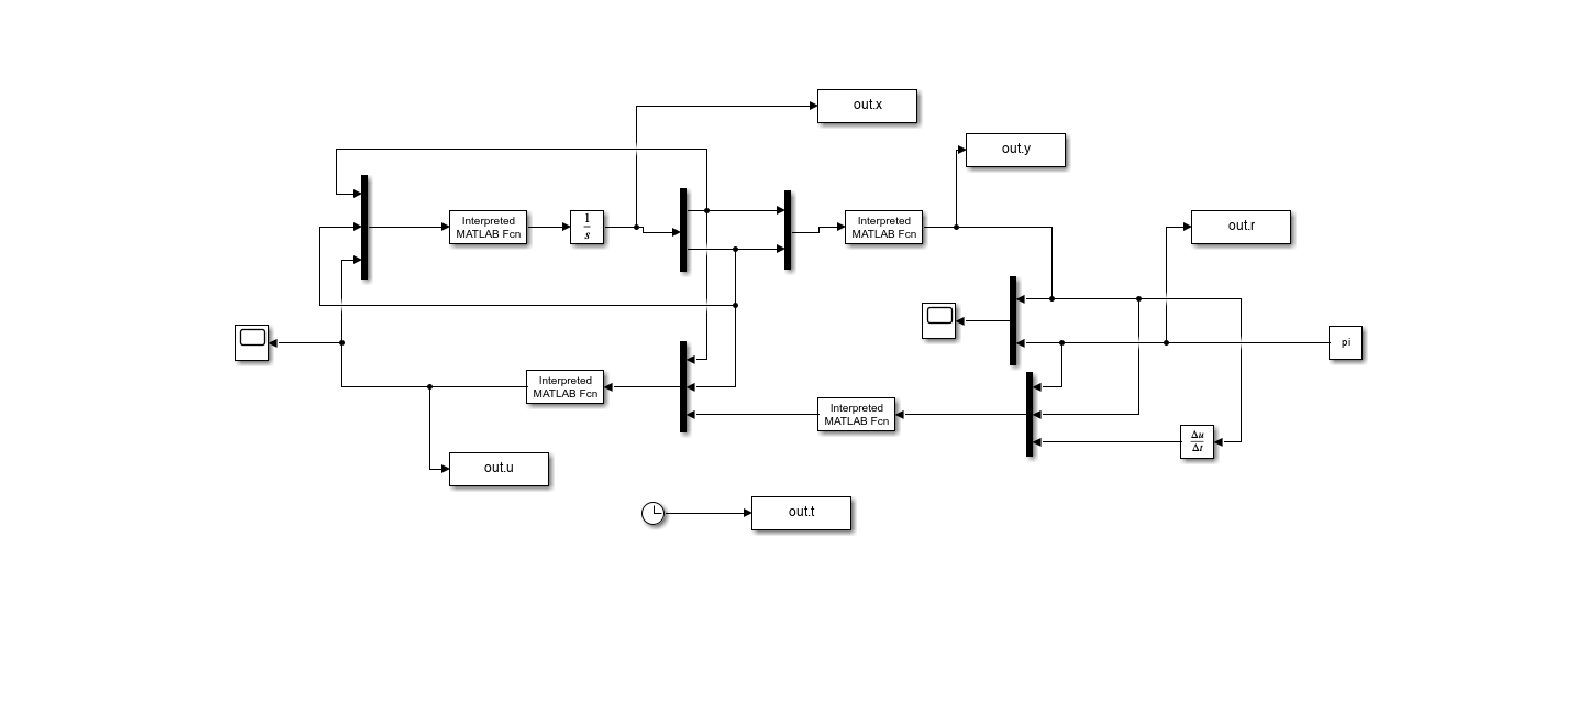

imshow(imread("img/feedback_ti_scheme.png"))

Per tarare i parametri di $\alpha$ e $\beta$ è stata usata la tecnica dell'equipollenza dei polinomi, cercando di garantire delle performance adeguate, in particolare dalla comparazione con il polinomio caratteristico si ottiene che:

$\alpha = 2 \zeta \omega _n$ e $\beta= \omega _n ^2$ 

$\zeta=0.9$ e $\omega_n=10.24$ 

per garantire determinate prestazioni sempre nei limiti dello sforzo di controllo. Da ciò si ottiene:

$\alpha=18.432$ e $\beta = 104.86$

Dopo di chè si procede alla relativa simulazione:

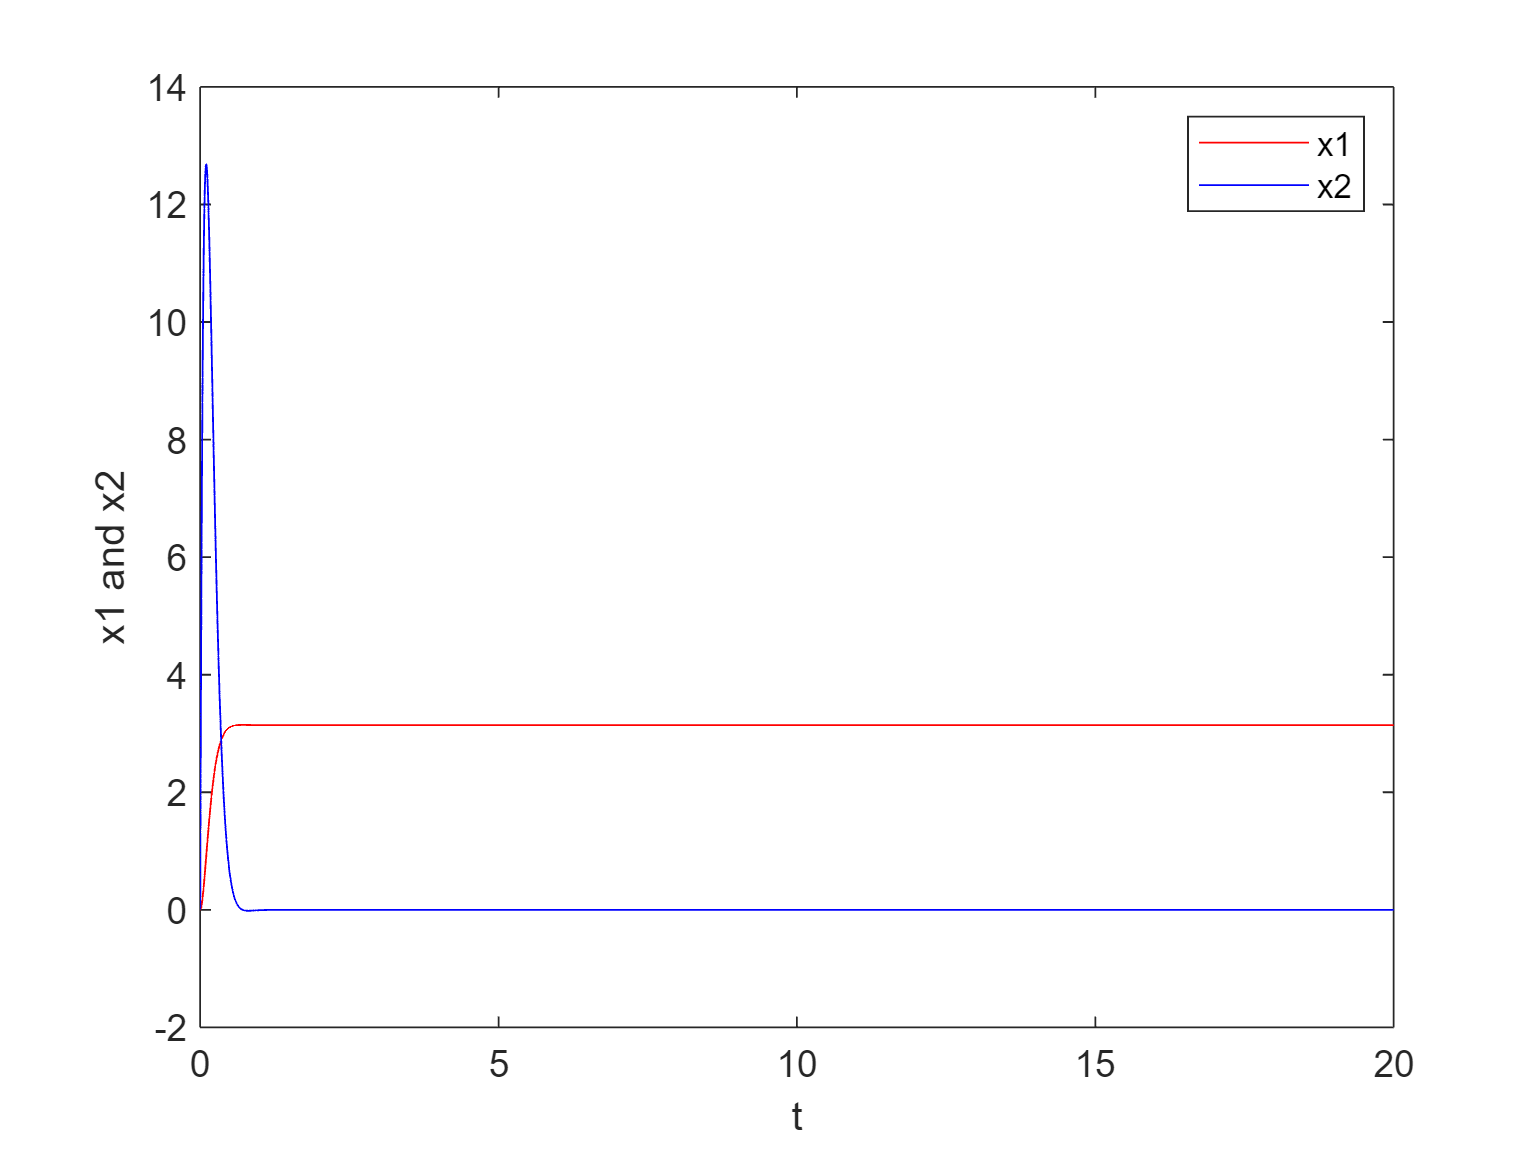

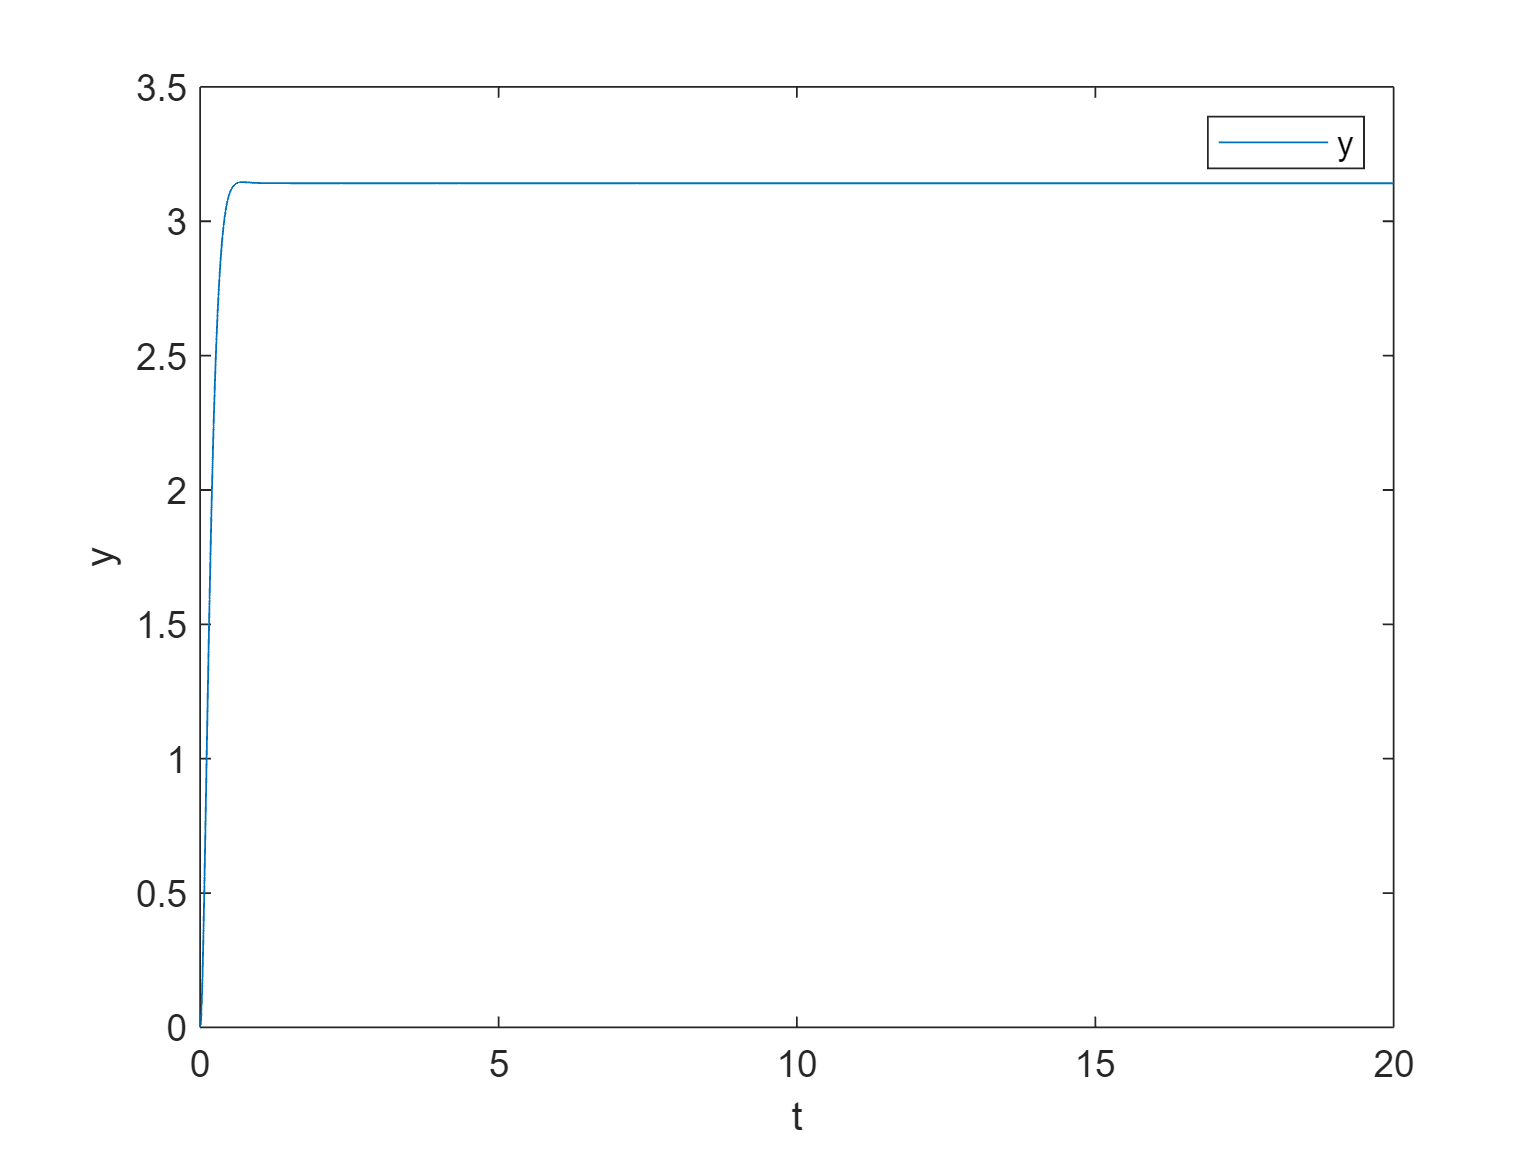

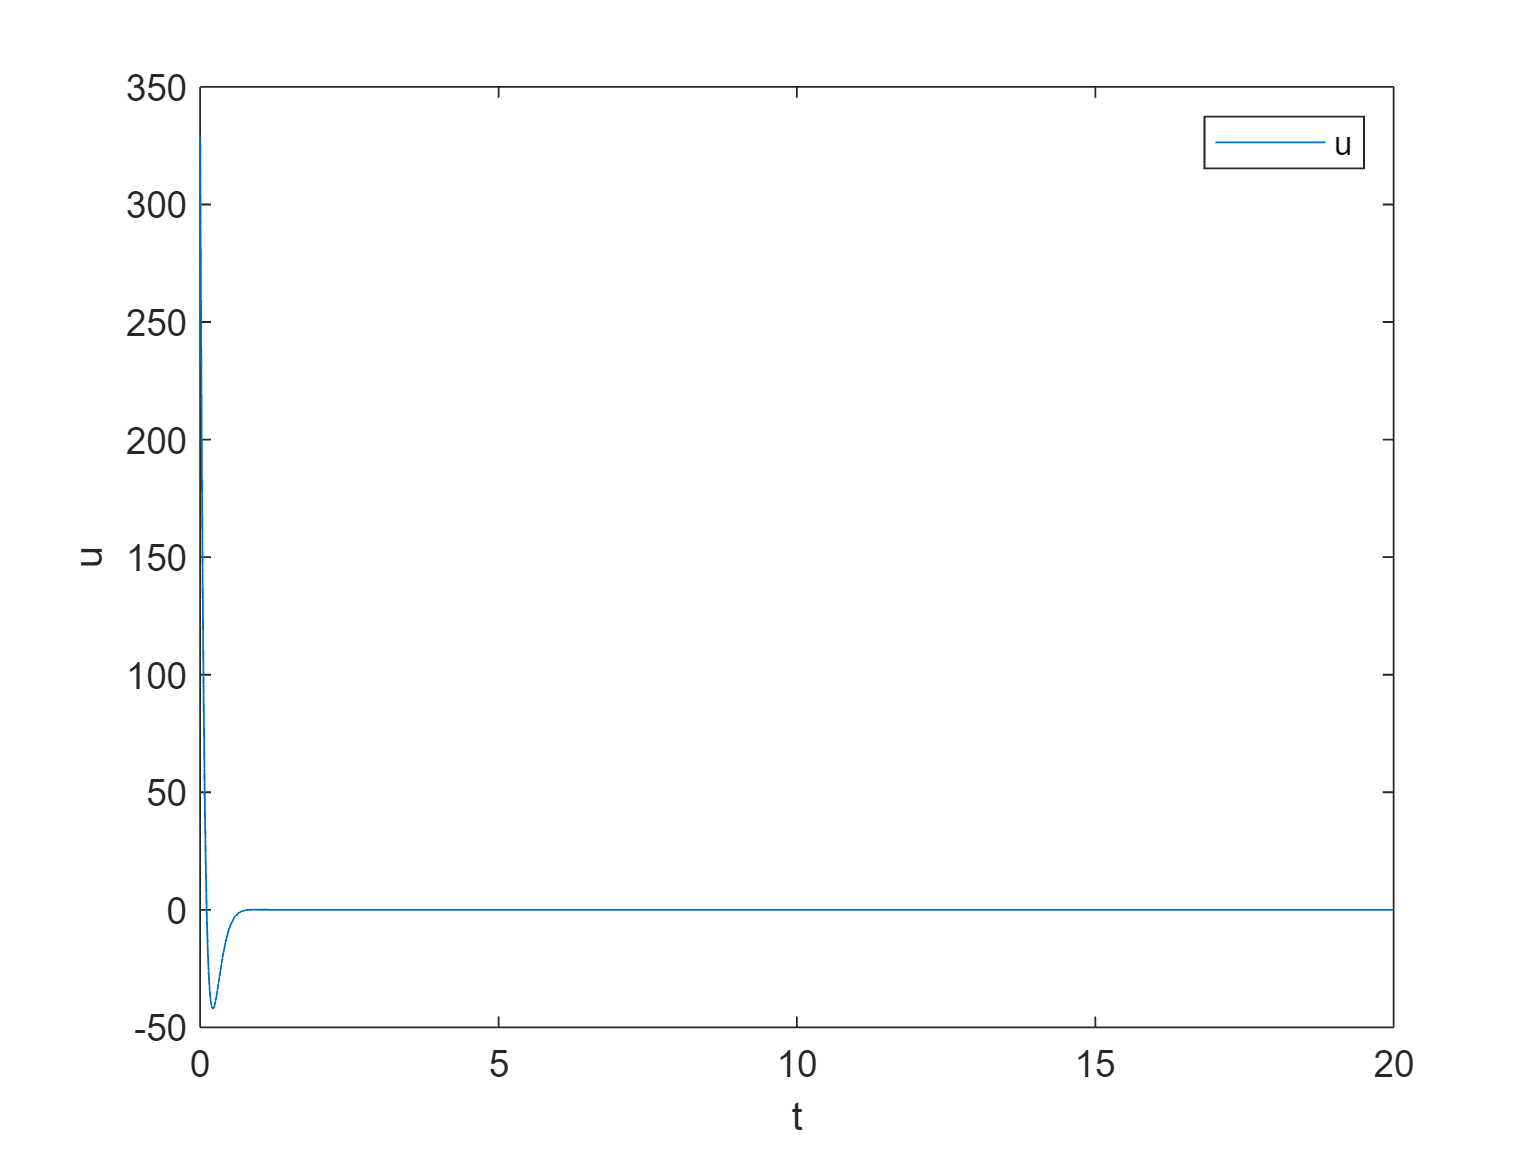

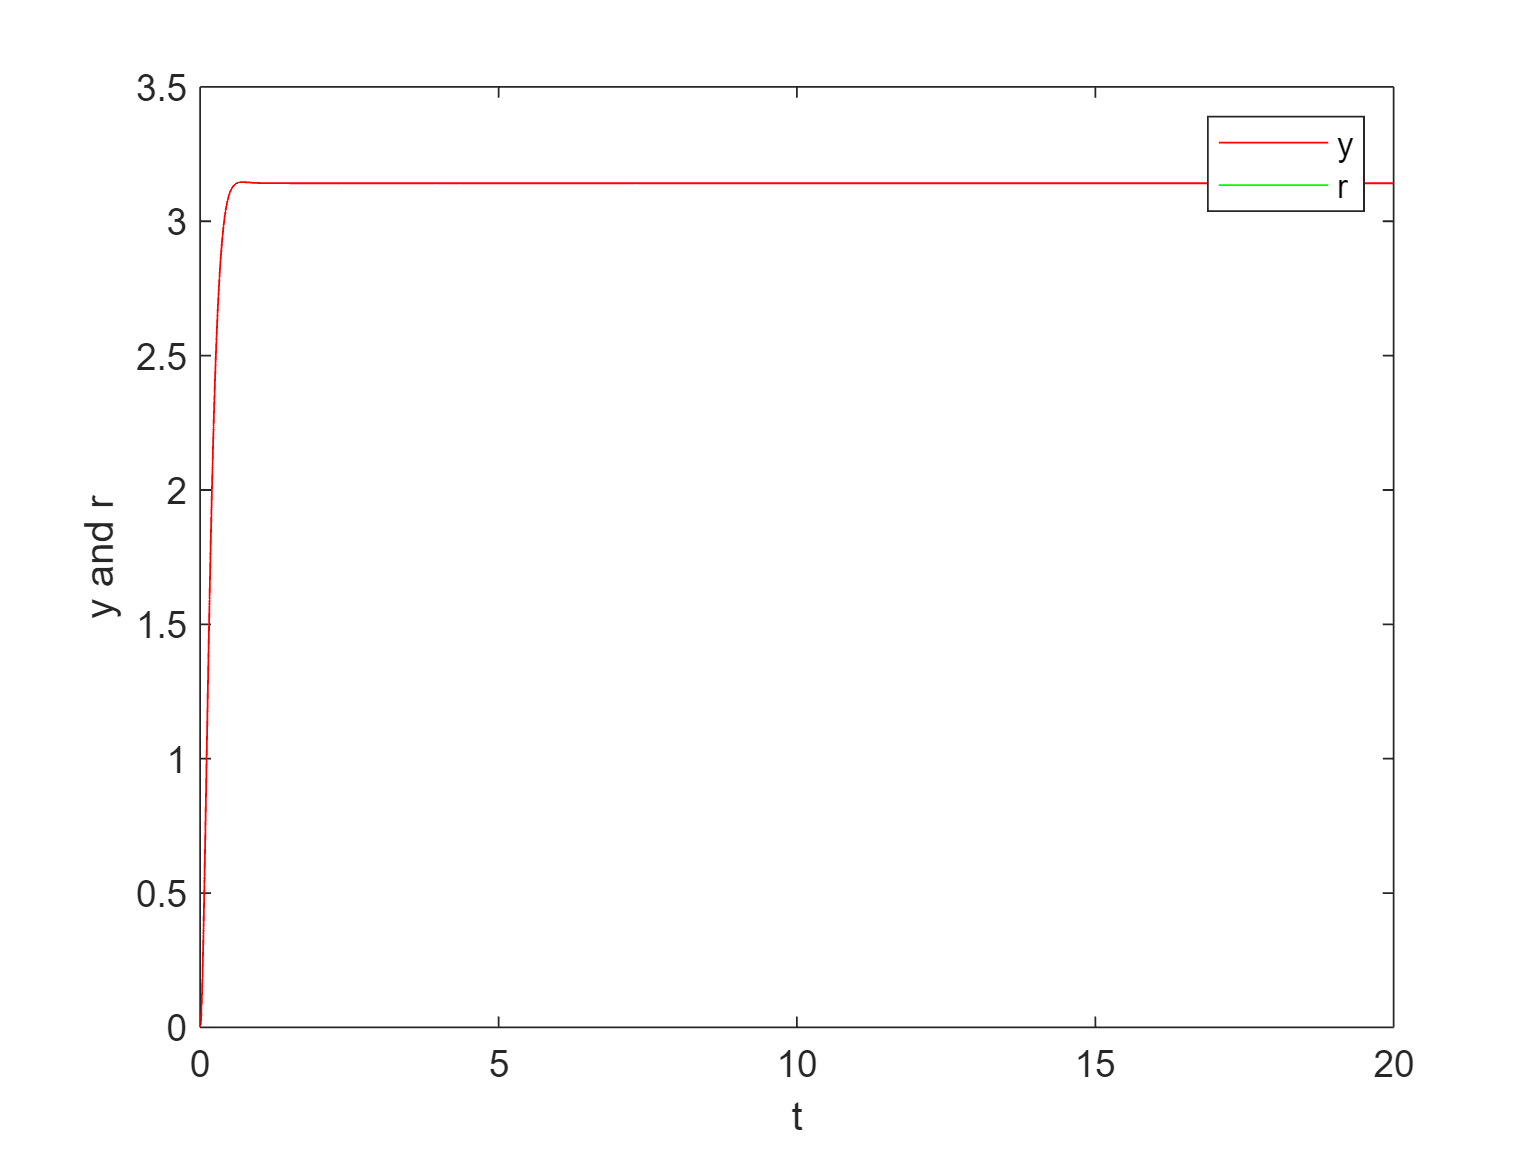

Step Information for the Output:
         RiseTime: 0.2819
    TransientTime: 0.4605
     SettlingTime: 0.4605
      SettlingMin: 2.8300
      SettlingMax: 3.1456
        Overshoot: 0.1277
       Undershoot: 0
             Peak: 3.1456
         PeakTime: 0.7124



simout=sim("FL_s_inv.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,1)

Si ottengono delle prestazioni equiparabili ai controllori lineari con un tempo di salita e di settling accettabili, così come una sovraelongazione nulla.

## **Segnale tempo variante**

La forza della feedback linearization risiede nel fatto che la scelta di $v(t)$ garantisce asintotica stabilità sulla dinamica di errore nell'uscita per ogni tipo di segnale, anche tempo variante.

Siamo sempre nella forma$\ddot y = v(t)$, e possiamo imporre che $\tilde y = y-y_d$, inoltre, dato che il segnale è tempo variante, $\$$\dot {\tilde y} = (\dot y -\dot y_d)$ e $\ddot {\tilde y} = (\ddot y -\ddot y_d)$, quindi l'ingresso di controllo equivalente può essere posto pari a: $v(t)=\ddot y_d- \alpha( \dot y-\dot y_d) - \beta (y - y_d)$ così da ottenere un sistema del tipo:


$$\ddot y= \ddot y_d- \alpha( \dot y-\dot y_d) - \beta (y - y_d)$$
 

il che modifica solamente la struttura del controllore.

Espresso in $\tilde y$ come: $\ddot {\tilde y} + \alpha \dot {\tilde y} + \beta \tilde y= 0$ esso descrive la dinamica dell'errore nell'uscita. A questo punto passando al polinomio caratteristico si ottiene:

$s^2 + \alpha s + \beta = 0$ e per avere asintotica stabilità i coefficienti del polinomio devono essere concordi e non nulli, siccome il primo coefficiente è fissato ed è positivo, dobbiamo avere $\alpha >0$ e $\beta > 0$ per avere $y(t)->y_d(t)$.

Lo schema simulink relativo è:

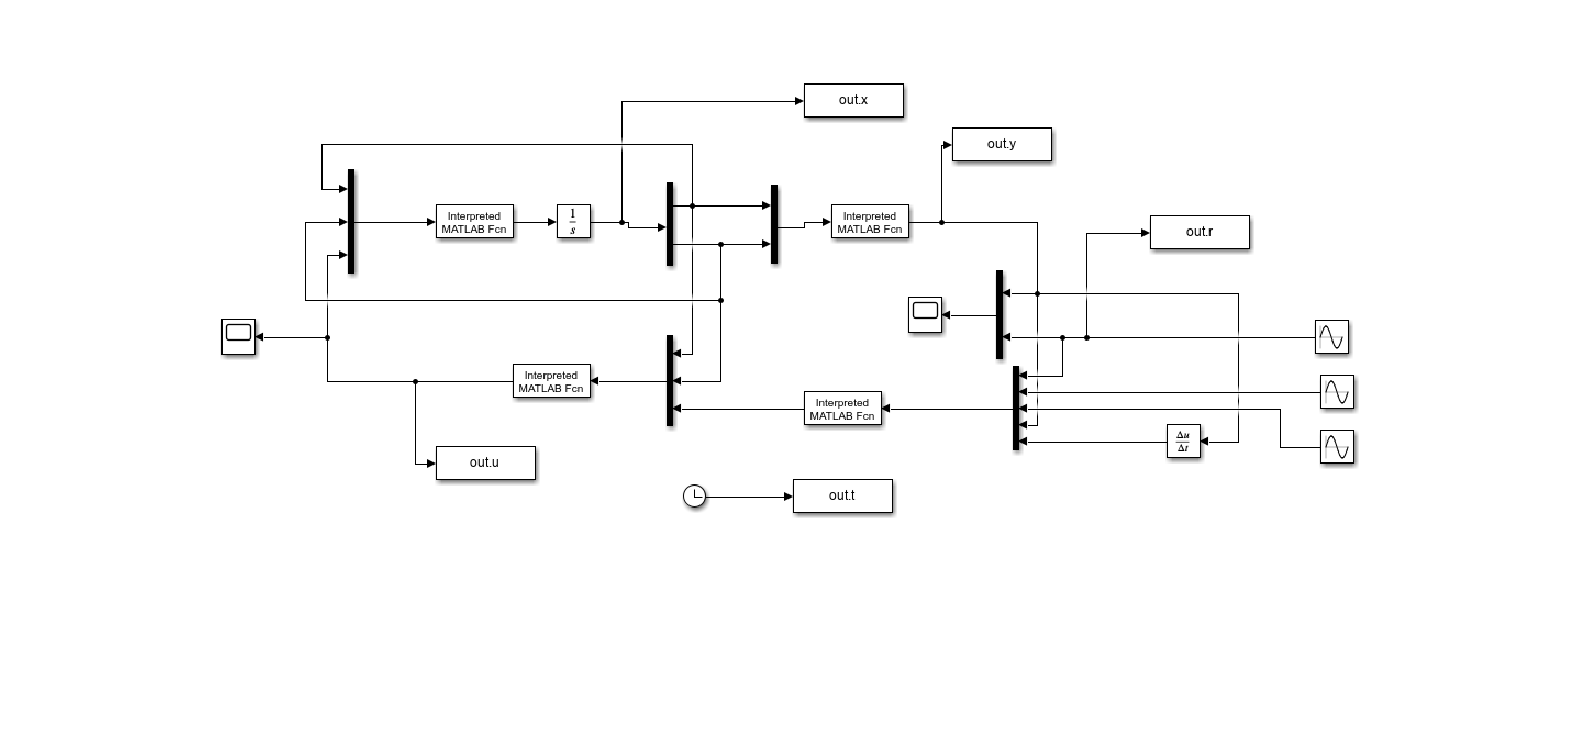

imshow(imread("img/feedback_tv_scheme.png"))

I parametri $\alpha$ e $\beta$ utilizzati fanno riferimento al caso precedente, è stata semplicemente modificata la struttura del controllore per l'inseguimento di segnali tempo varianti come descritto in precedenza. In realtà la stessa formula enunciata nella cella precedente è utilizzabile anche per i segnali tempo invarianti, semplicemente inserendo come input delle derivate dell'uscita desiderata $0$. 

La creazione di file differenti è dovuta allo scopo di discutere il cambio della struttura del controllore. Verifichiamo come si comporta il controllore con un tipo di segnale sinusoidale.

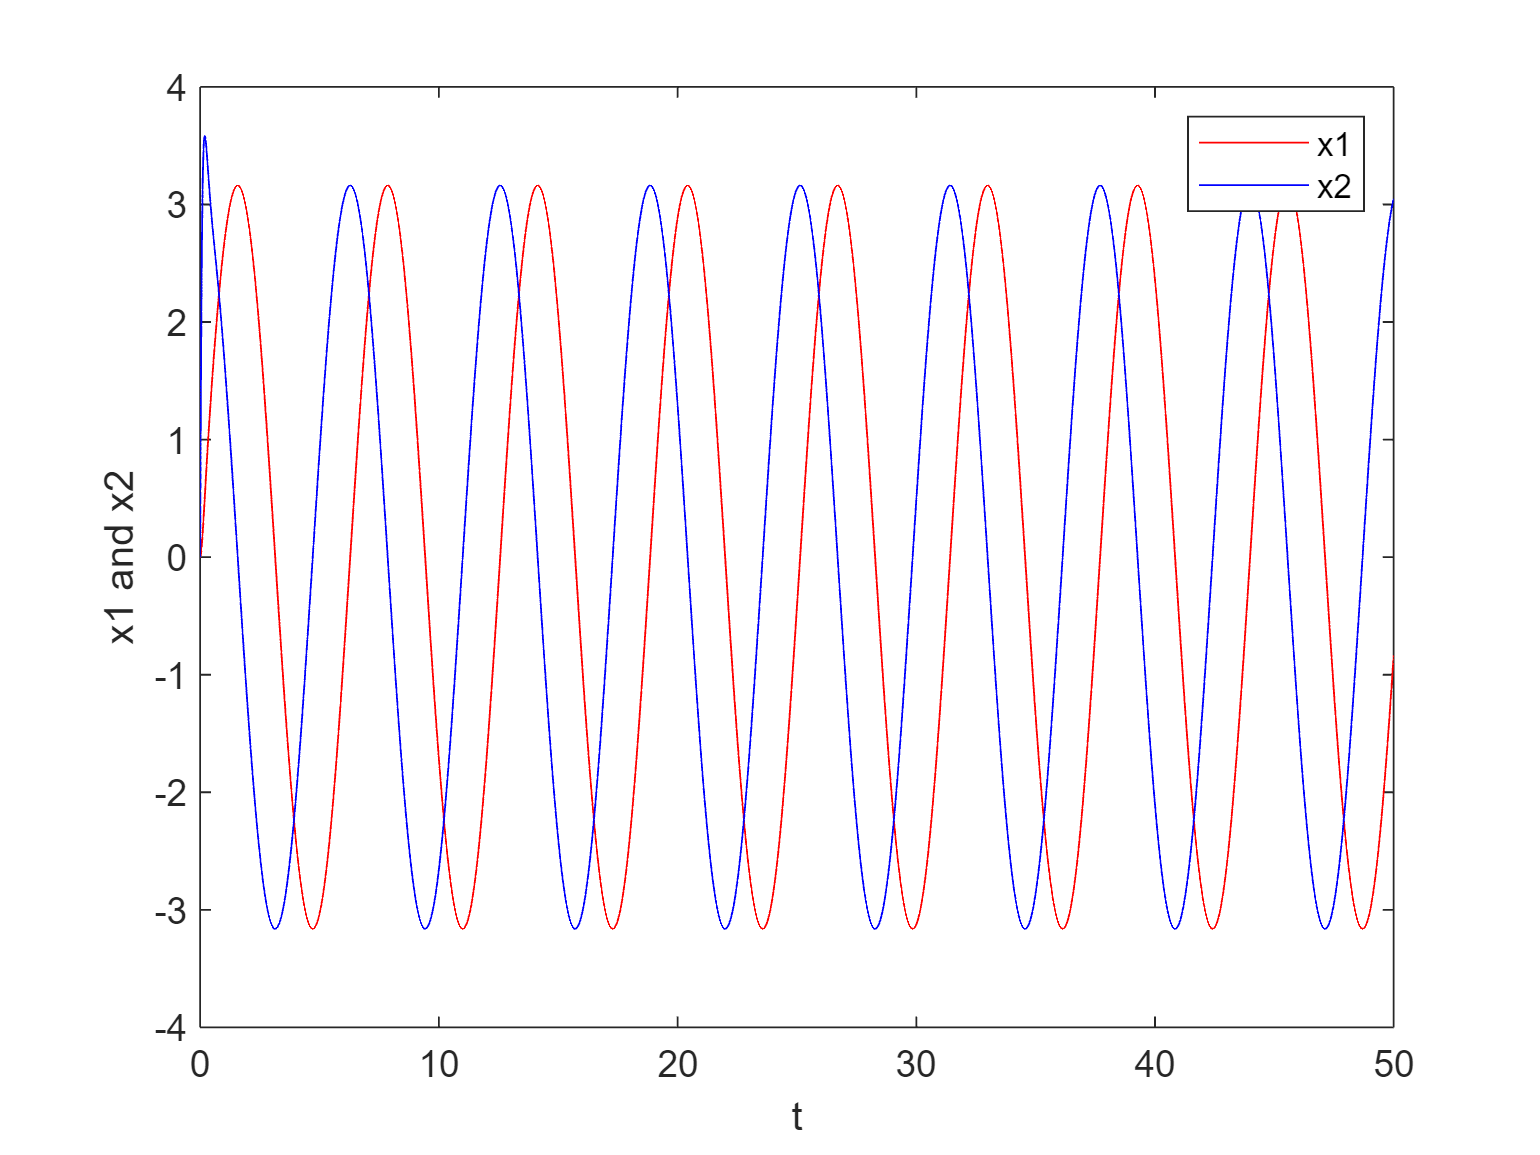

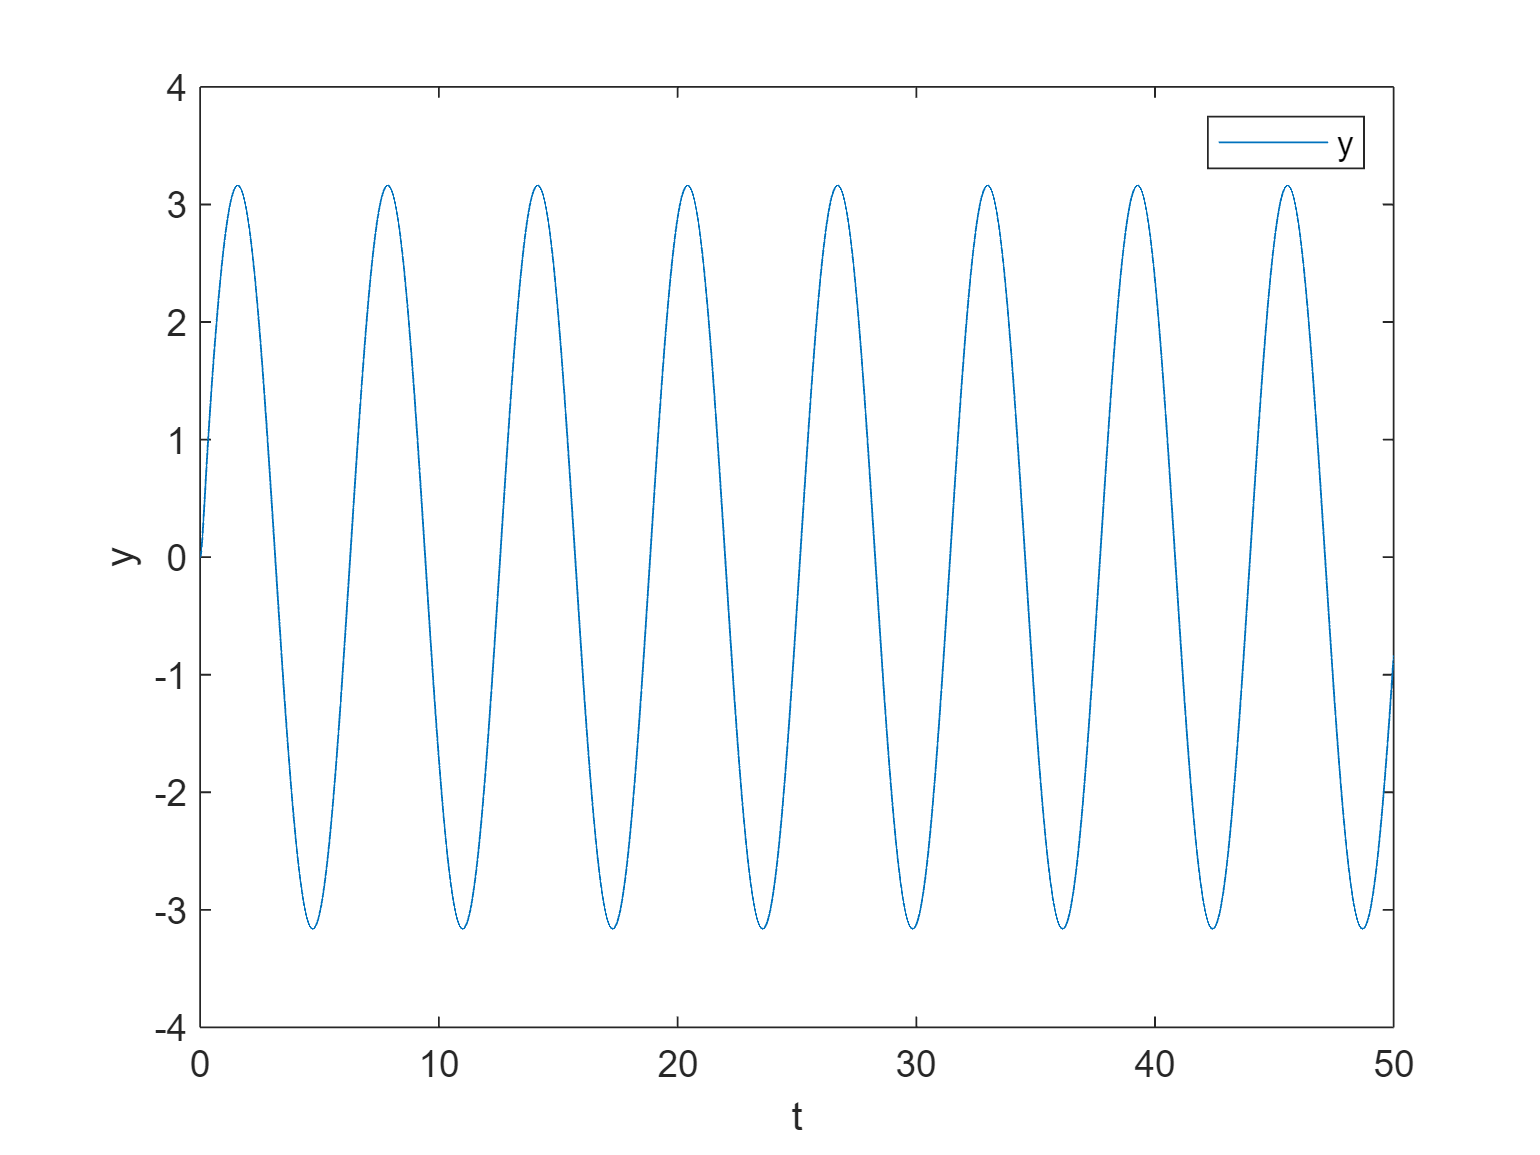

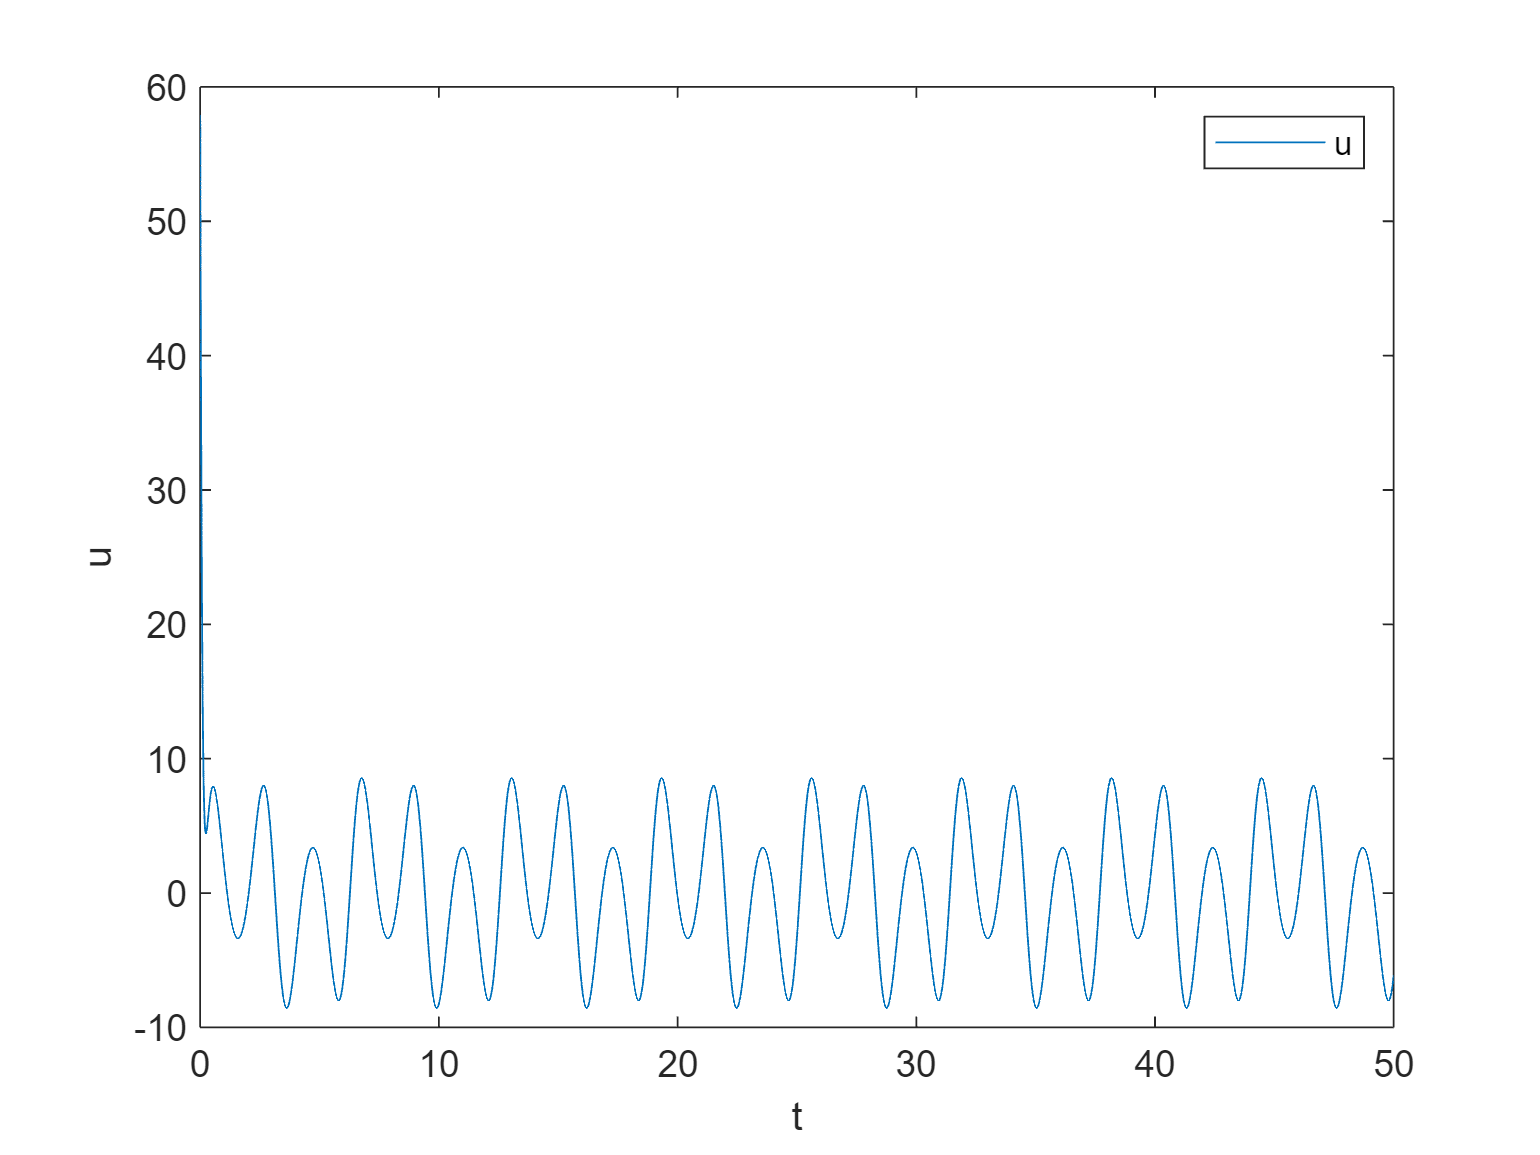

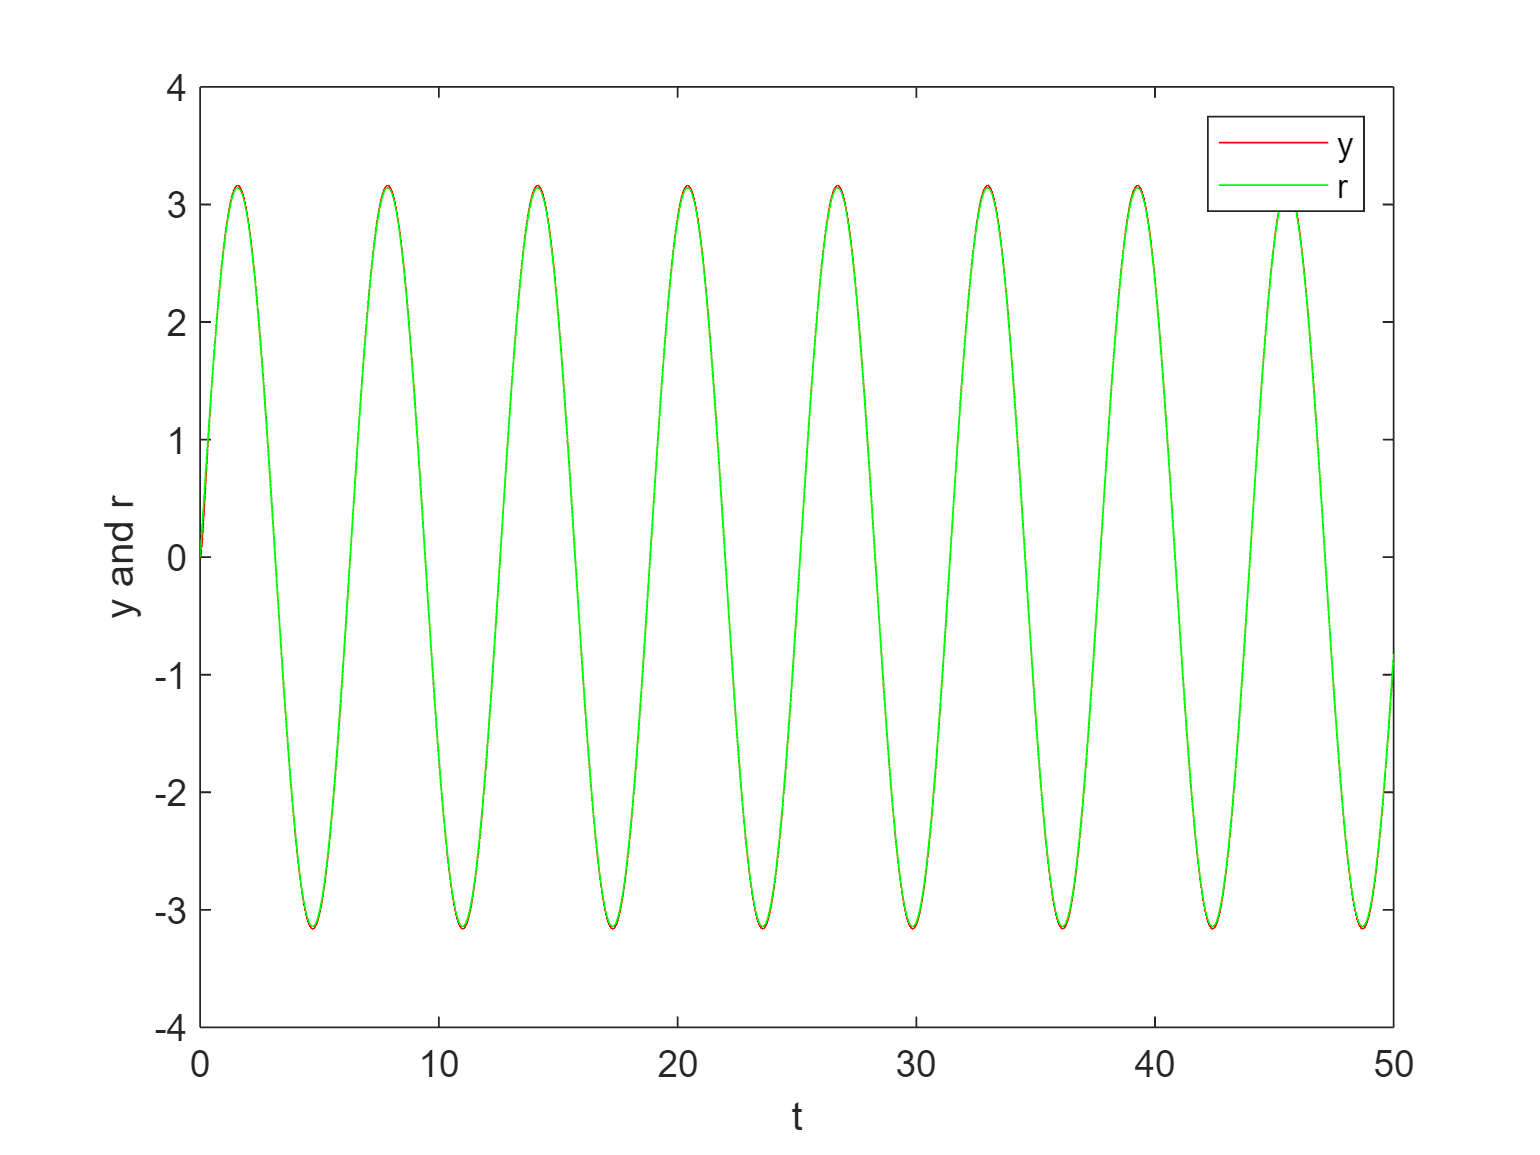

simout=sim("FL_s_v_seno.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0);

Come vediamo, nonostante lo sforzo di controllo contenuto, riusciamo correttamente ad inseguire il riferimento tempo variante. Anche altri esperimenti con altri tipi di segnali sono stati effettuati, ma è riportato uno dei segnali più sensato per il tipo di sistema, insieme alla rampa:

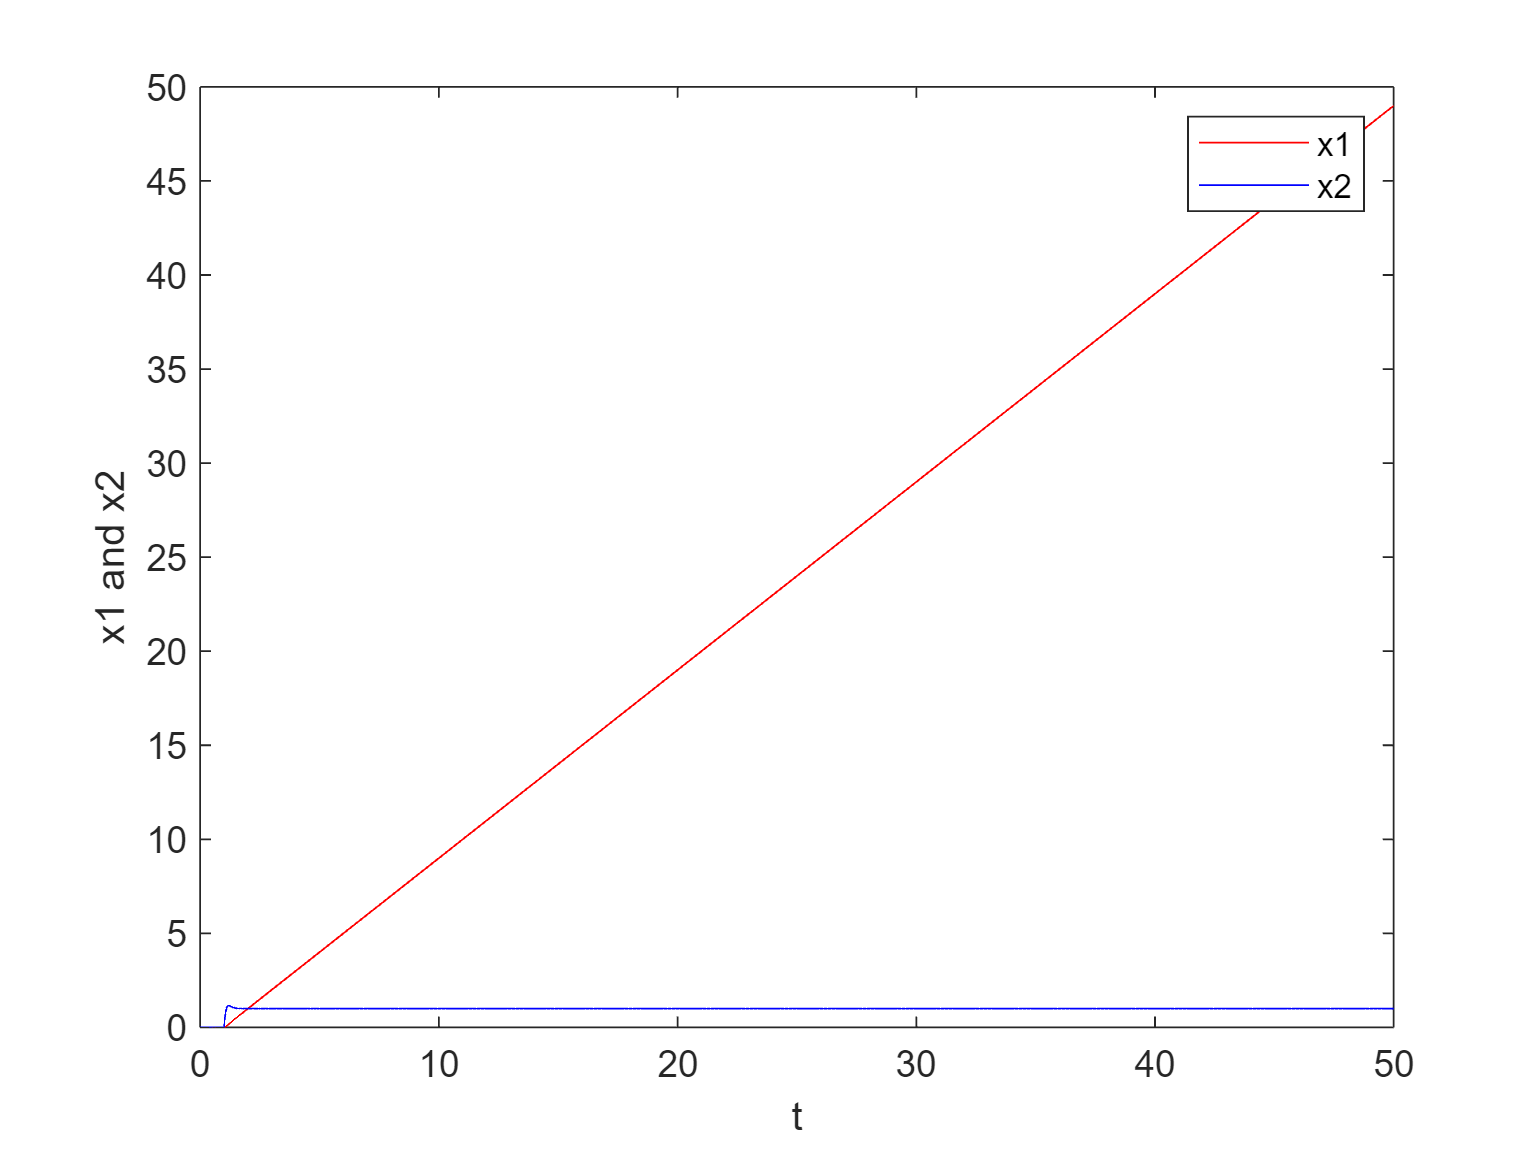

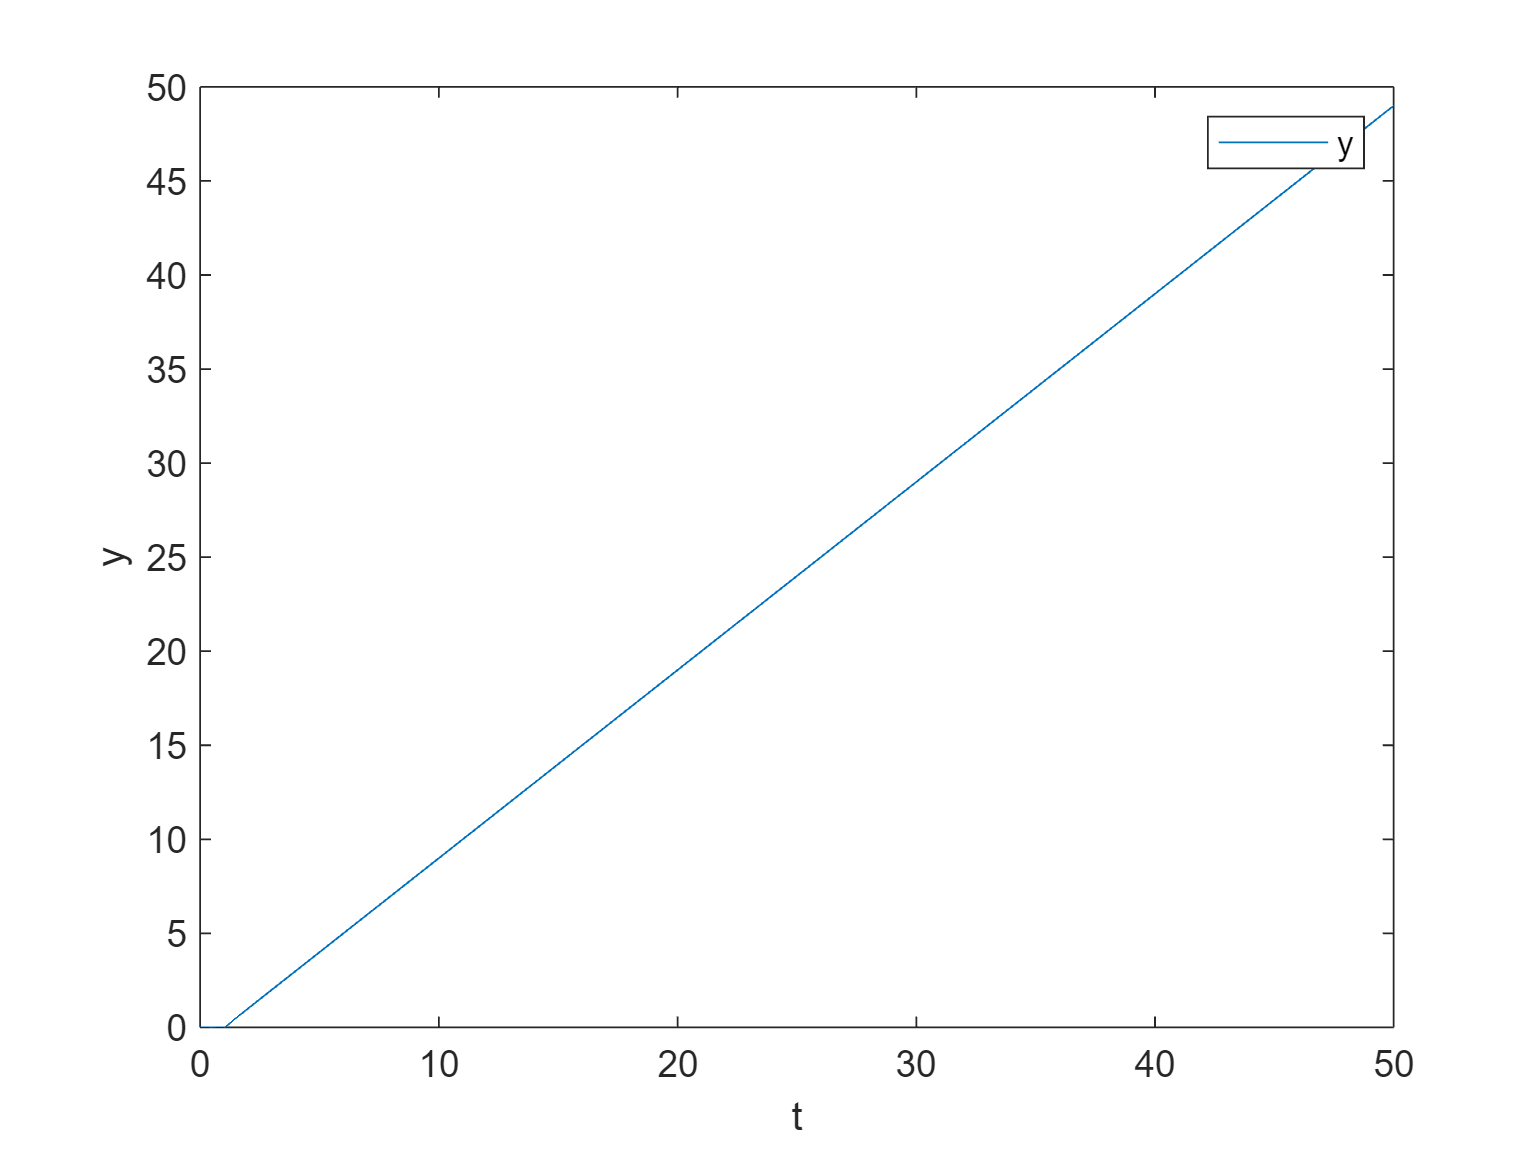

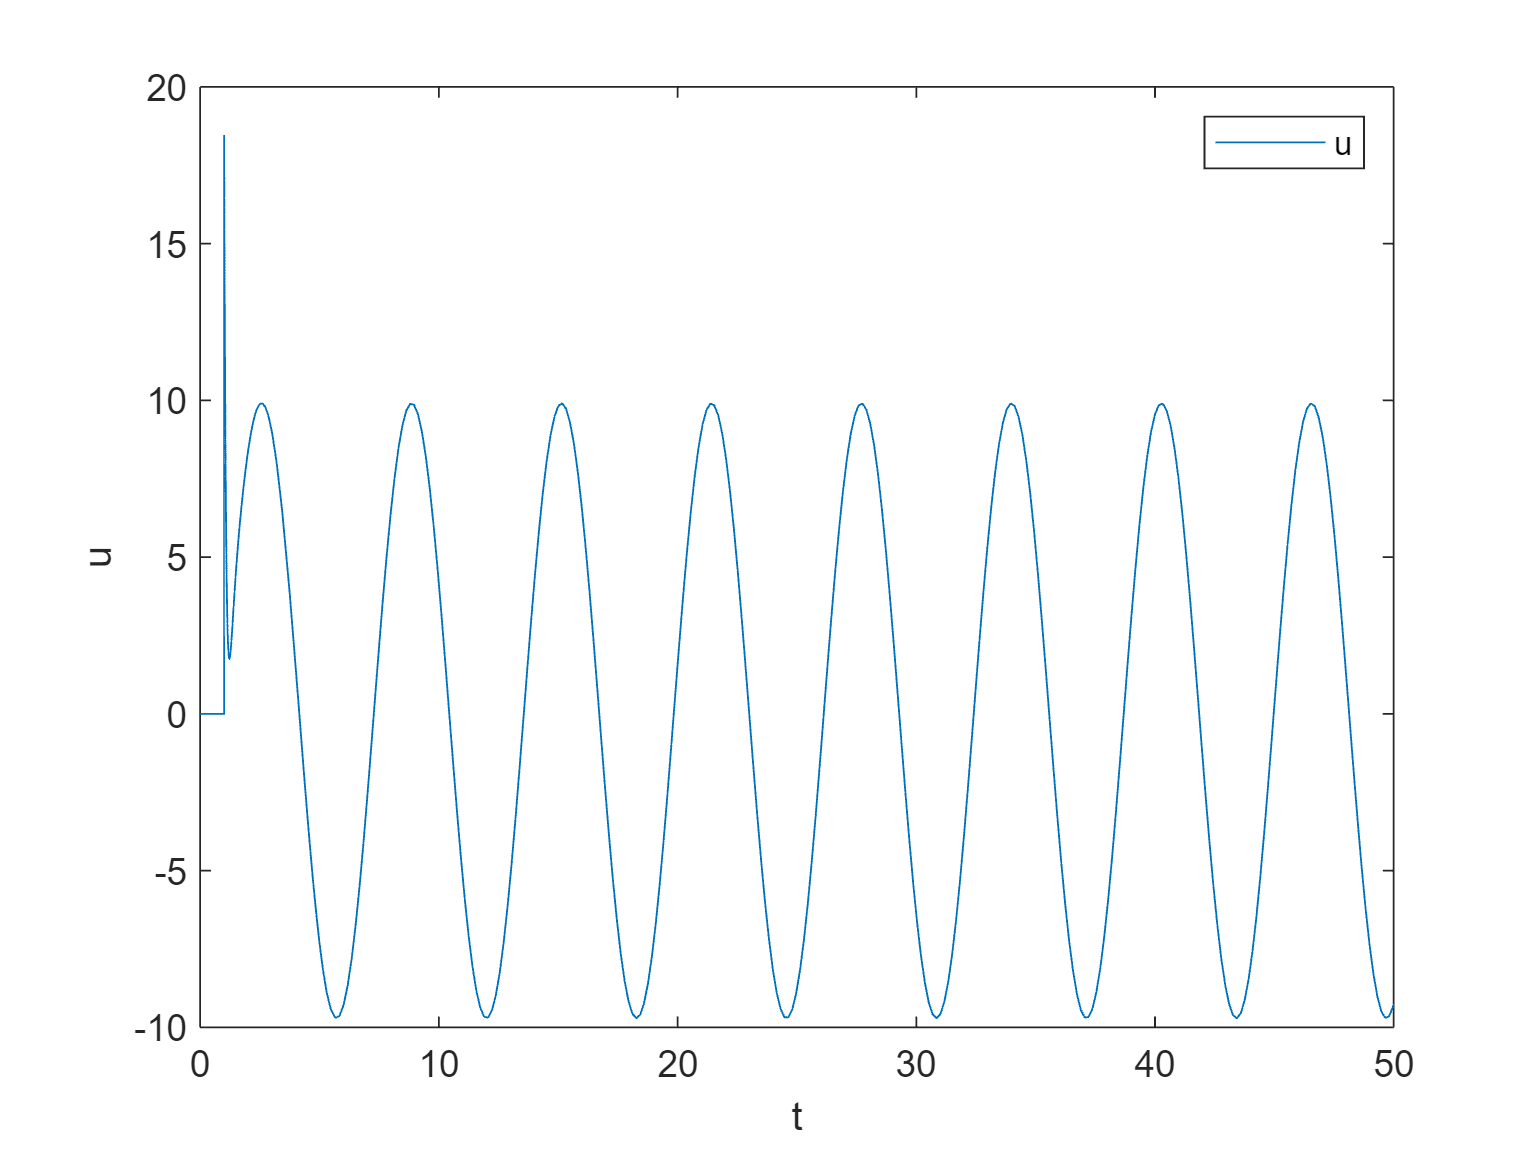

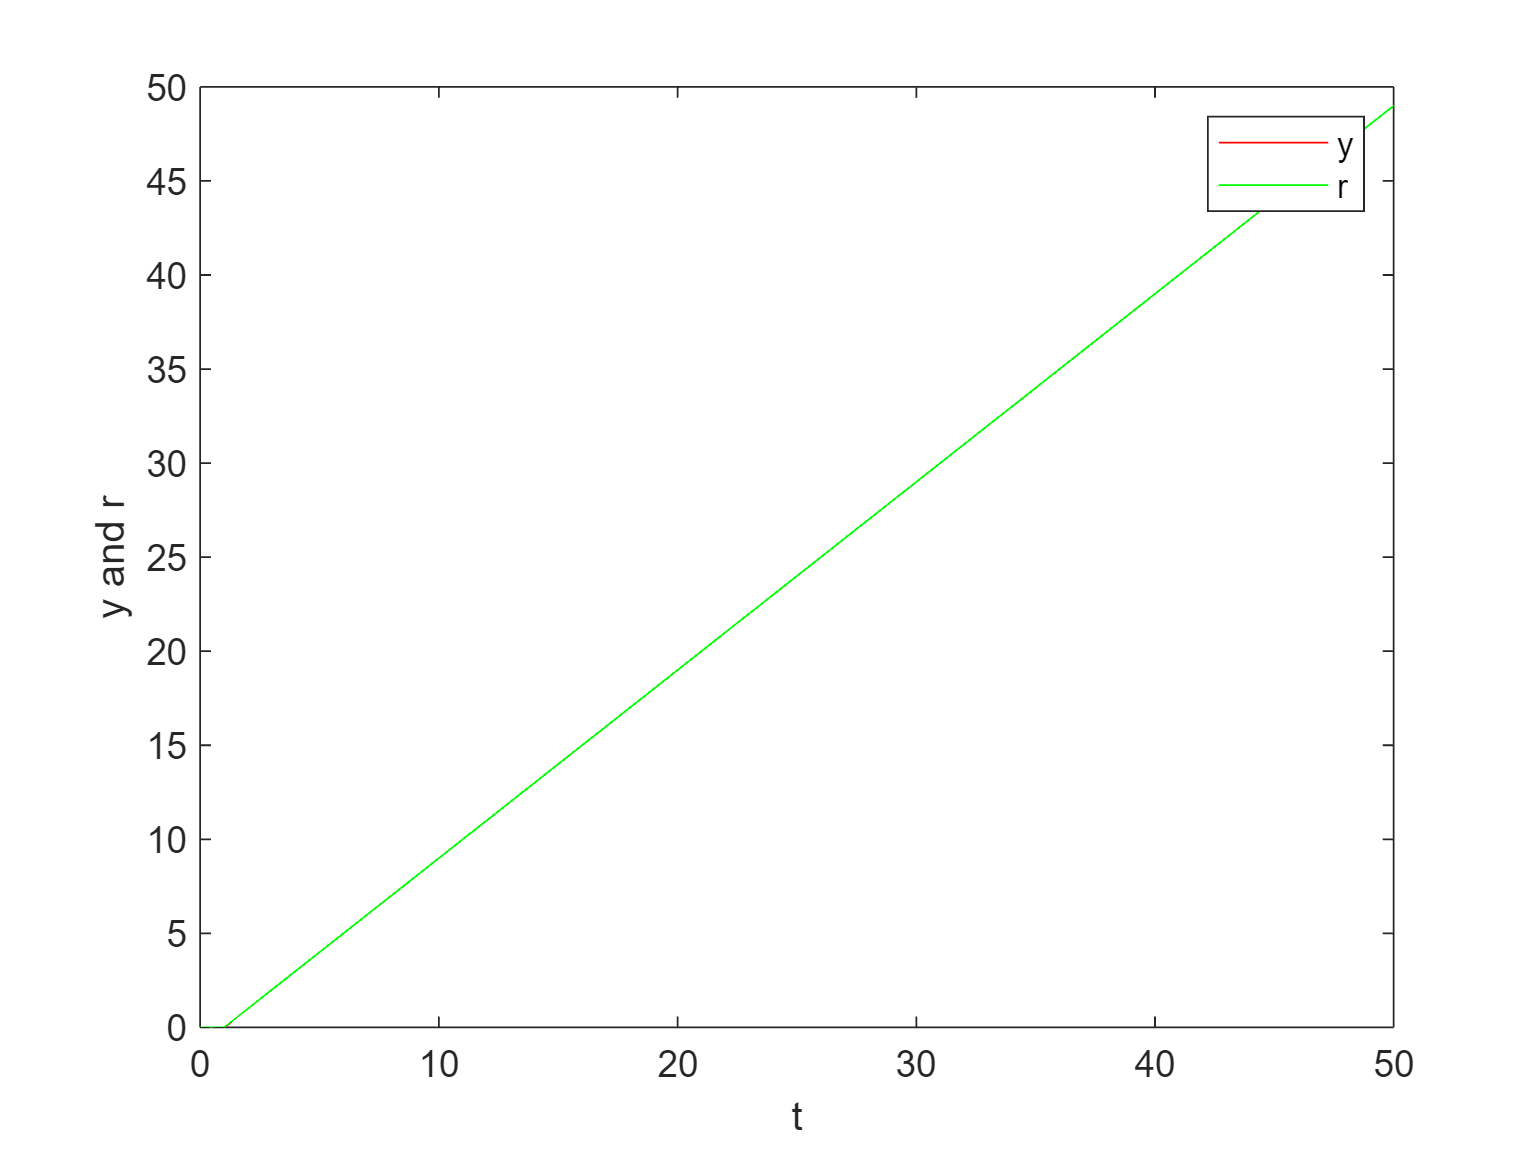

simout=sim("FL_s_v_rampa.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0)

Dal punto di vista del significato fisico dei segnali, nel caso della rampa, stiamo chiedendo al pendolo di effettuare giri completi alla stessa velocità, mentre nel caso del seno stiamo chiedendo di farlo girare per un giro completo e poi invertire il verso in maniera periodica. Entrambi questi segnali potrebbero essere un ingresso probabile per il sistema, quindi discuterli ci è sembrata la scelta più adatta nella scelta di quali segnali giudicare. 

## Segnale tempo invariante - Azione integrale

Così come quanto fatto per i controllori lineari, introduciamo una progettazione dello stesso controllore capace, però, di abbattare i disturbi. Allo schema visto per la feedback linearization per il segnale tempo invariante viene aggiunta una componente di azione integrale, ottenendo così il seguente nuovo schema:

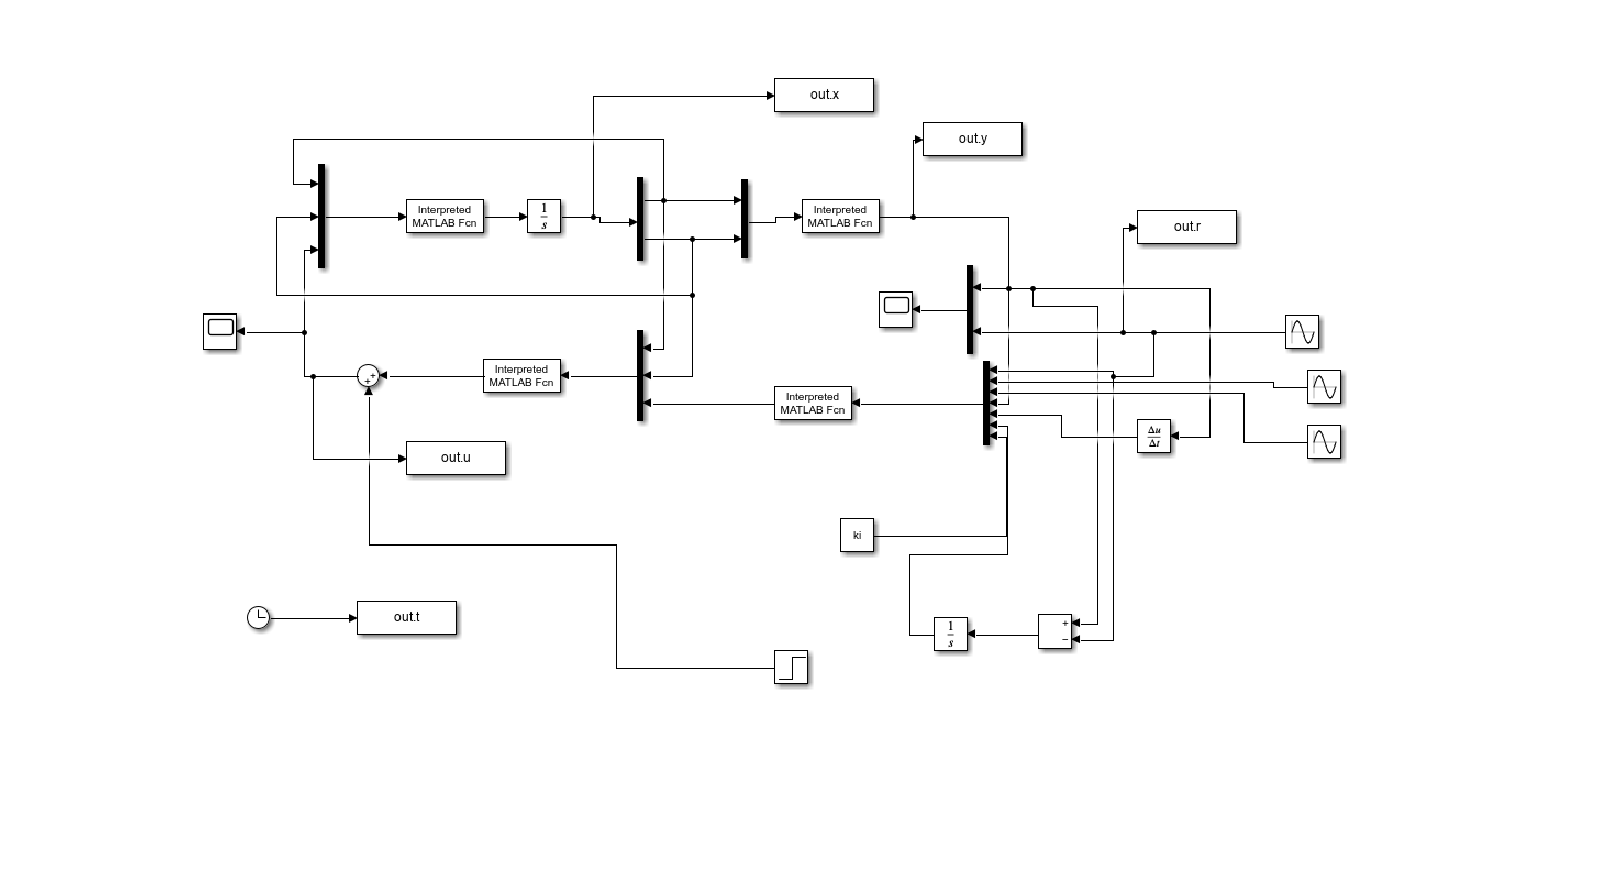

imshow(imread("img/feedback_ti_ia_scheme.png"))

E' importante sottolineare come, è stata inserita una componente di azione integrale che arricchisce l'ingresso di controllo, fornendogli una struttura del tipo $u(t)=- \alpha \dot y-\beta (y-y_d) -k_i \int (y-y_d)
$. La scelta del parametro $k_I$ è stata effettuata tramite fine tuning, a partire dalle specifiche date al sistema del secondo ordine precedentemente calcolate. 

## **Simulazione senza disturbo**

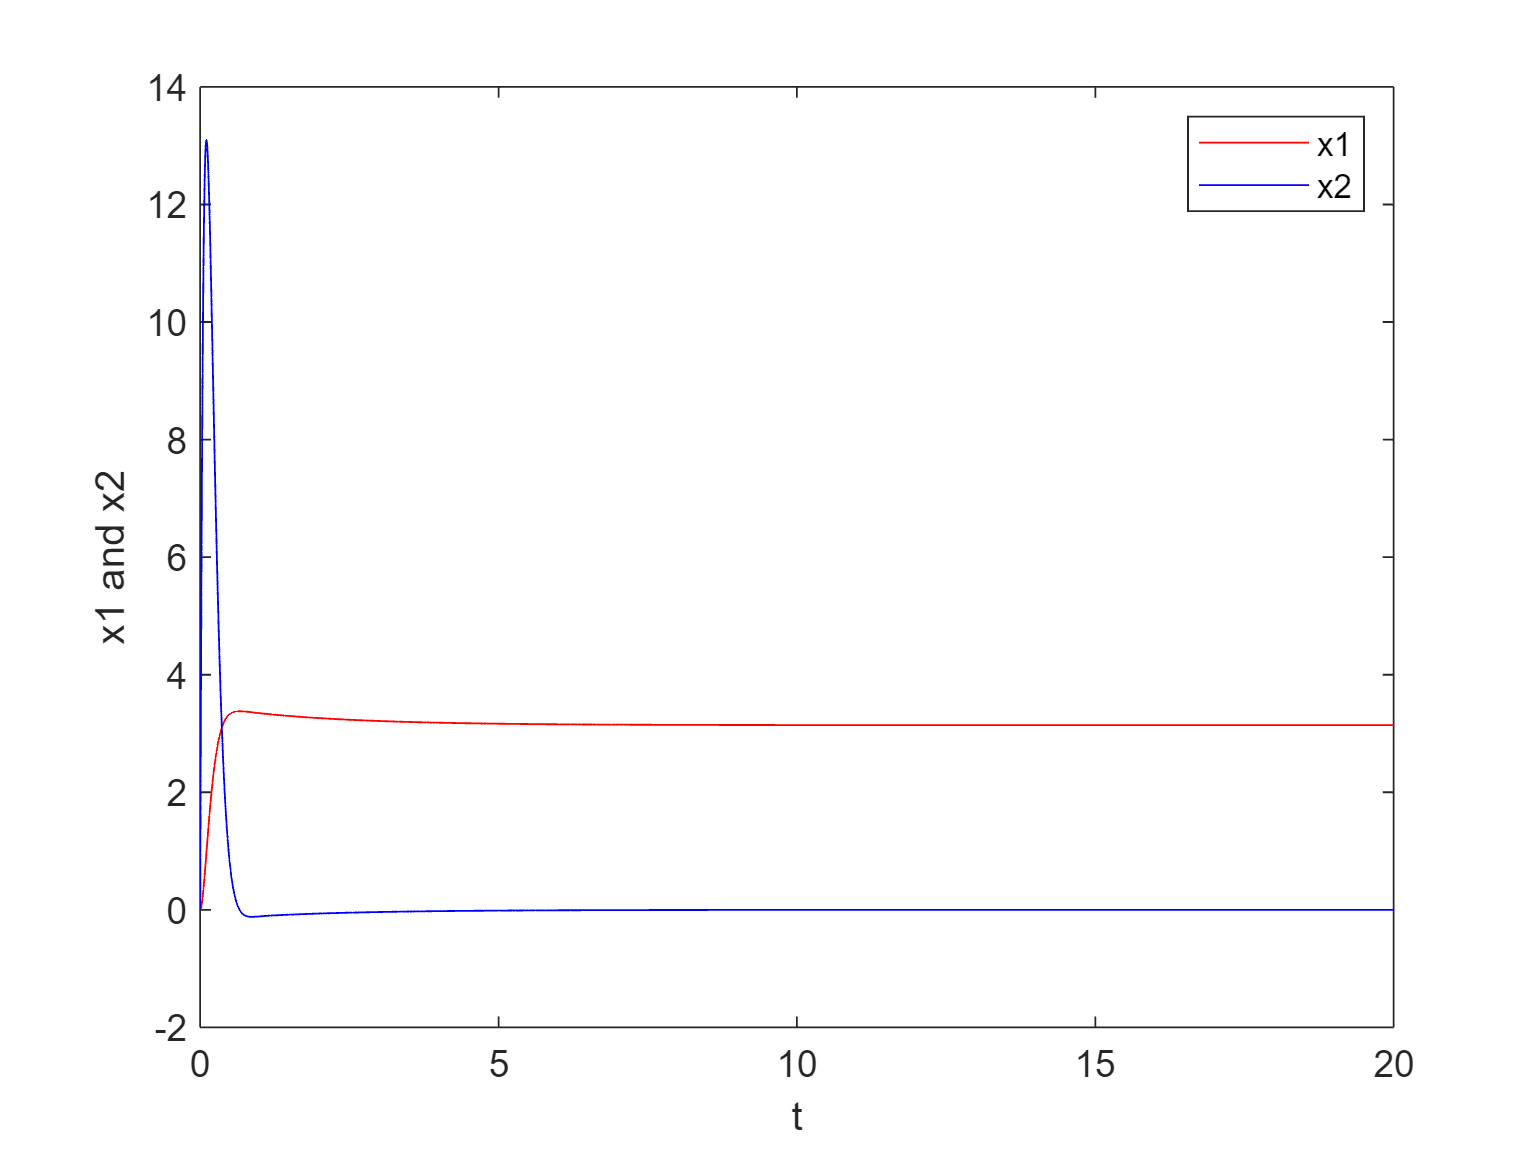

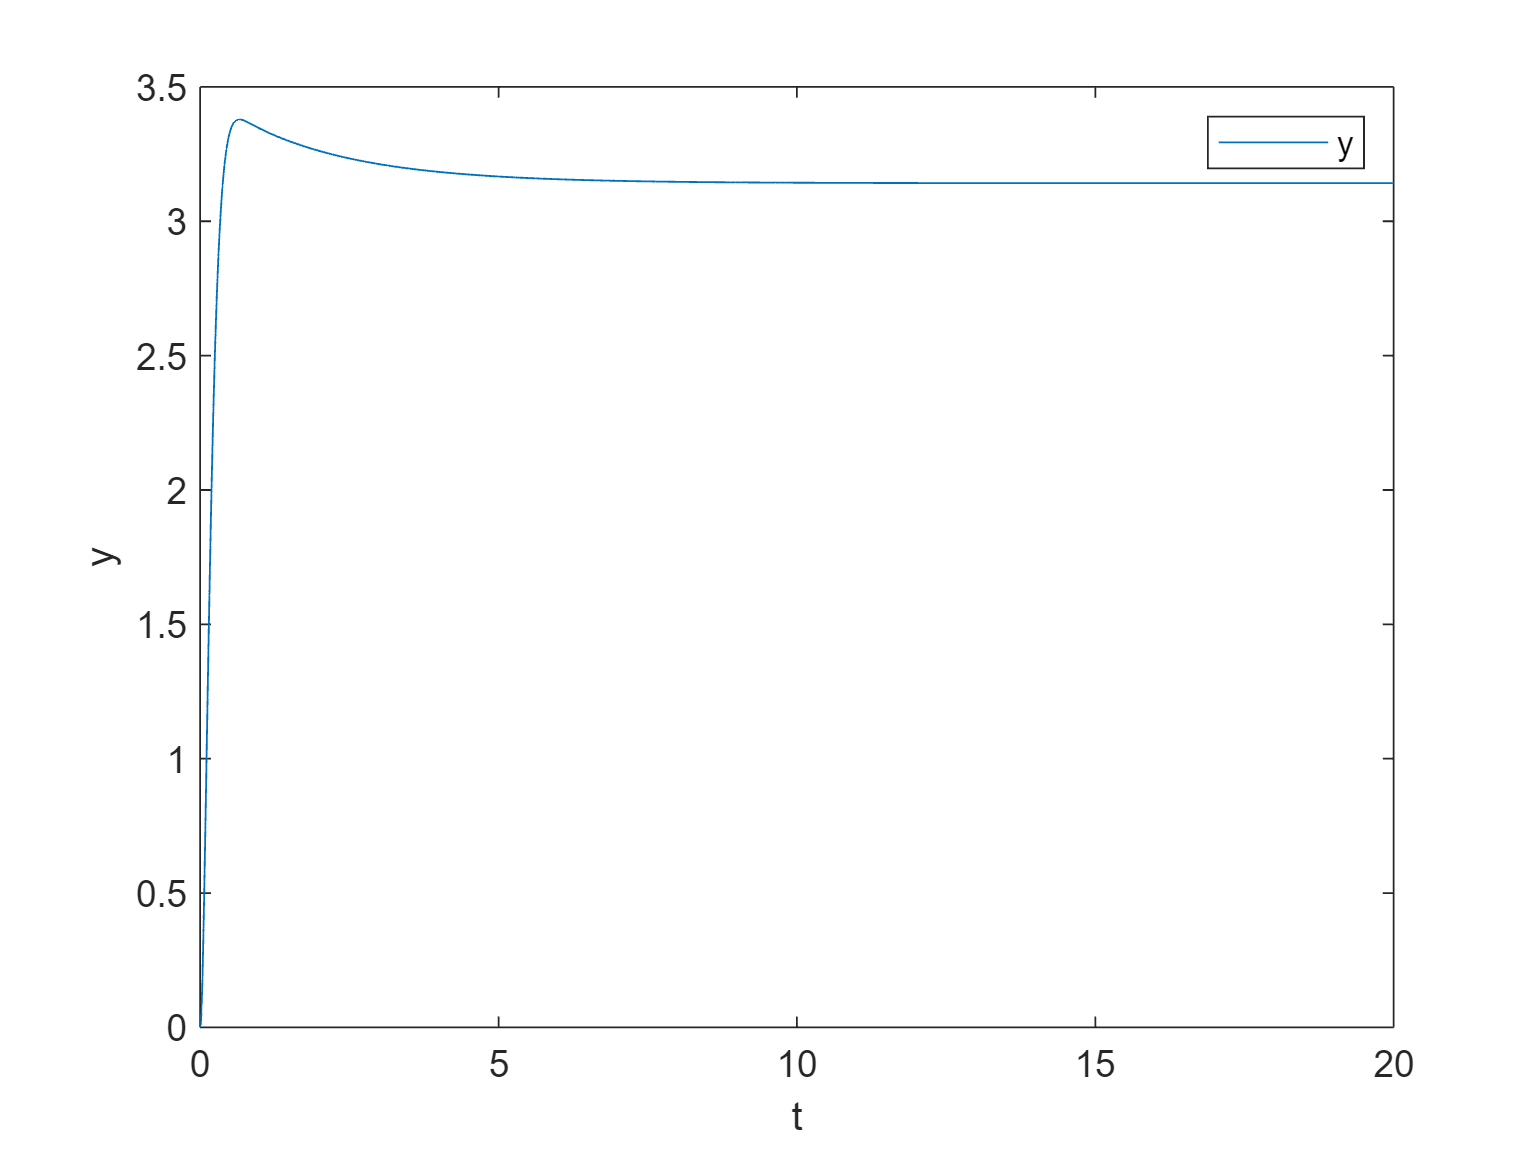

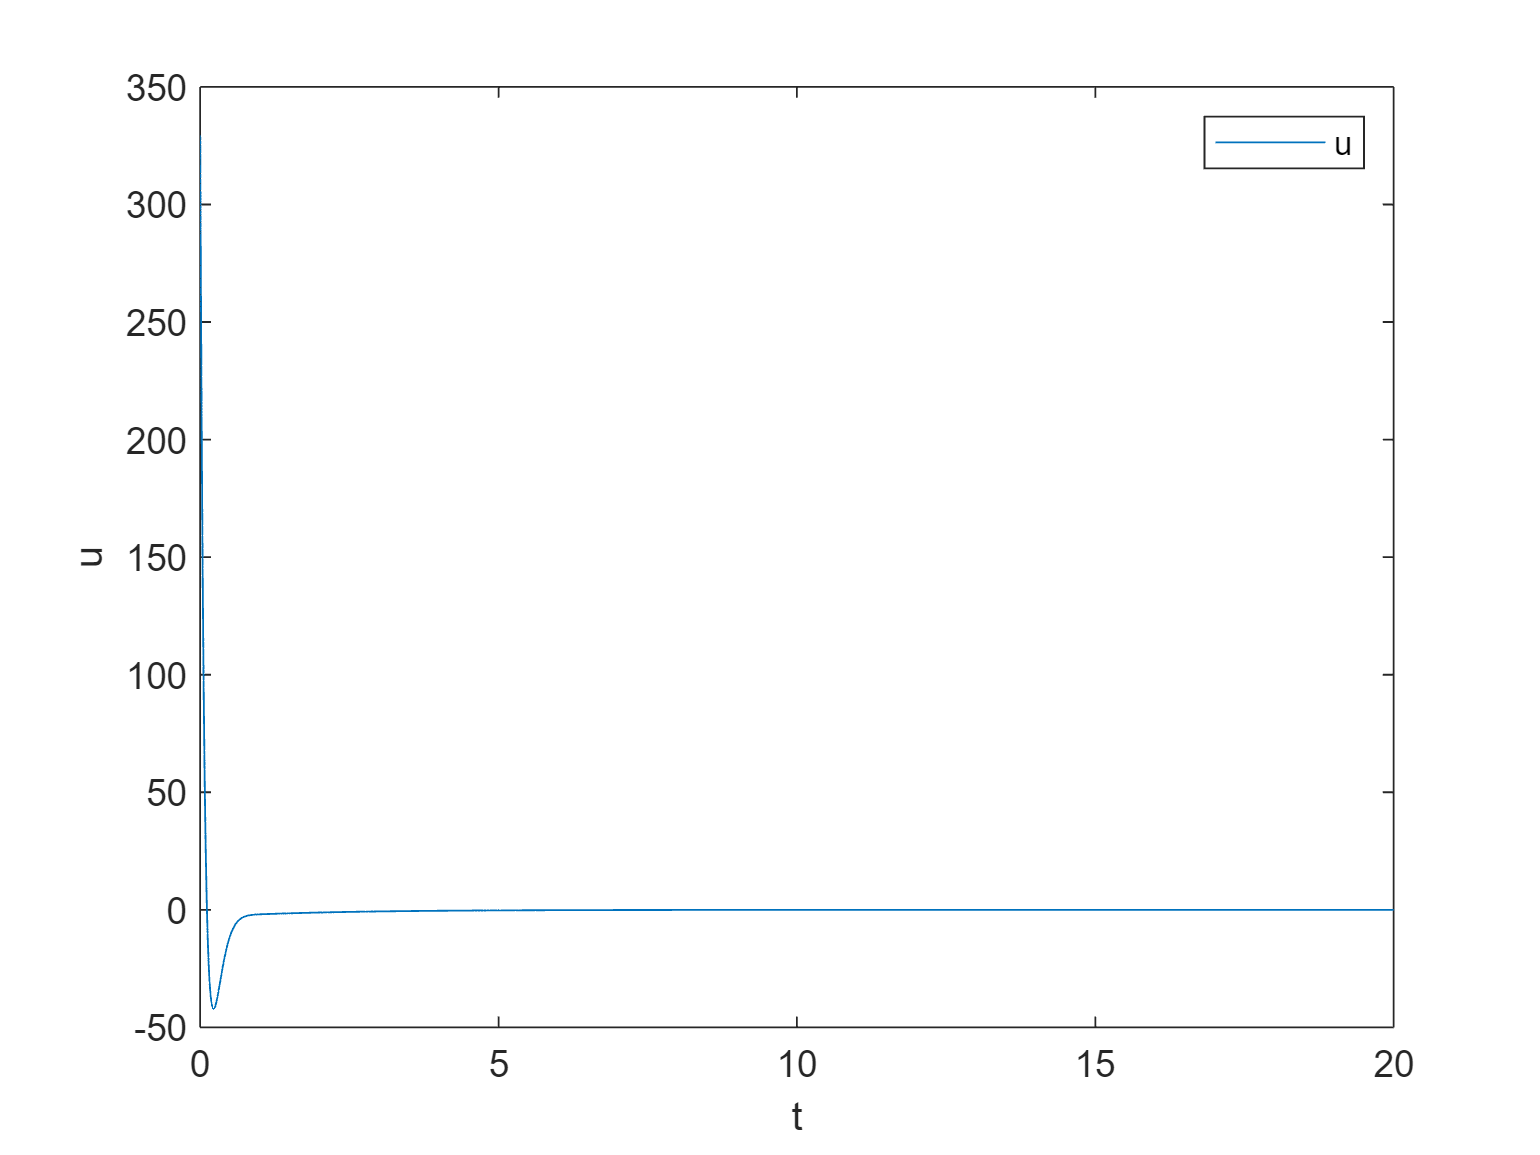

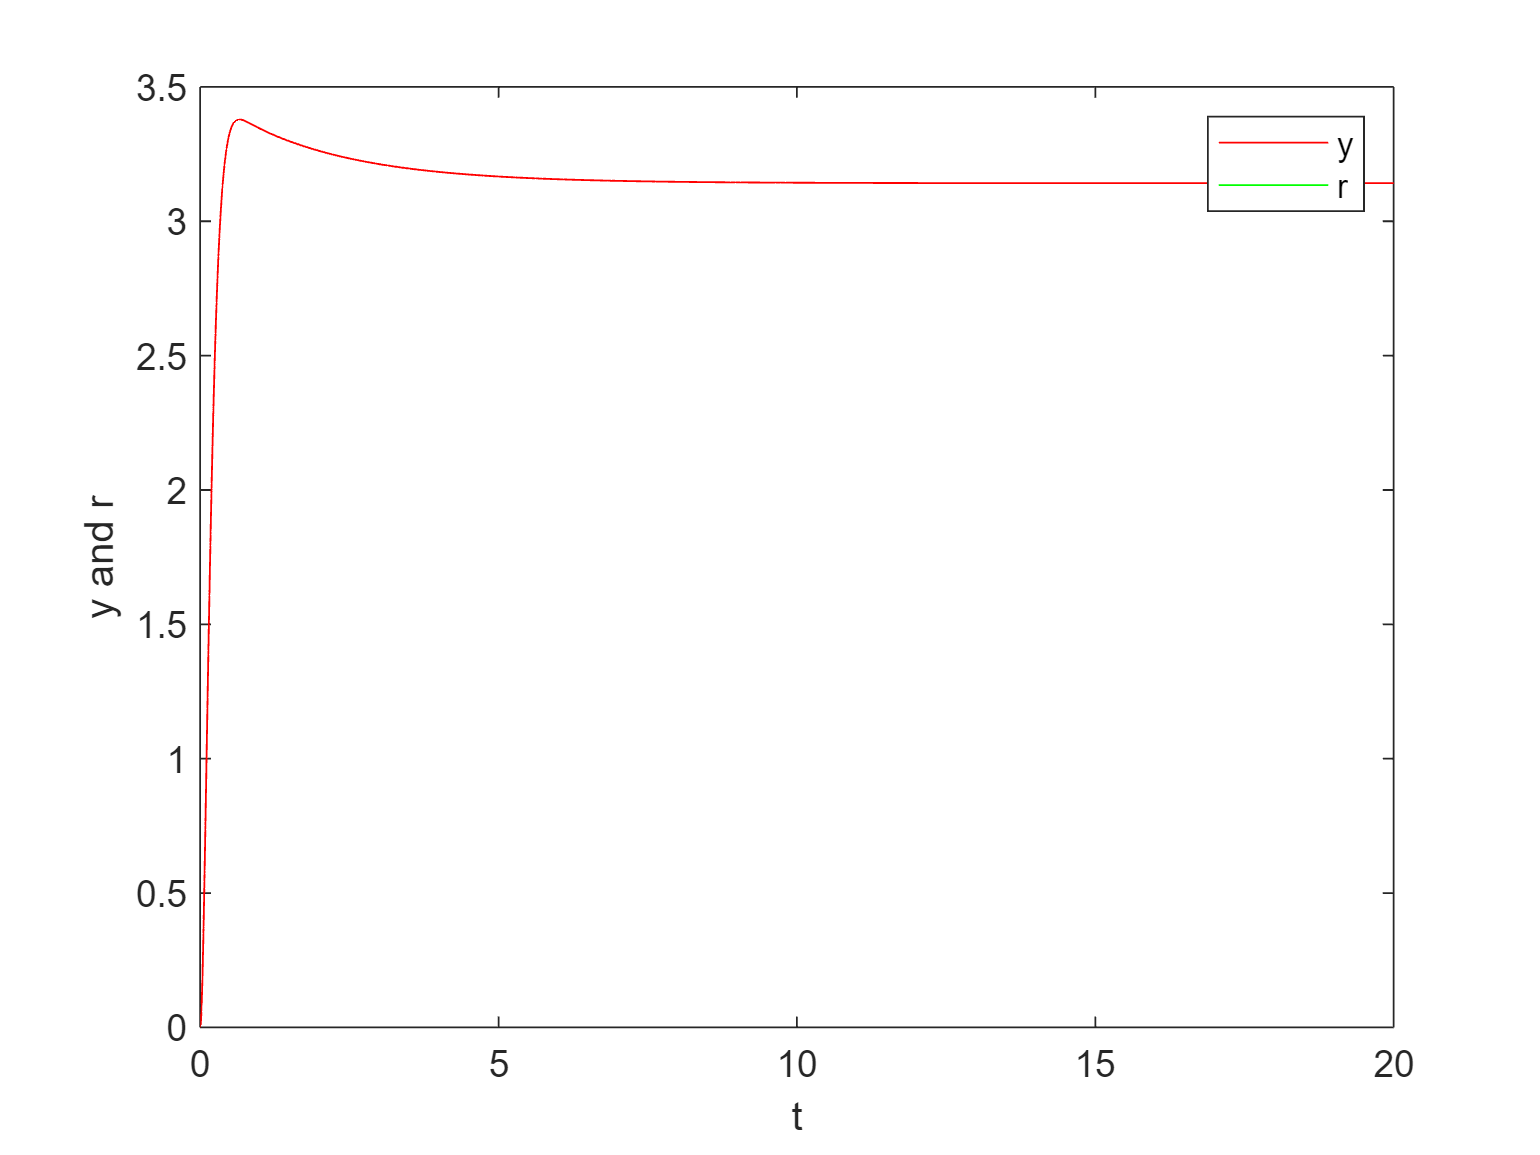

Step Information for the Output:
         RiseTime: 0.2464
    TransientTime: 3.2329
     SettlingTime: 3.2329
      SettlingMin: 2.8287
      SettlingMax: 3.3786
        Overshoot: 7.5443
       Undershoot: 0
             Peak: 3.3786
         PeakTime: 0.6612



ki=50;
Disturbo = 0;
simout=sim("FL_s_inv_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,1);

Imponendo $k_I =50$ è possibile notare come i tempi di salita e l'overshoot siano rispettati tenendo conto dei valori di $\omega_n$ e $\zeta$, oltre al fatto che le prestazioni raggiungono valori in linea con i controllori ottimali precedenti.

## **Simulazione con disturbo**

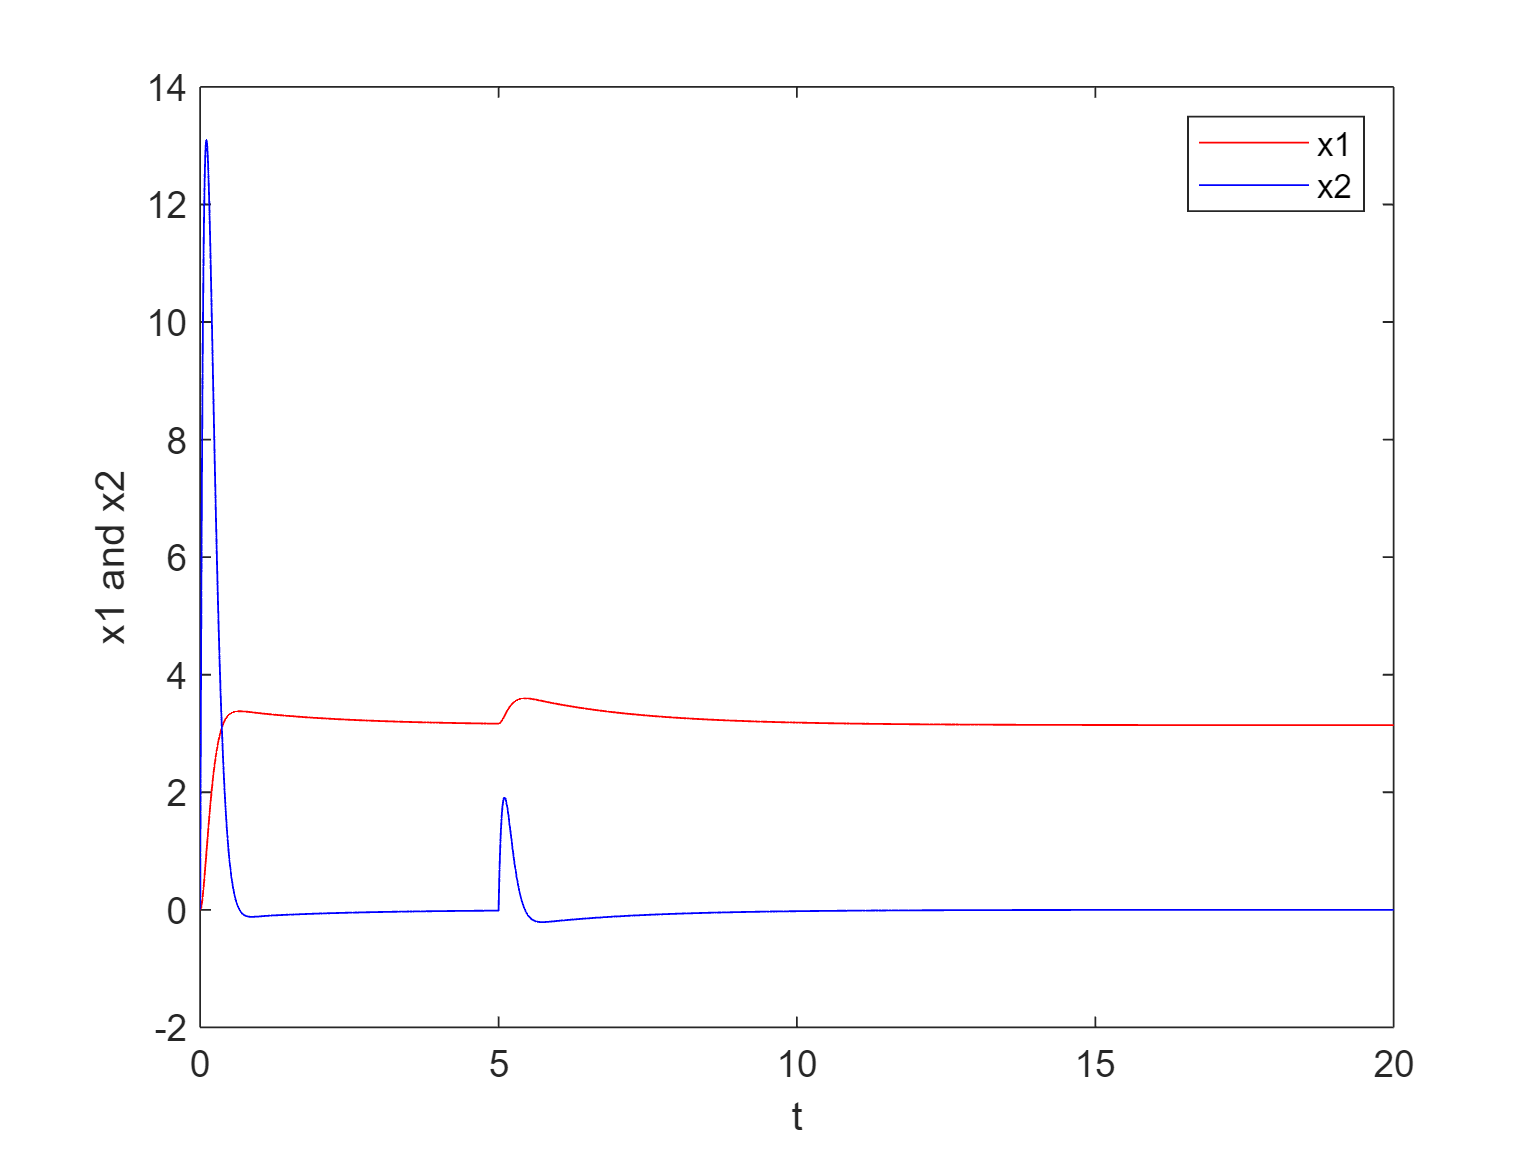

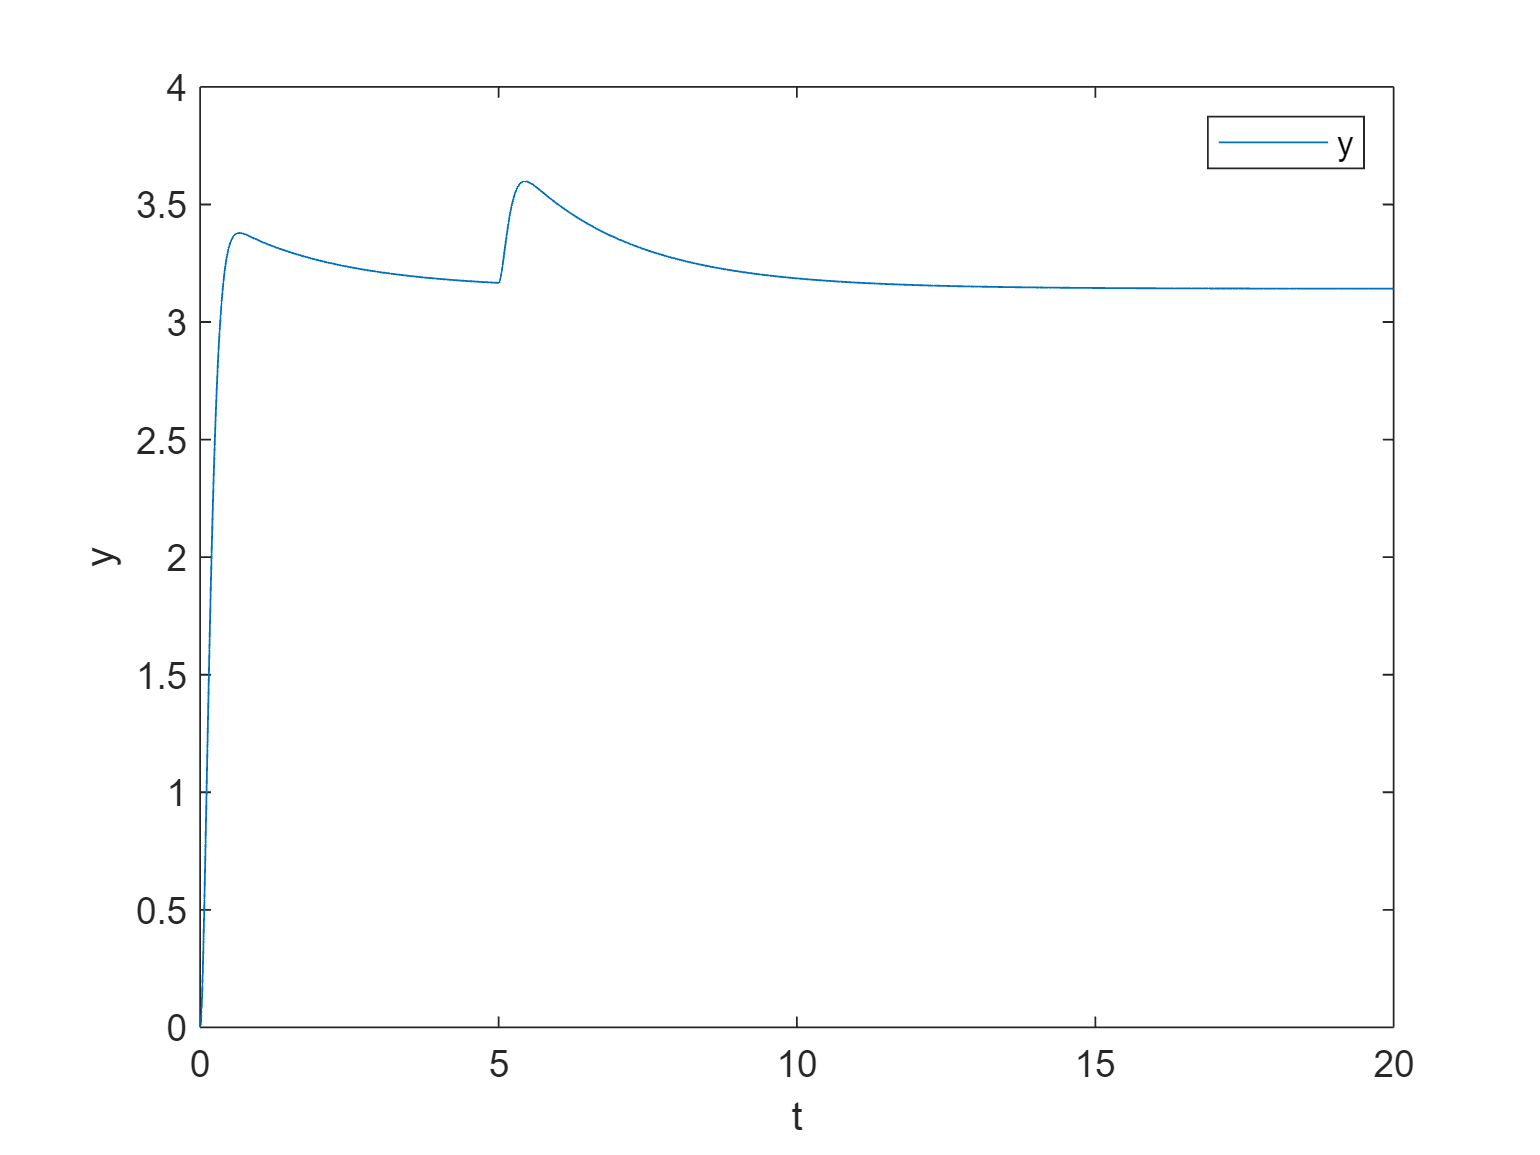

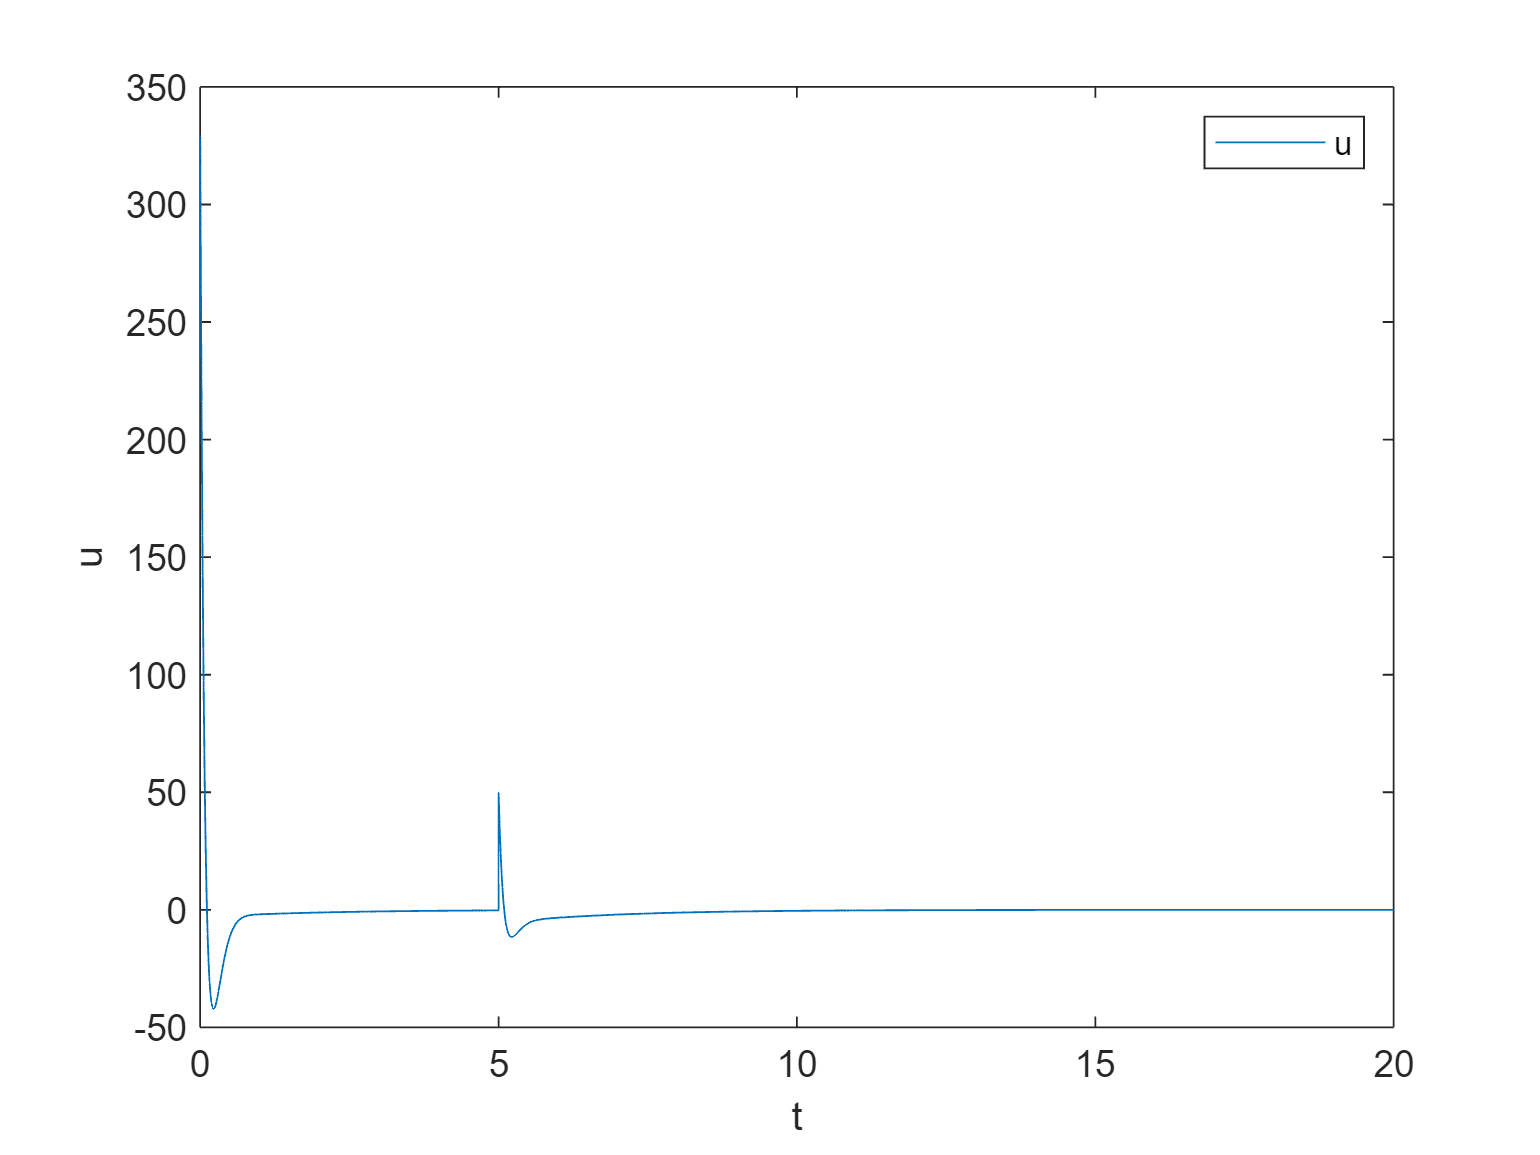

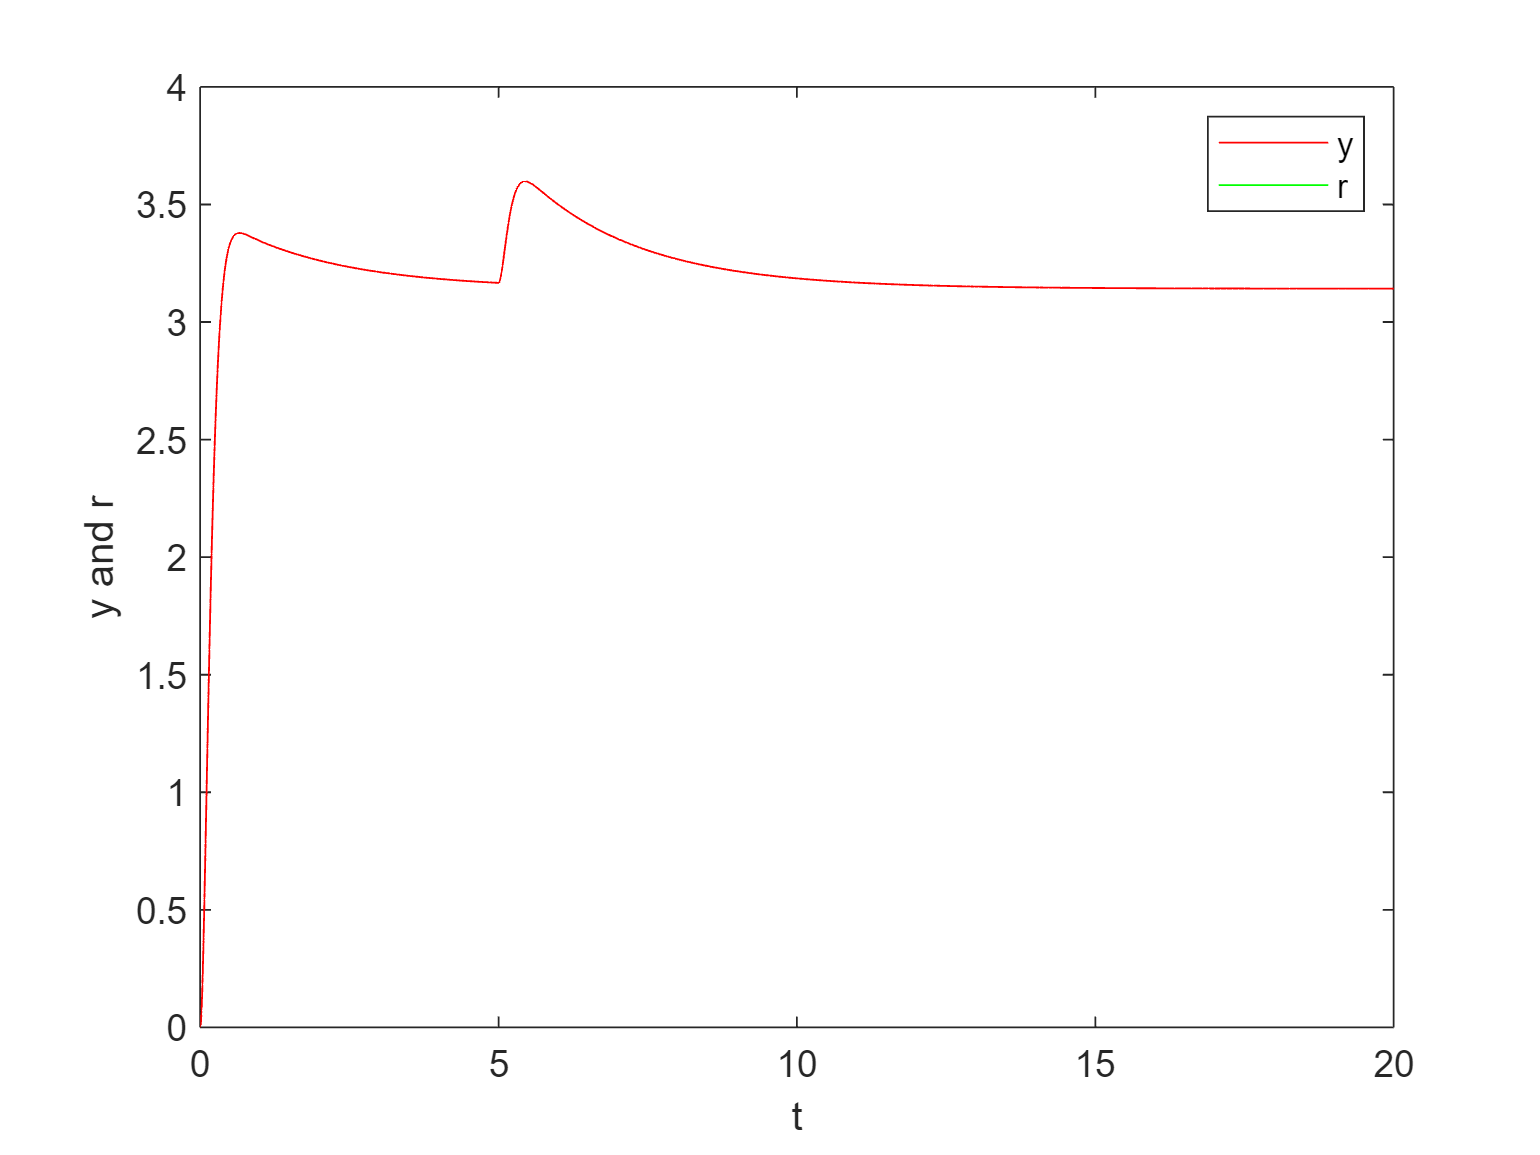

Step Information for the Output:
         RiseTime: 0.2464
    TransientTime: 9.3138
     SettlingTime: 9.3138
      SettlingMin: 2.8287
      SettlingMax: 3.5981
        Overshoot: 14.5238
       Undershoot: 0
             Peak: 3.5981
         PeakTime: 5.4420



ki=50;
Disturbo = 50;
simout=sim("FL_s_inv_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,1);

E' interessante notare la rapidità con la quale il disturbo viene abbattuto, più velocemente rispetto al caso LQI.

## Segnale tempo variante - Azione integrale

Si consideri anzitutto lo stesso schema visto in corrispondenza dell'azione integrale sul segnale tempo invariante, con alcune modifiche come di seguito:

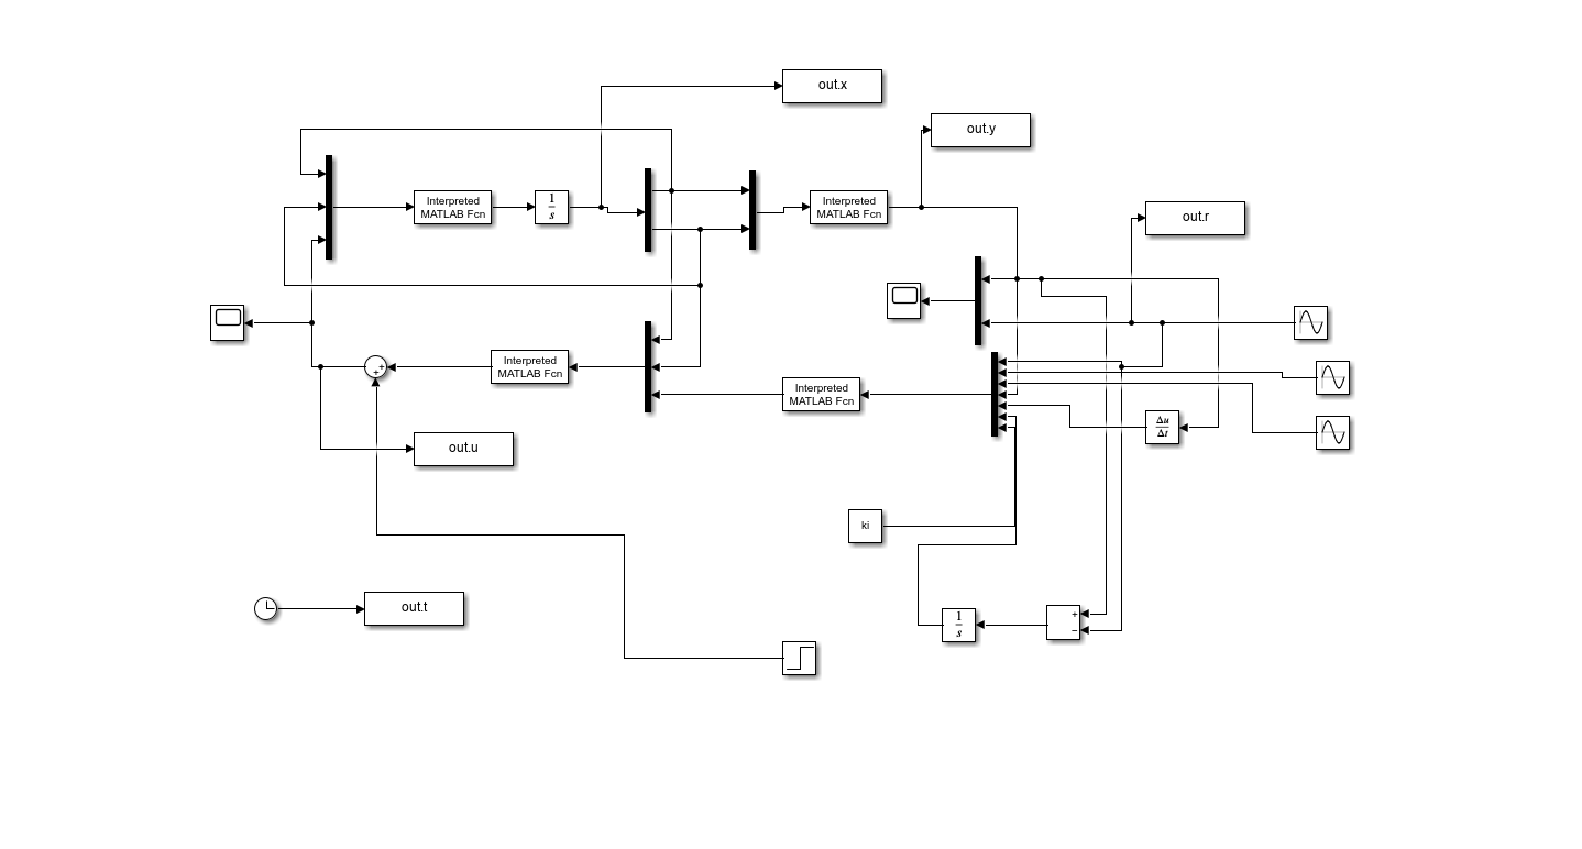

imshow(imread("img/feedback_tv_ia_scheme.png"))

Le modifiche sono legate principalmente al nuovo tipo di segnale da gestire e in generale all'architettura diversa dovuta al controllore differente. Il controllore avrà forma del tipo $u(t)=\ddot y_d - \alpha (\dot y - \dot y_d)-\beta (y-y_d) -k_i \int (y-y_d)
$. 

## **Simulazione senza disturbo**

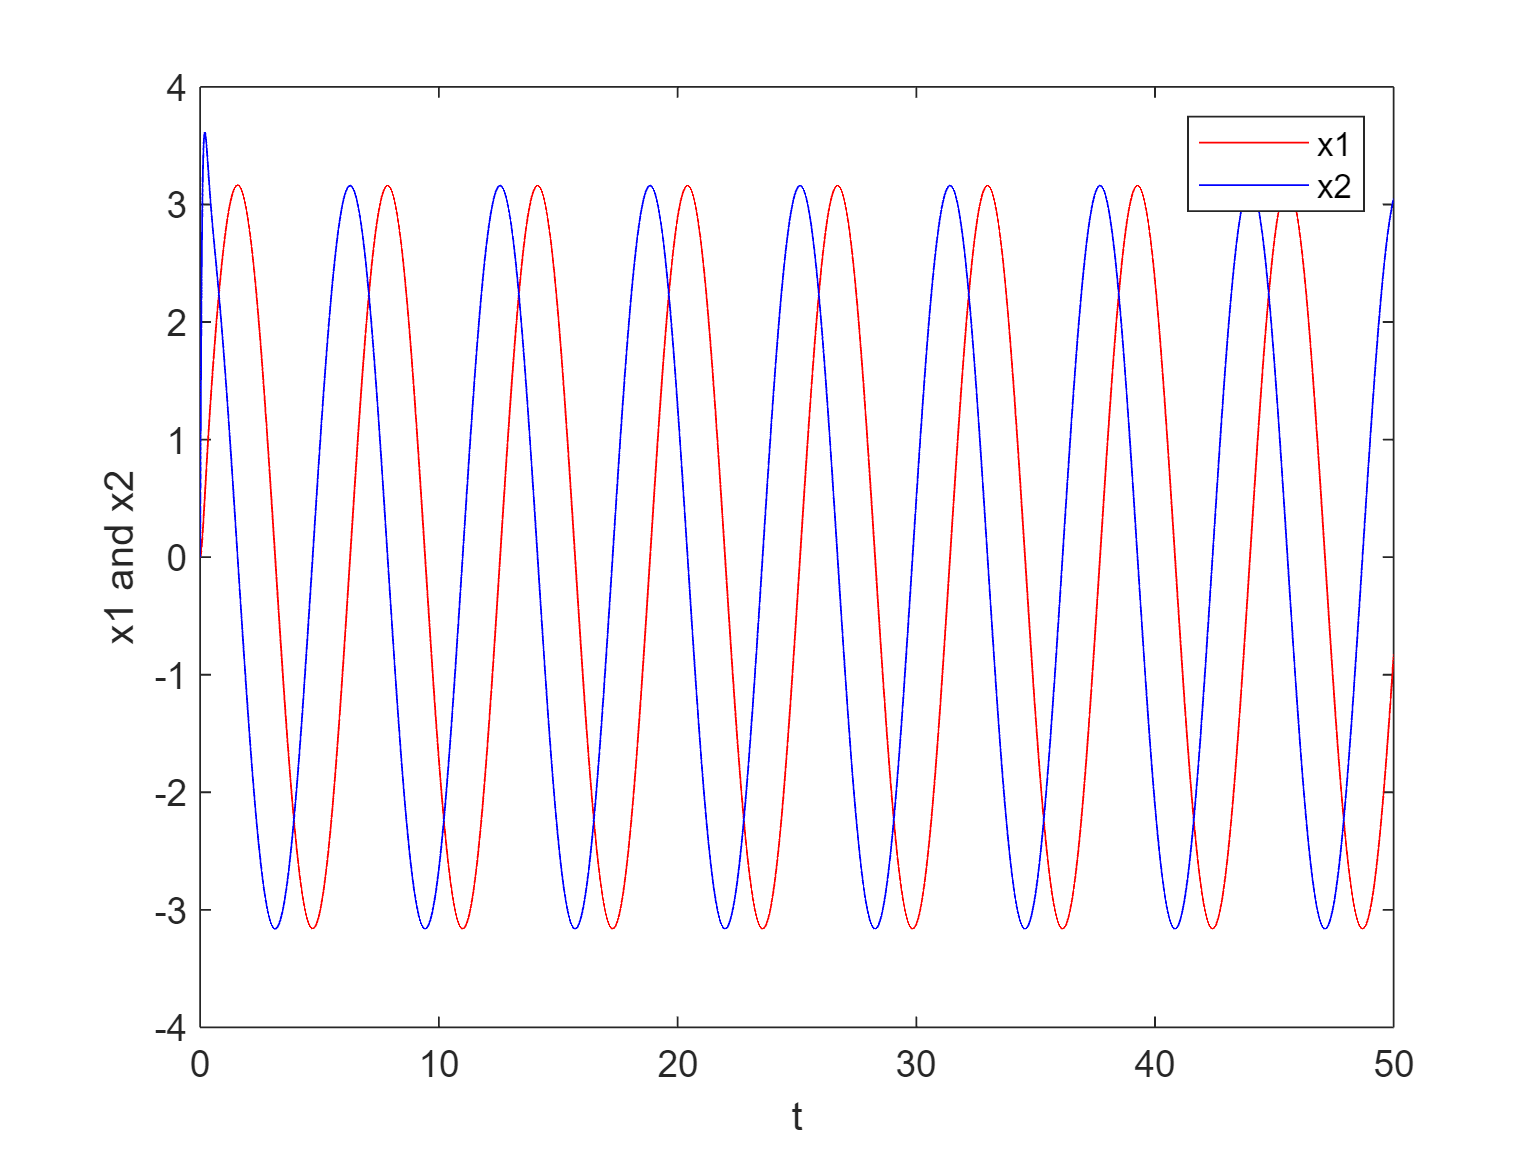

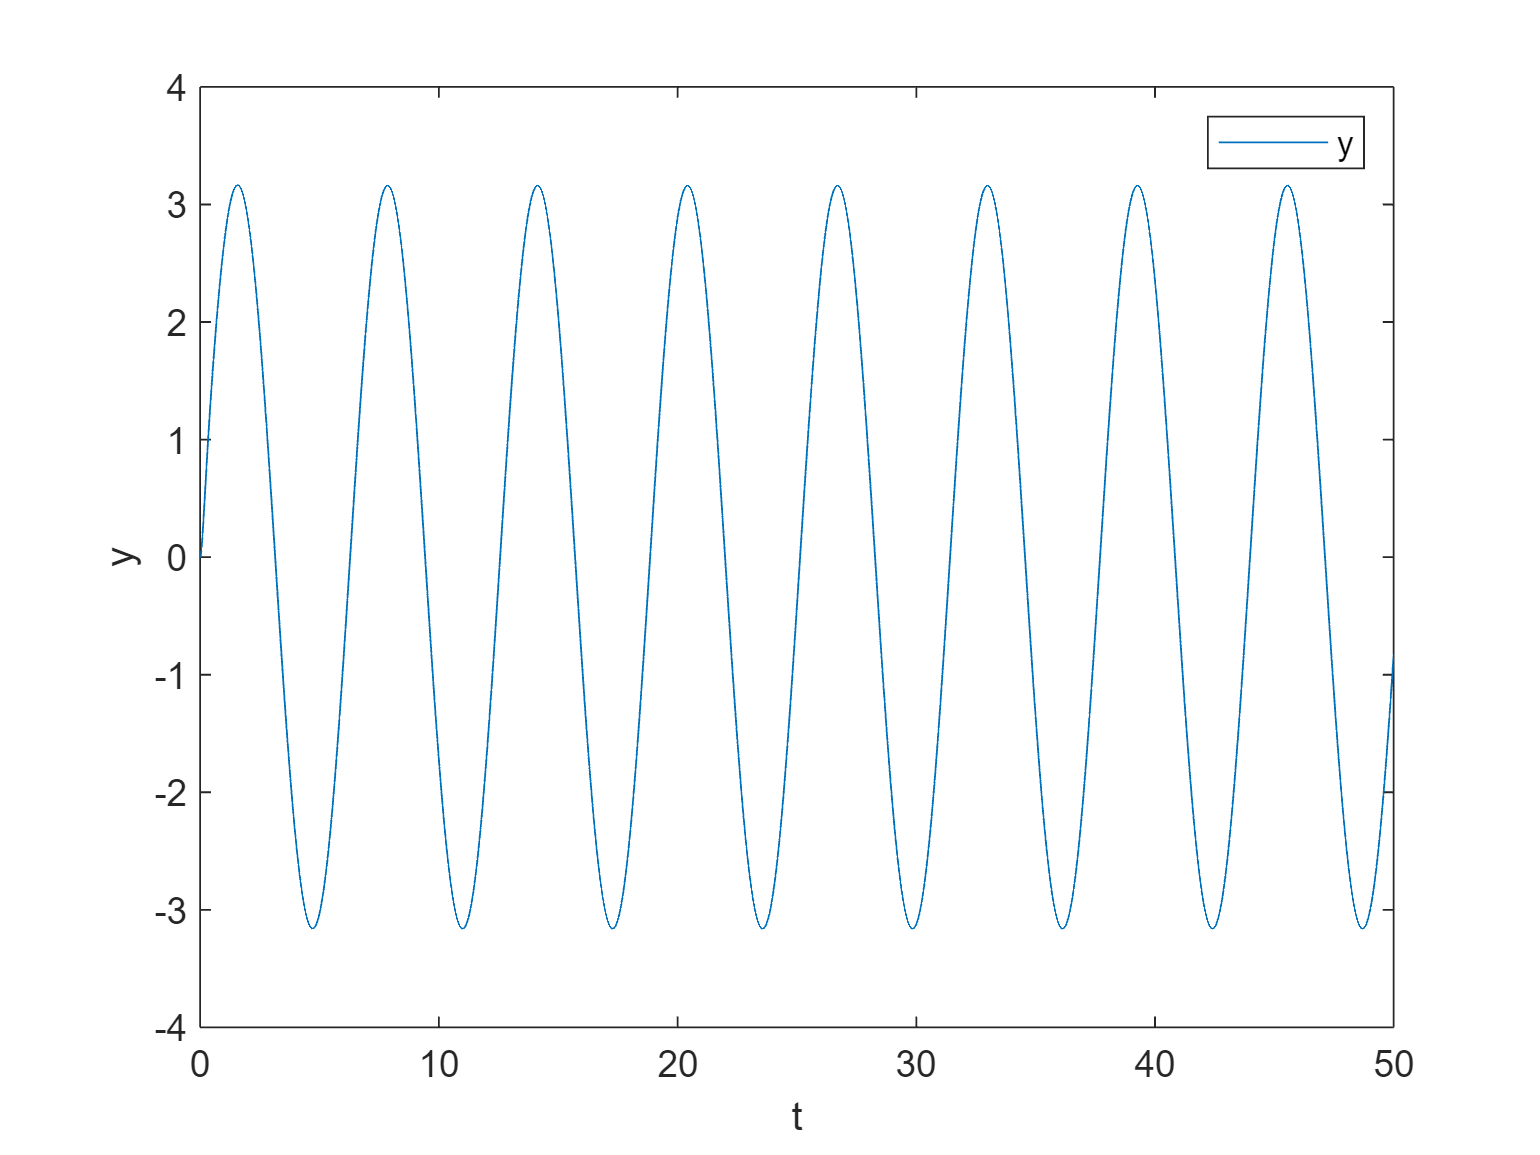

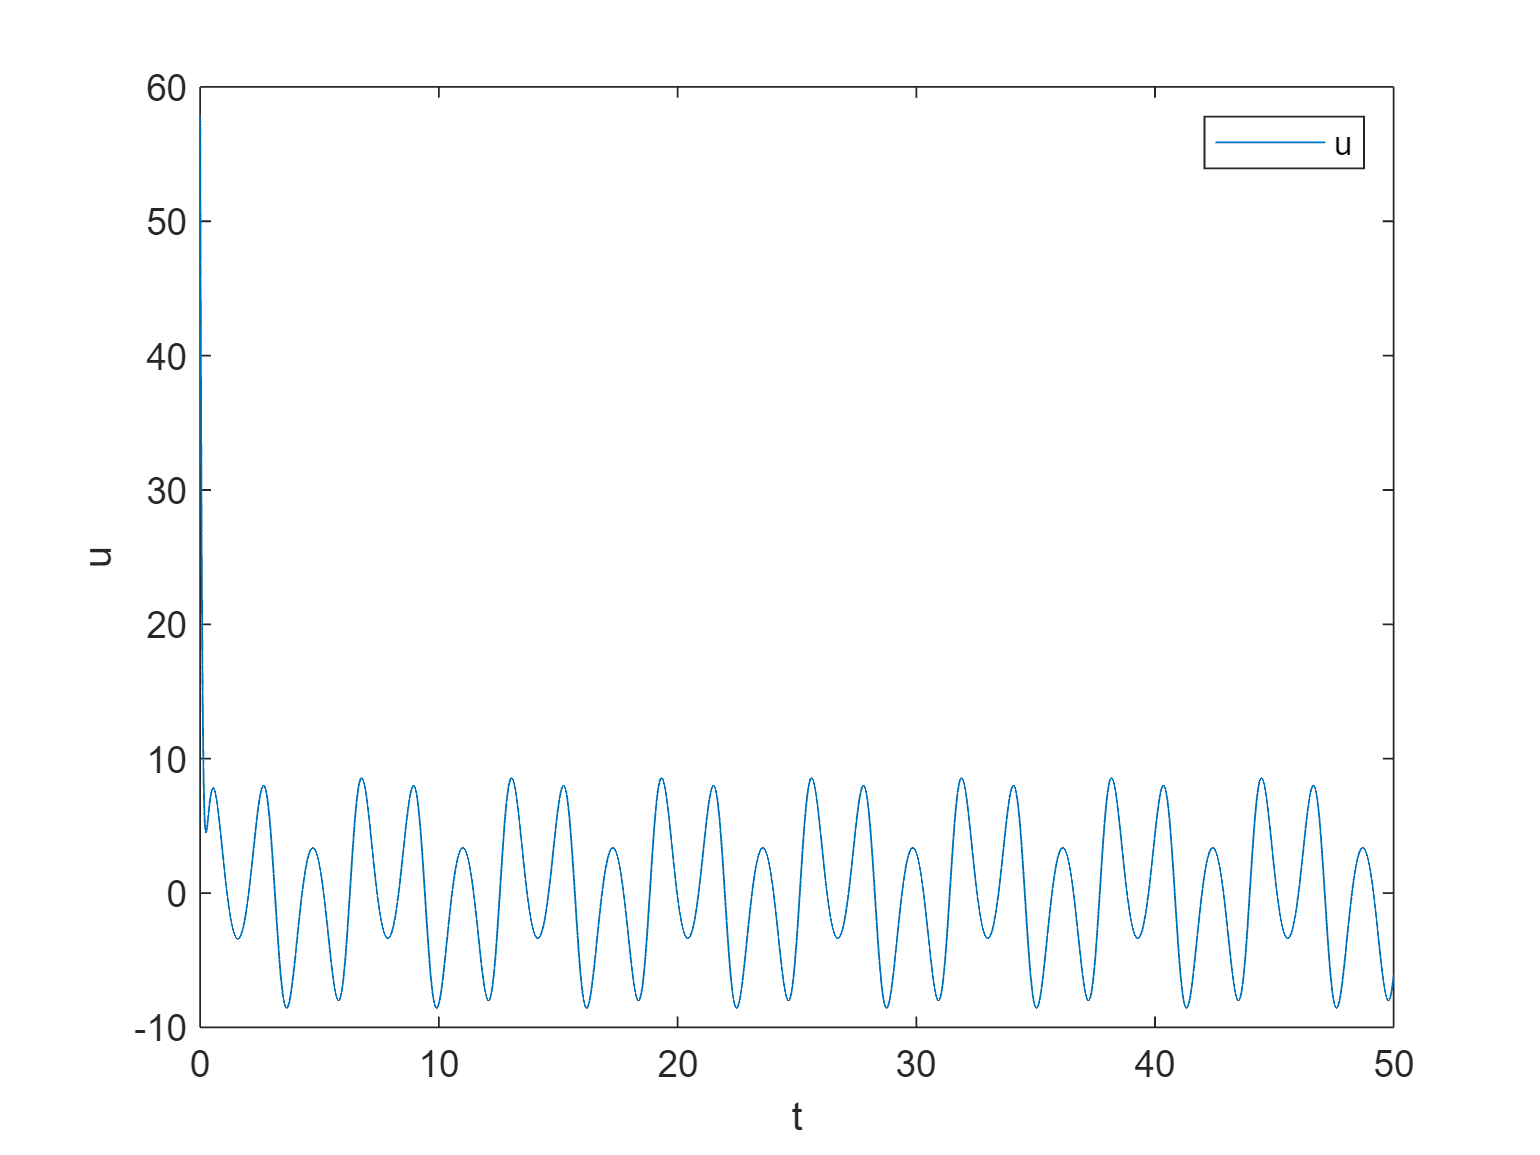

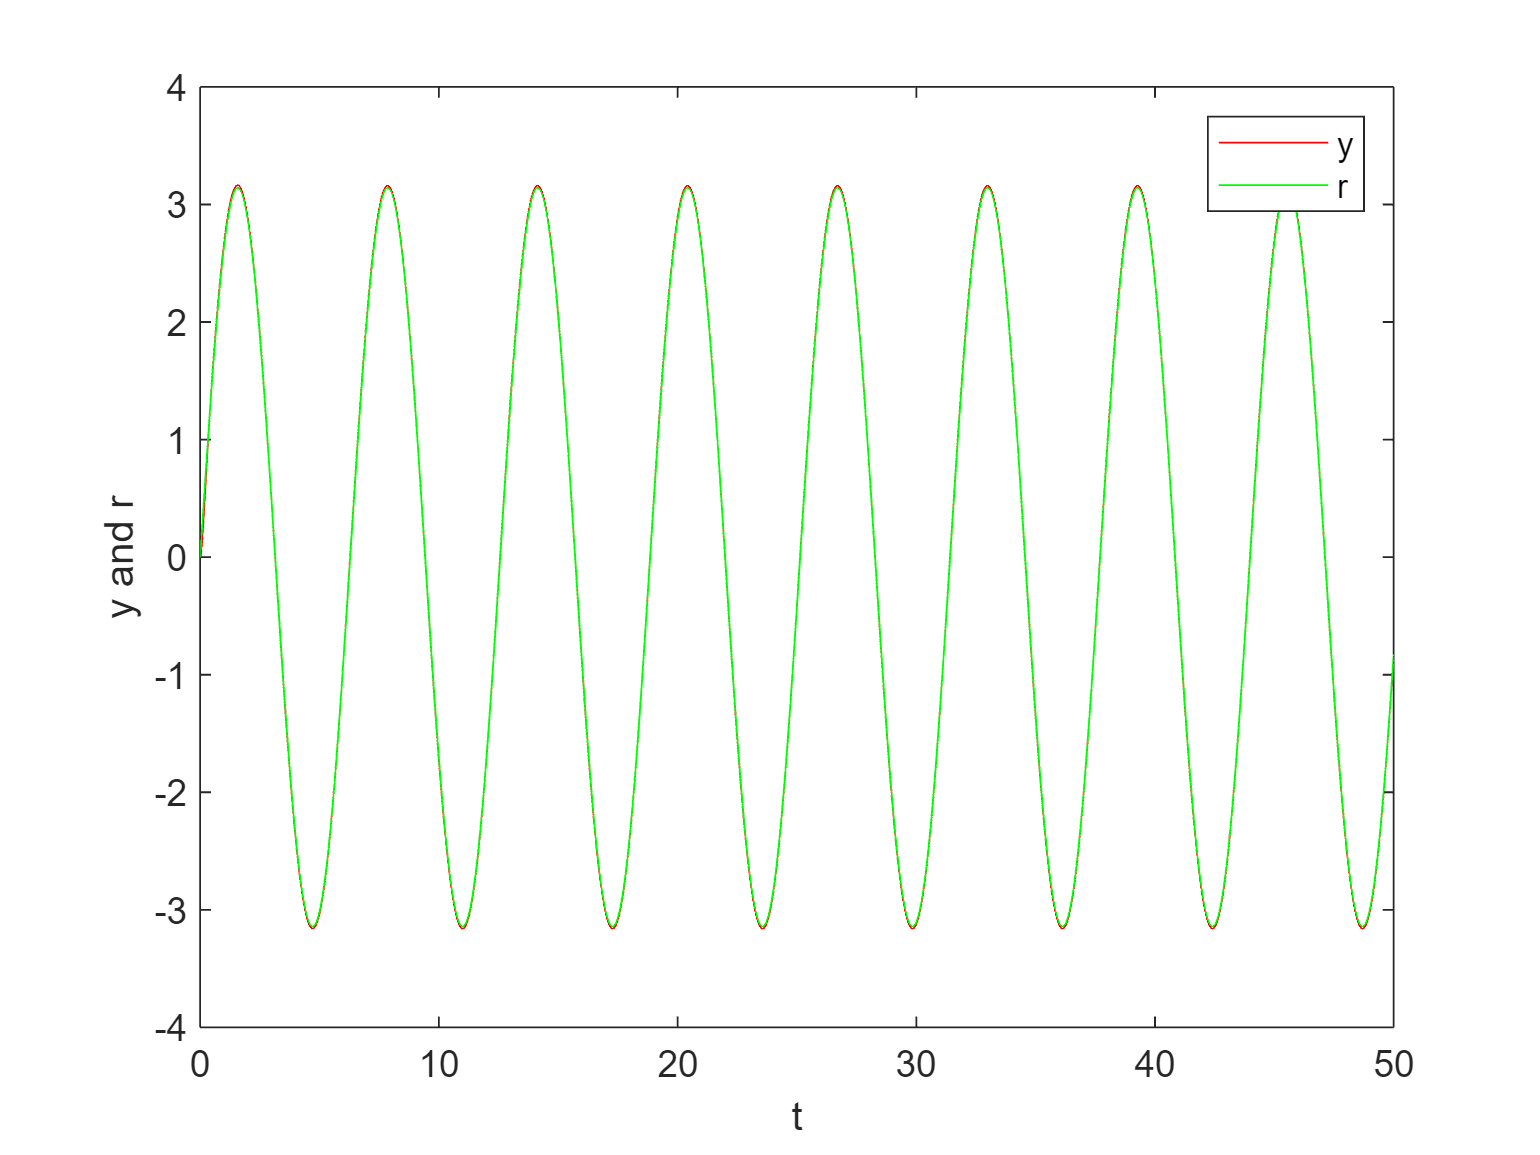

ki=50;
Disturbo=0;
simout=sim("FL_s_v_seno_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0);

In assenza di disturbo è interessante notare l'efficacia dell'inseguimento del riferimento, lasciando un margine di errore impercettibile. Vediamo con la rampa:

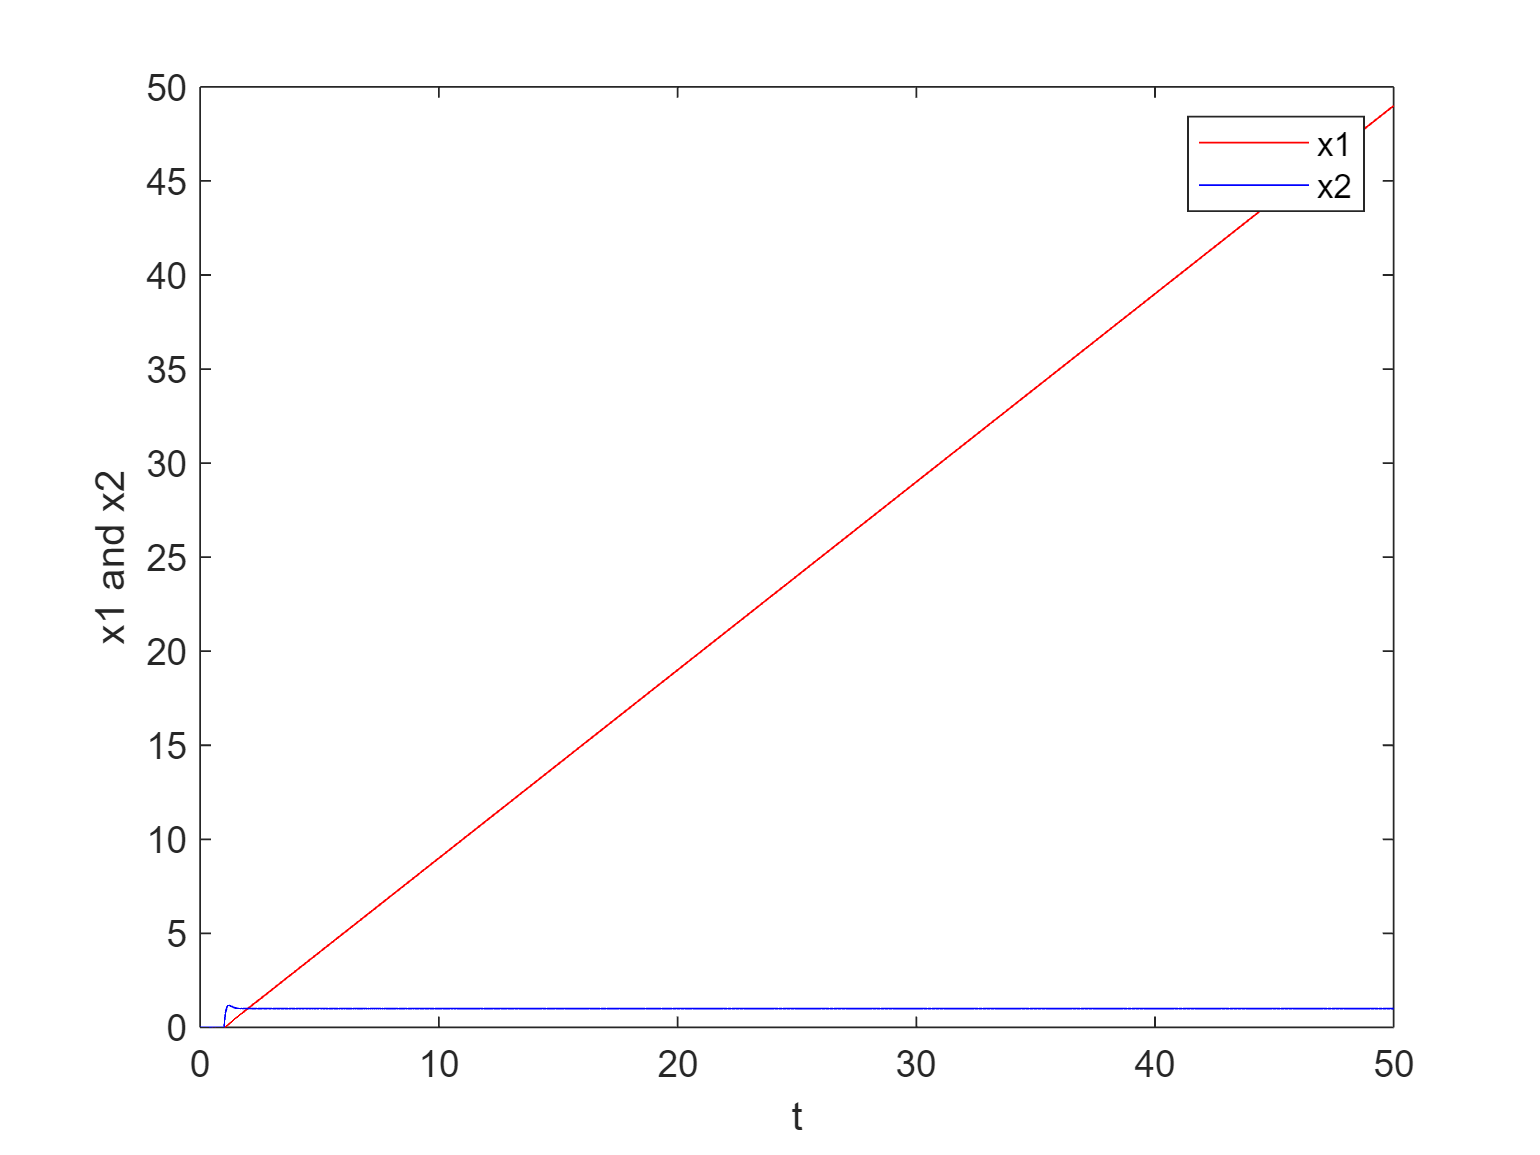

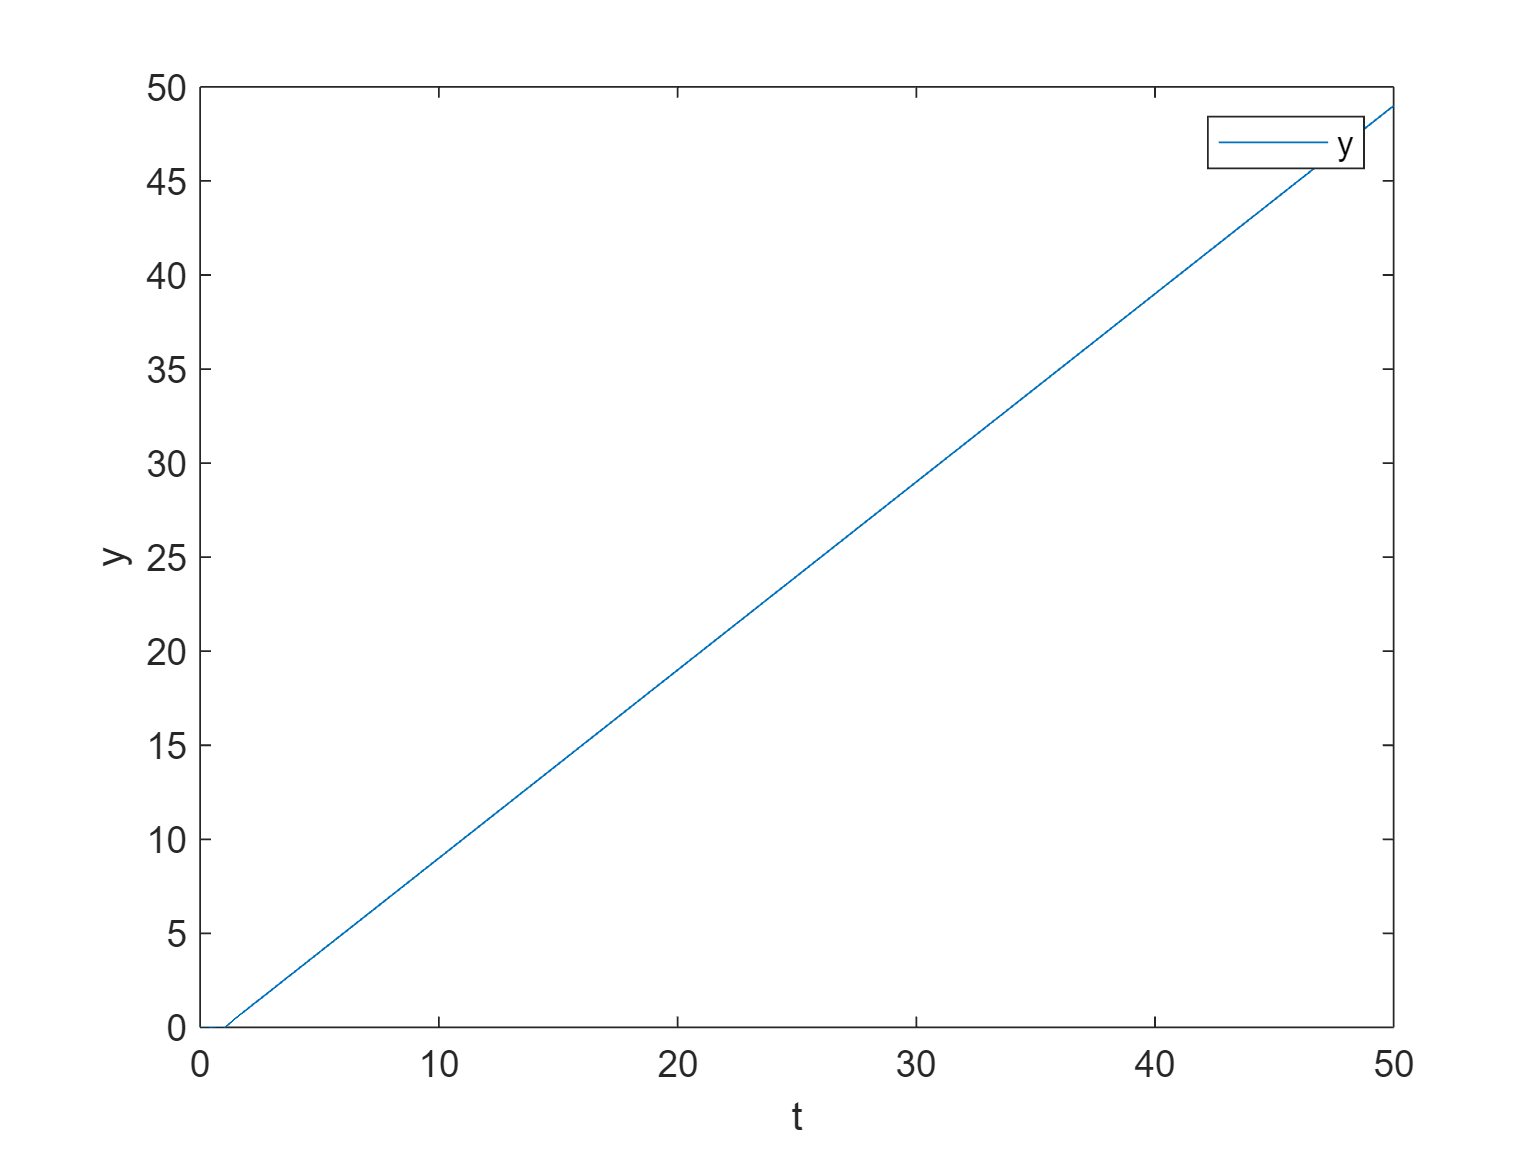

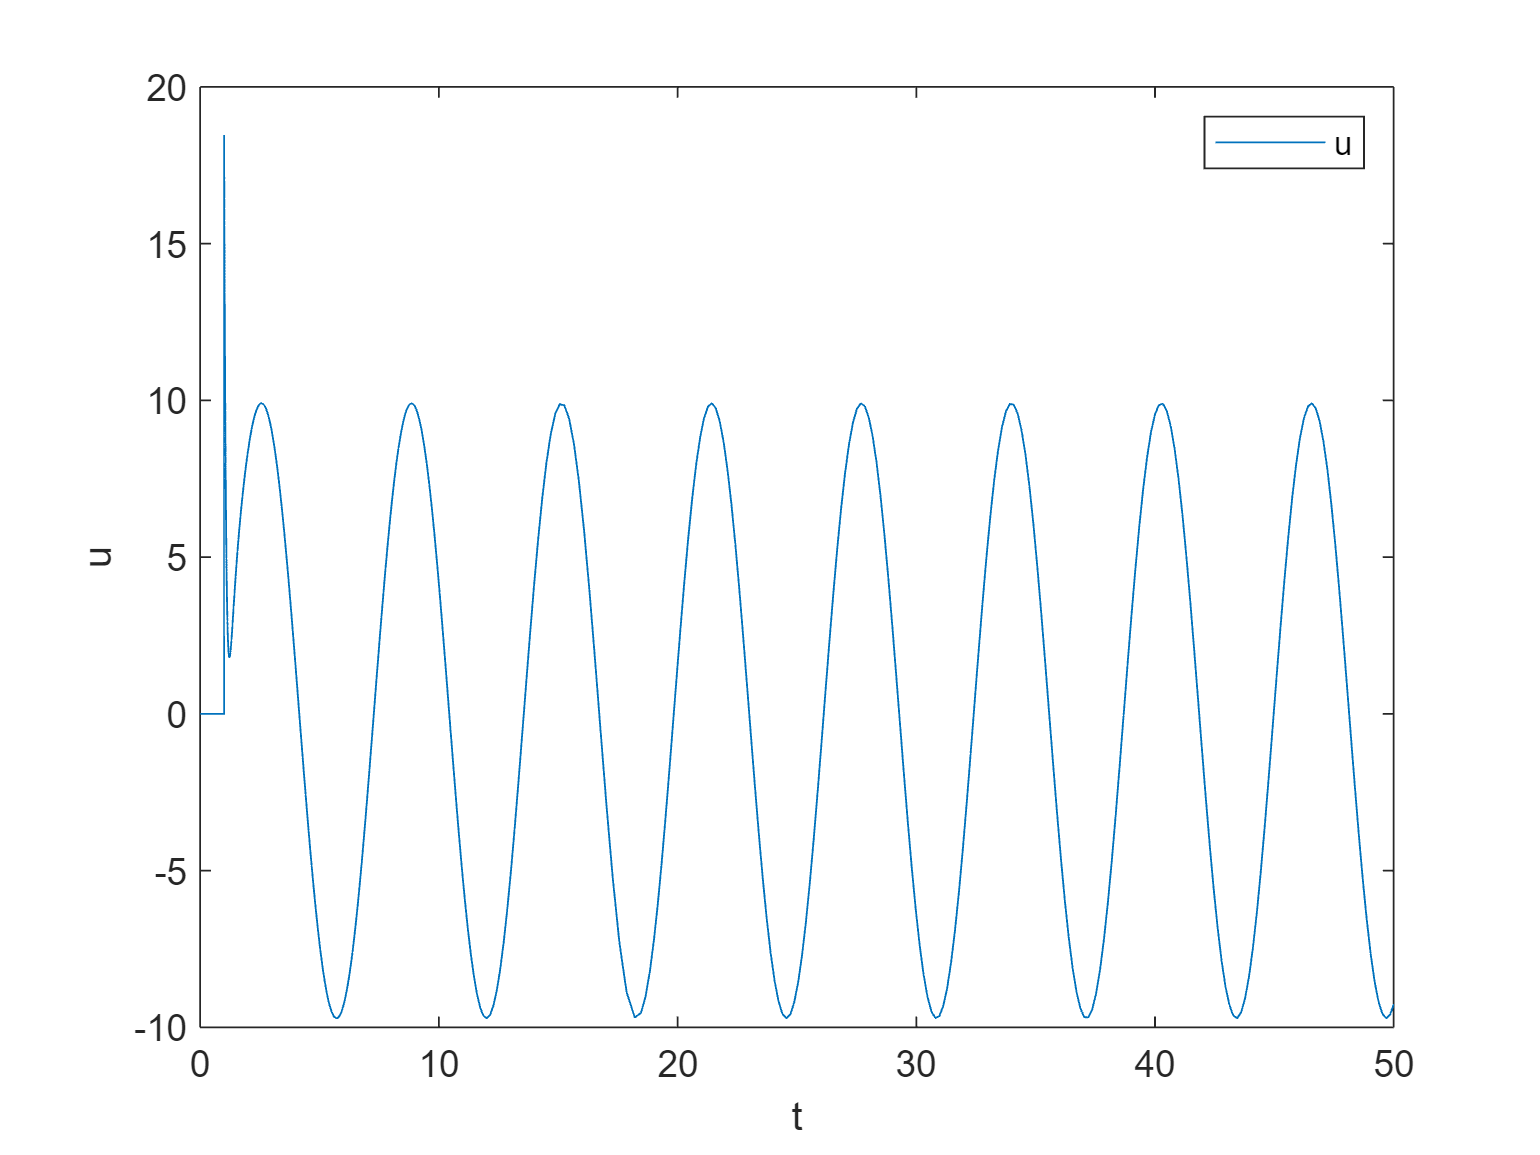

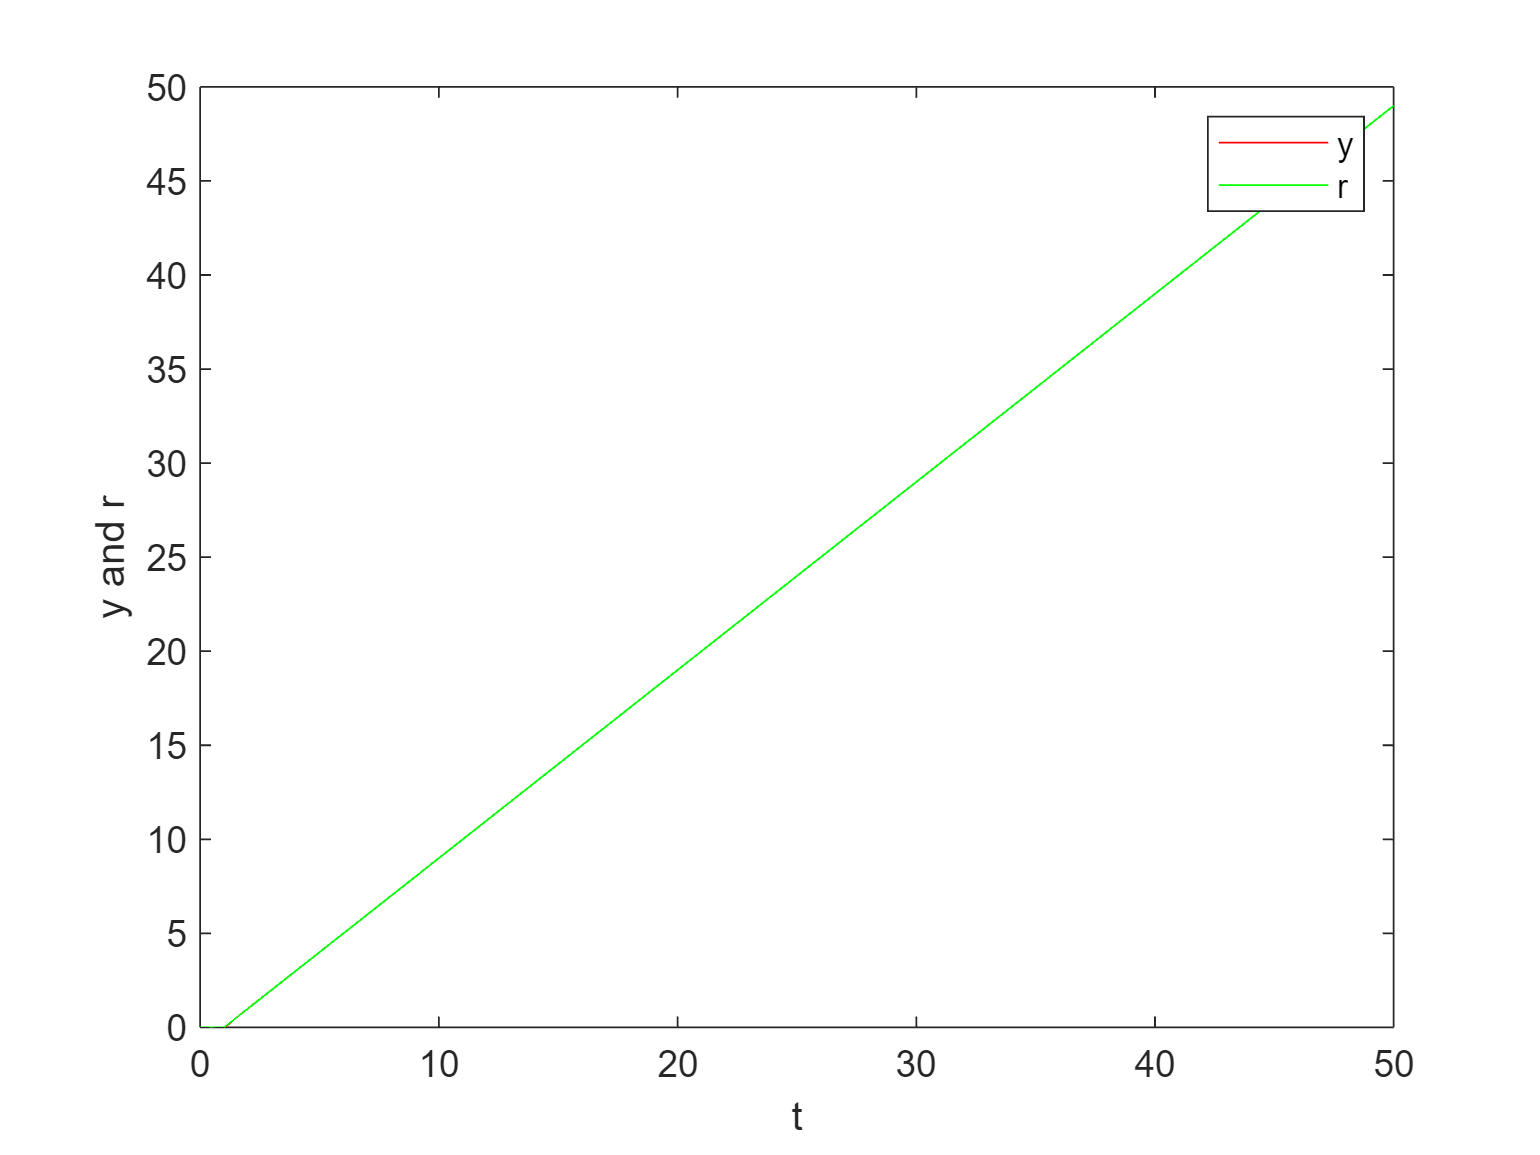

ki=50;
Disturbo=0;
simout=sim("FL_s_v_rampa_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0);

## **Simulazione con disturbo**

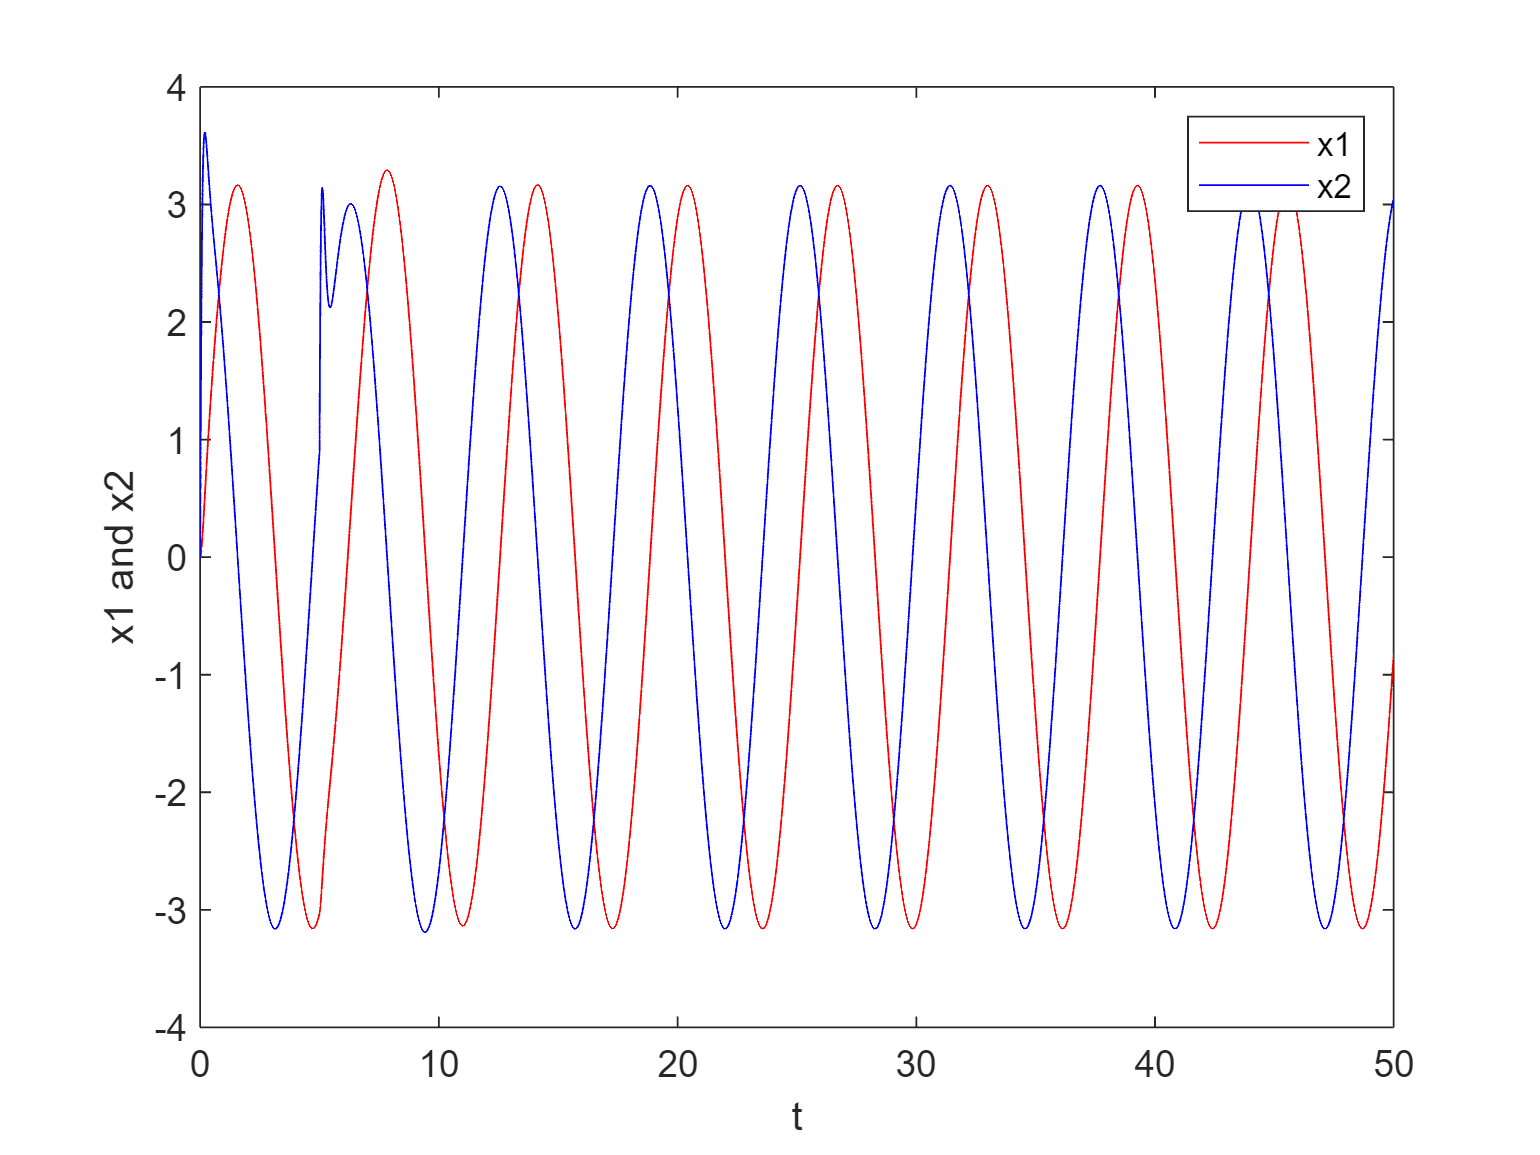

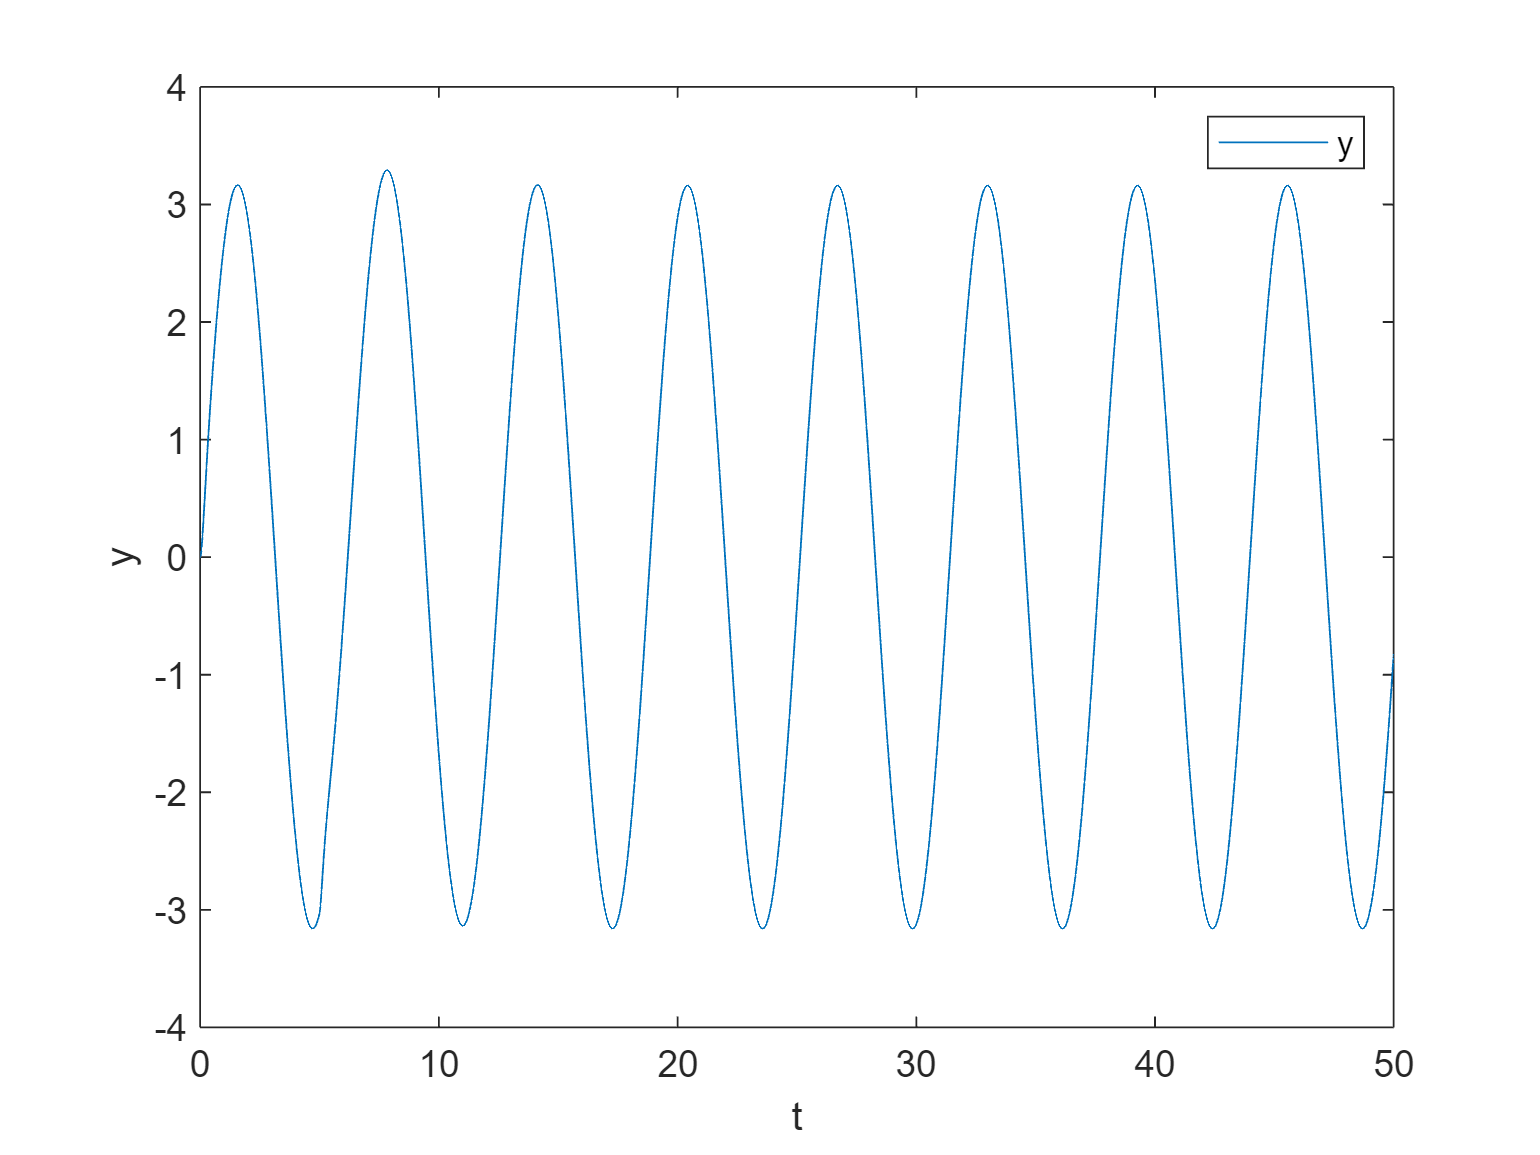

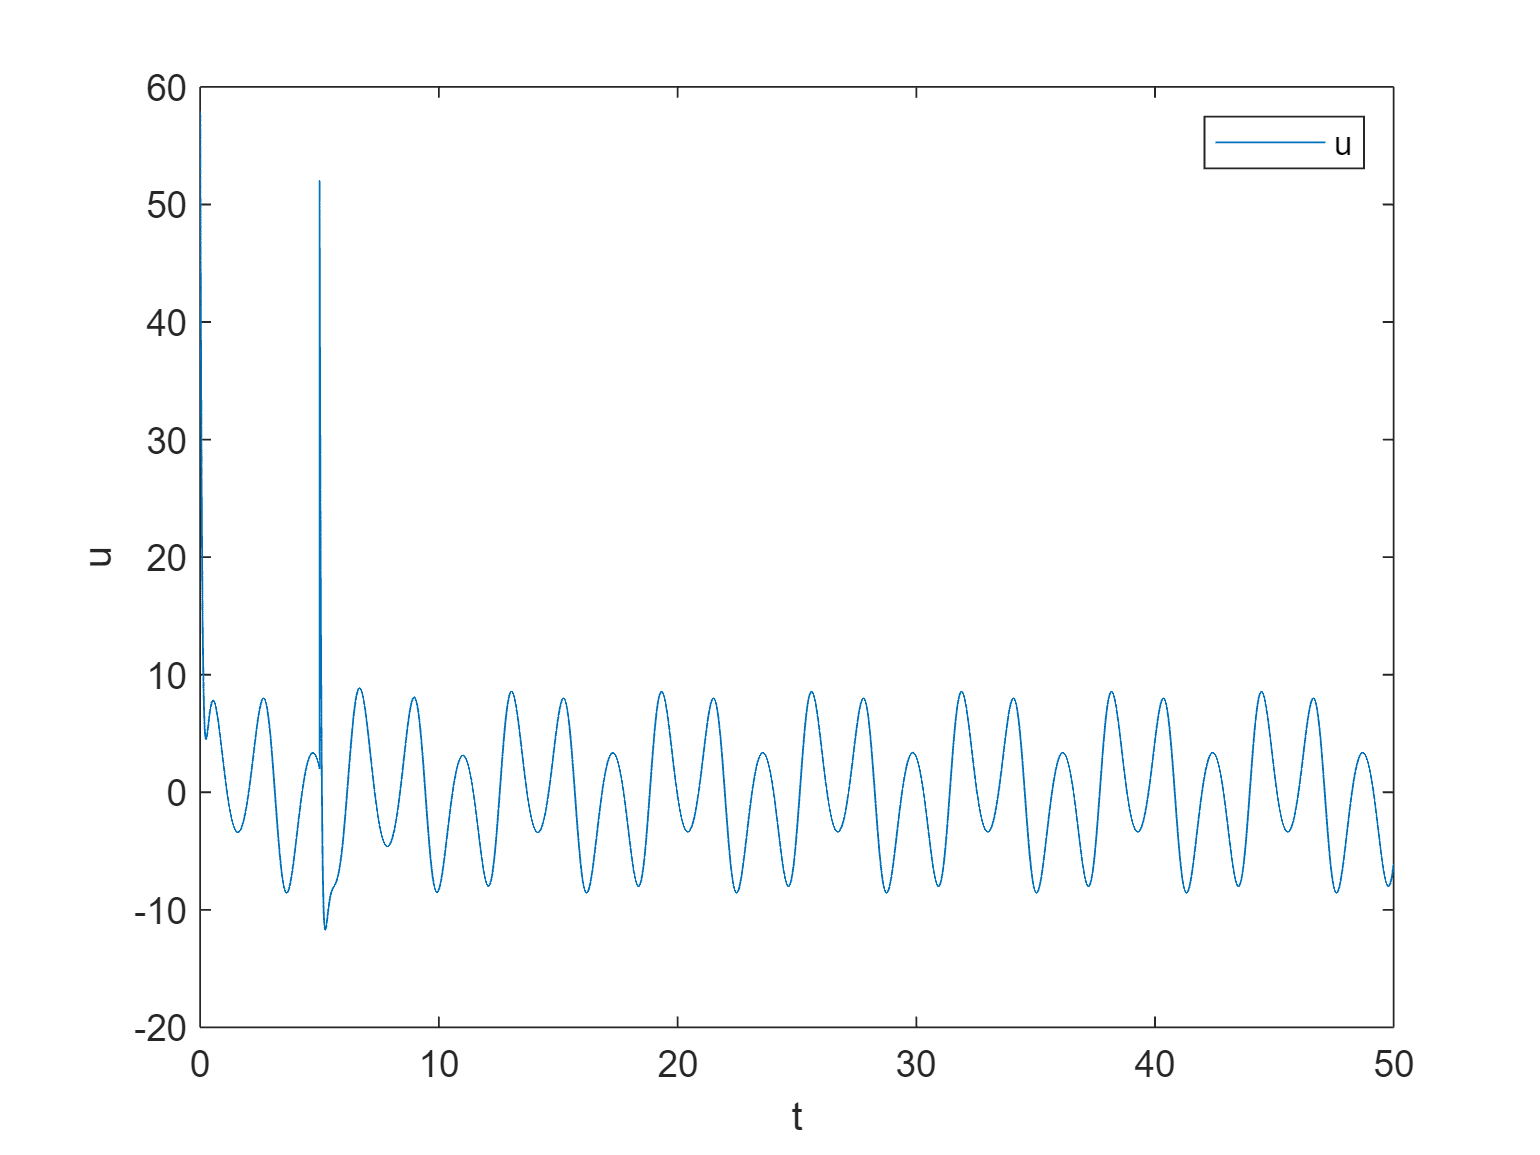

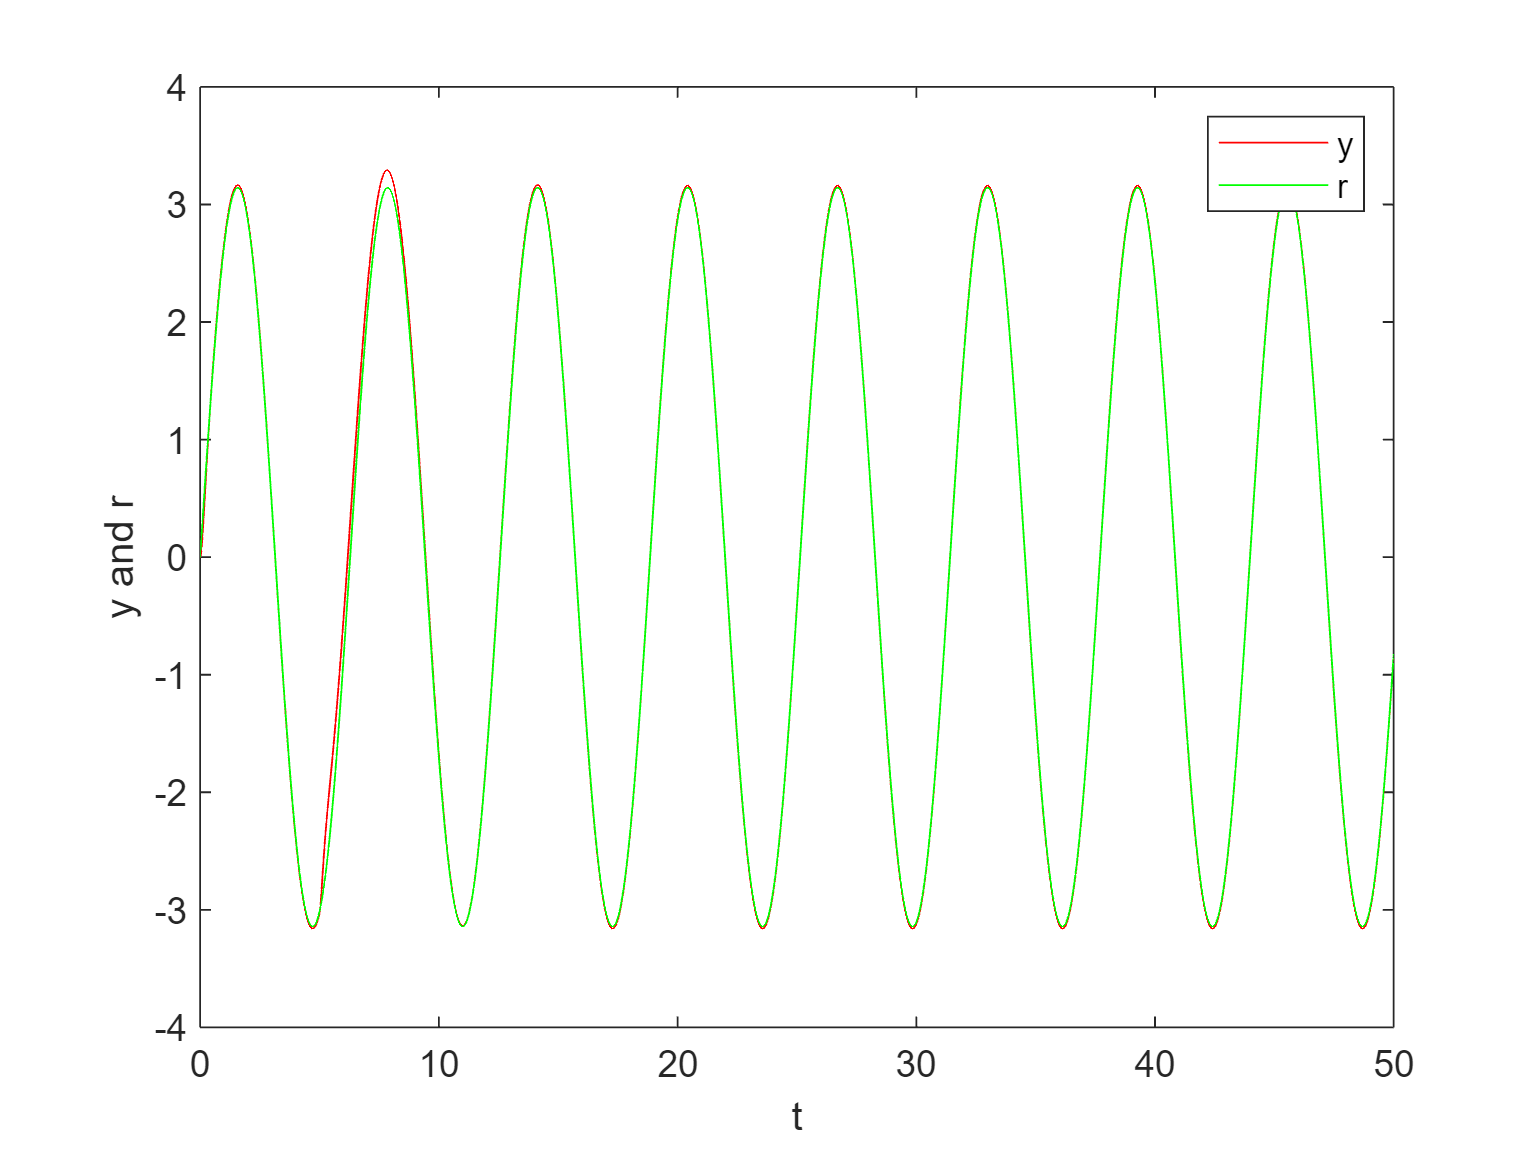

ki=50;
Disturbo=50;
simout=sim("FL_s_v_seno_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0)

Anche in presenza di disturbo, il controllore appena proposto riesce correttamente ad inseguire il segnale ed ad abbattere il disturbo in tempi brevi.Vediamo con la rampa:

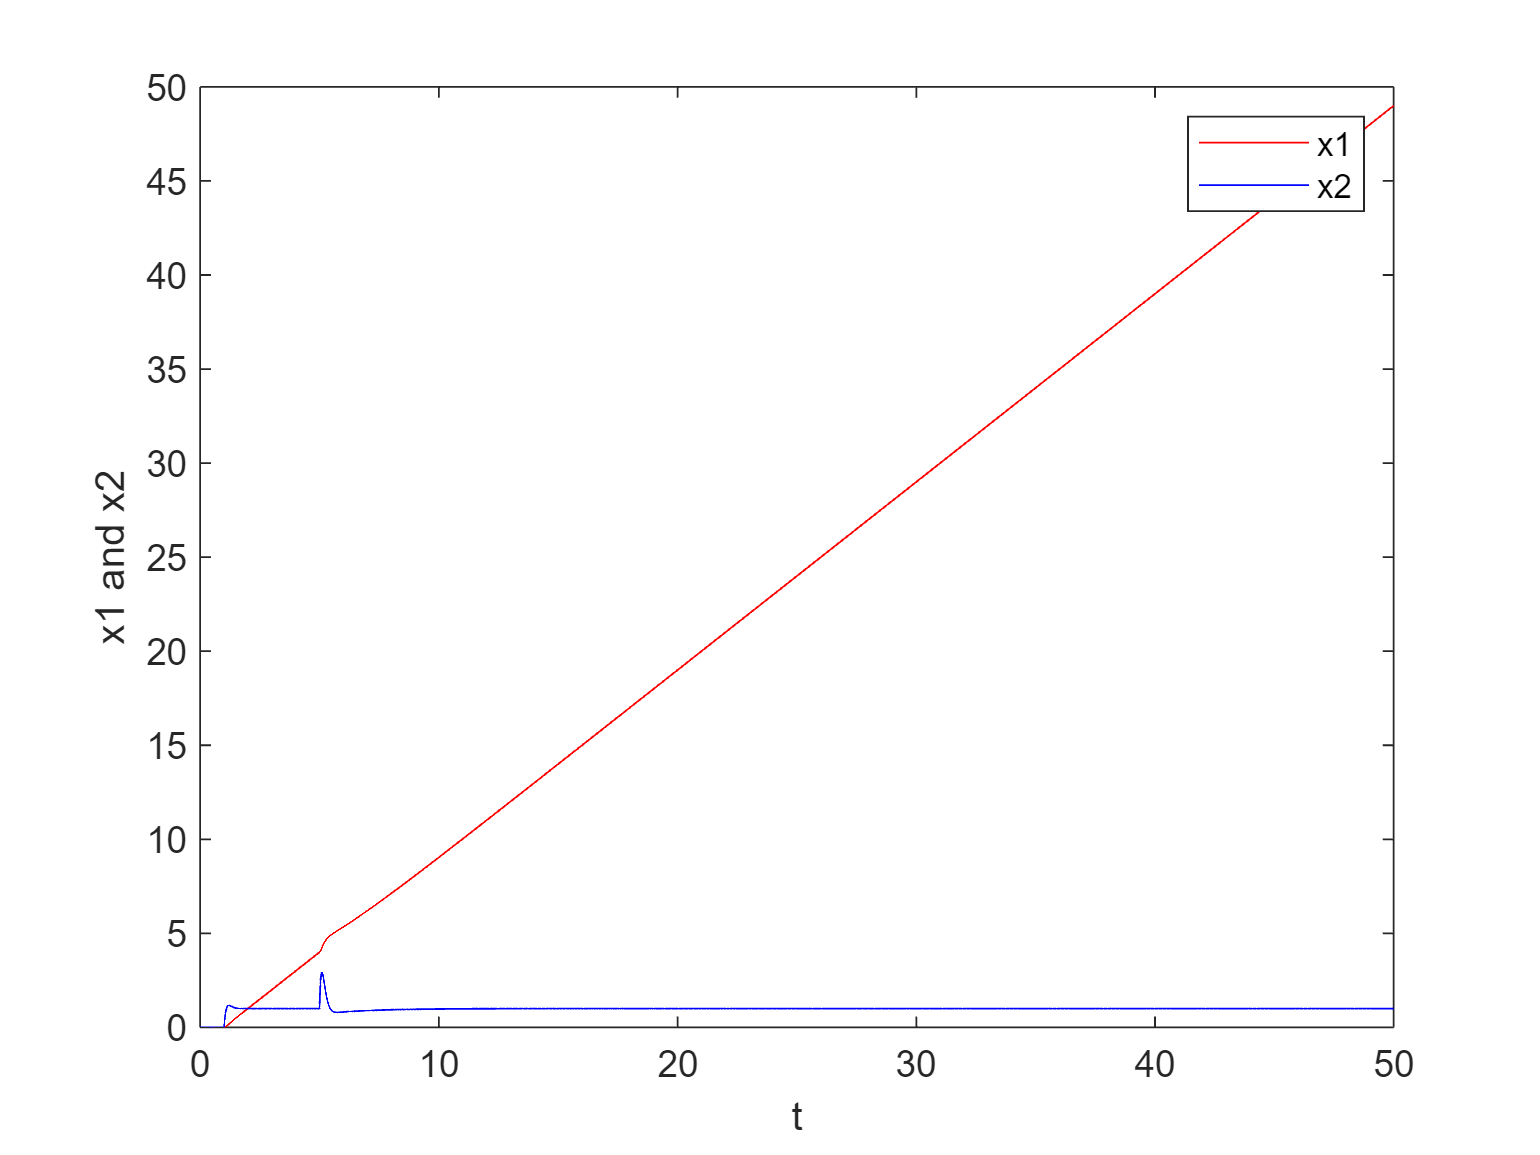

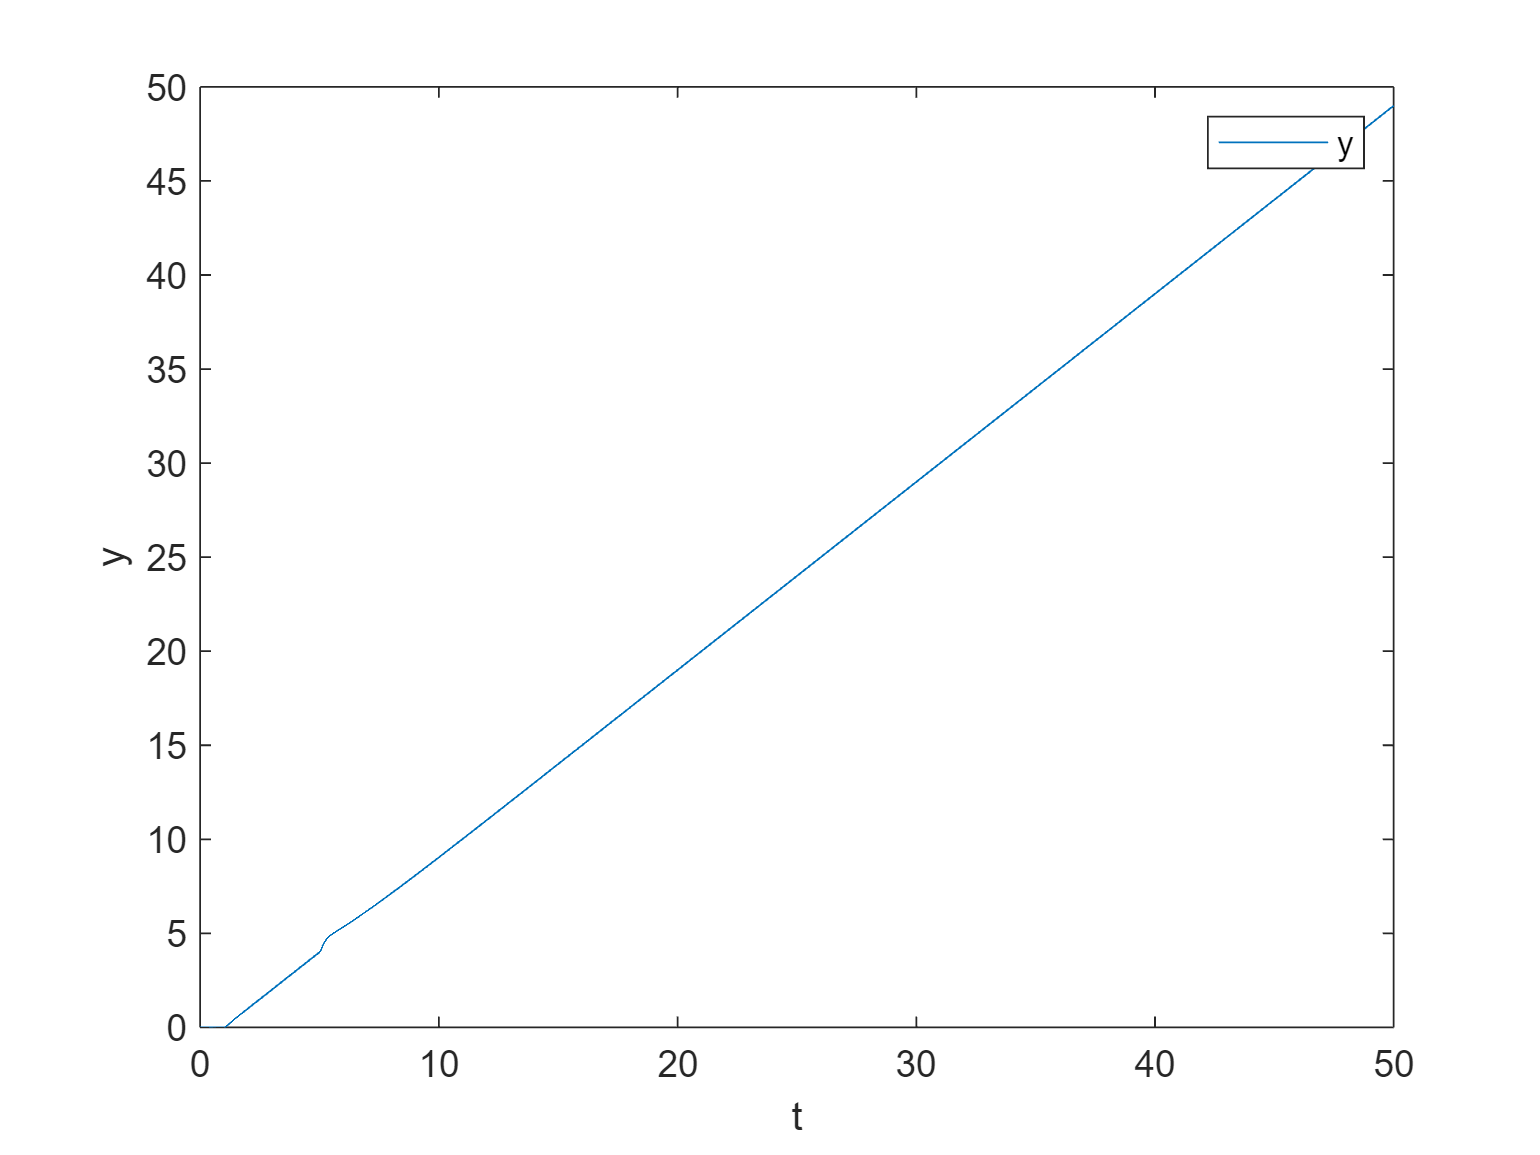

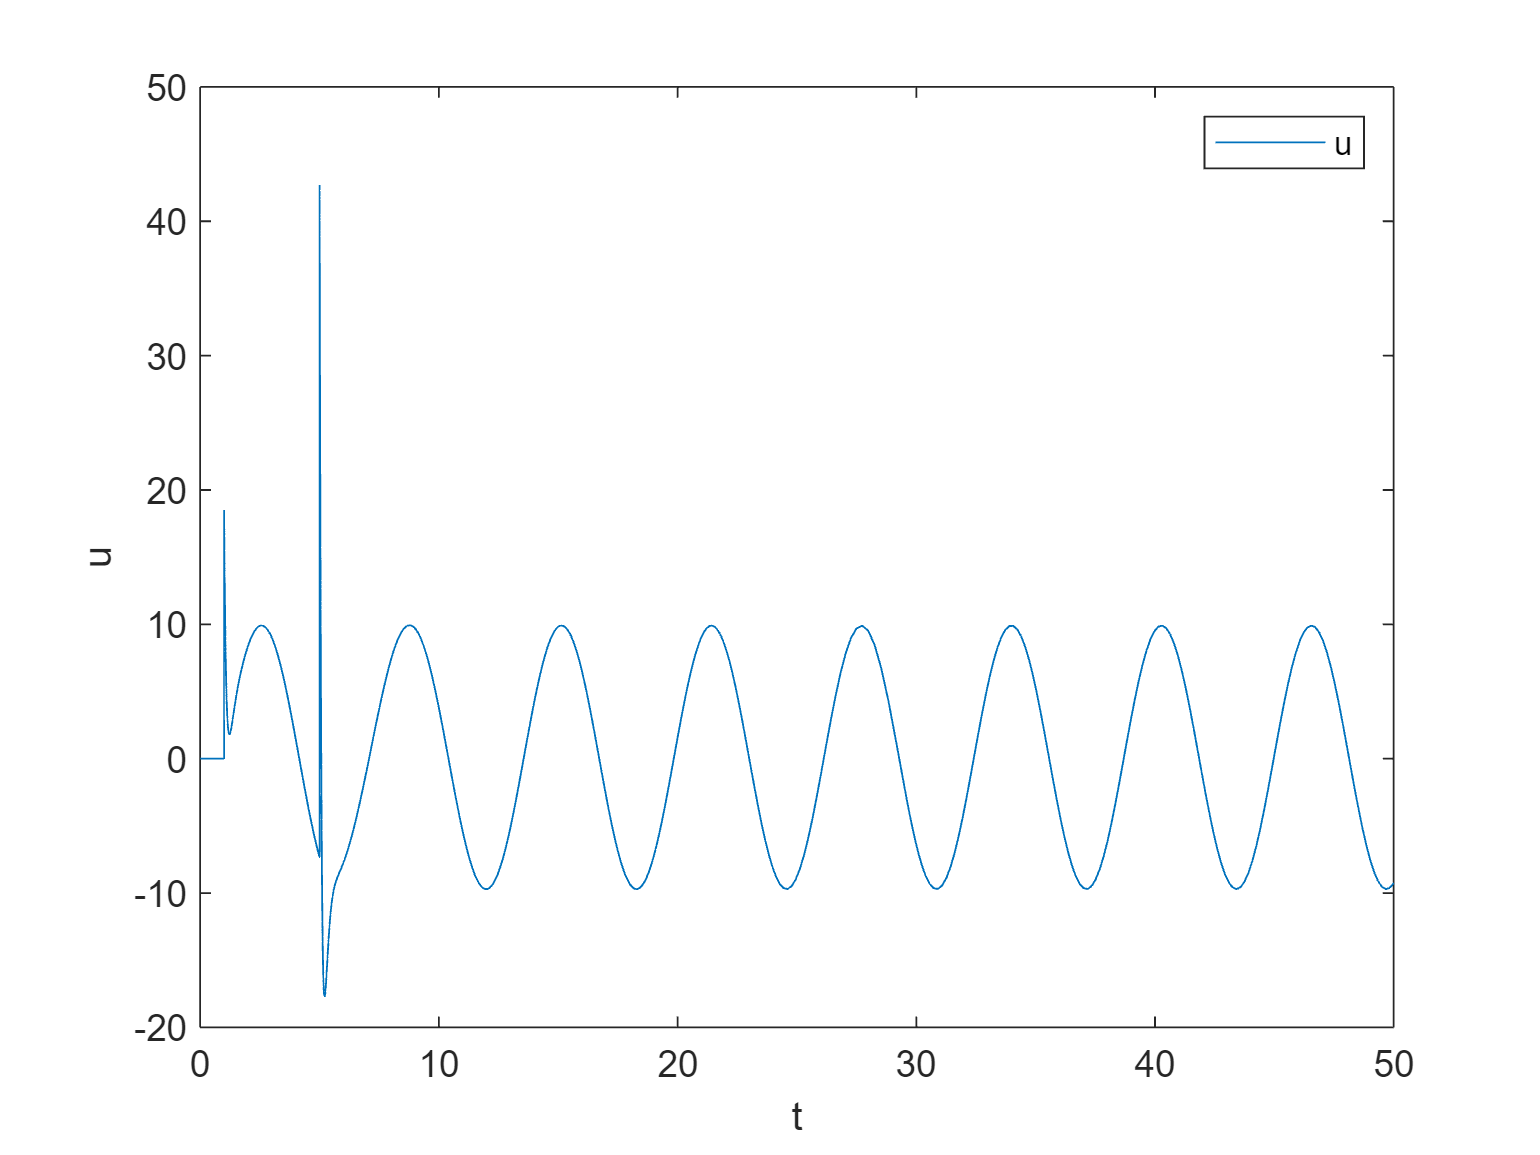

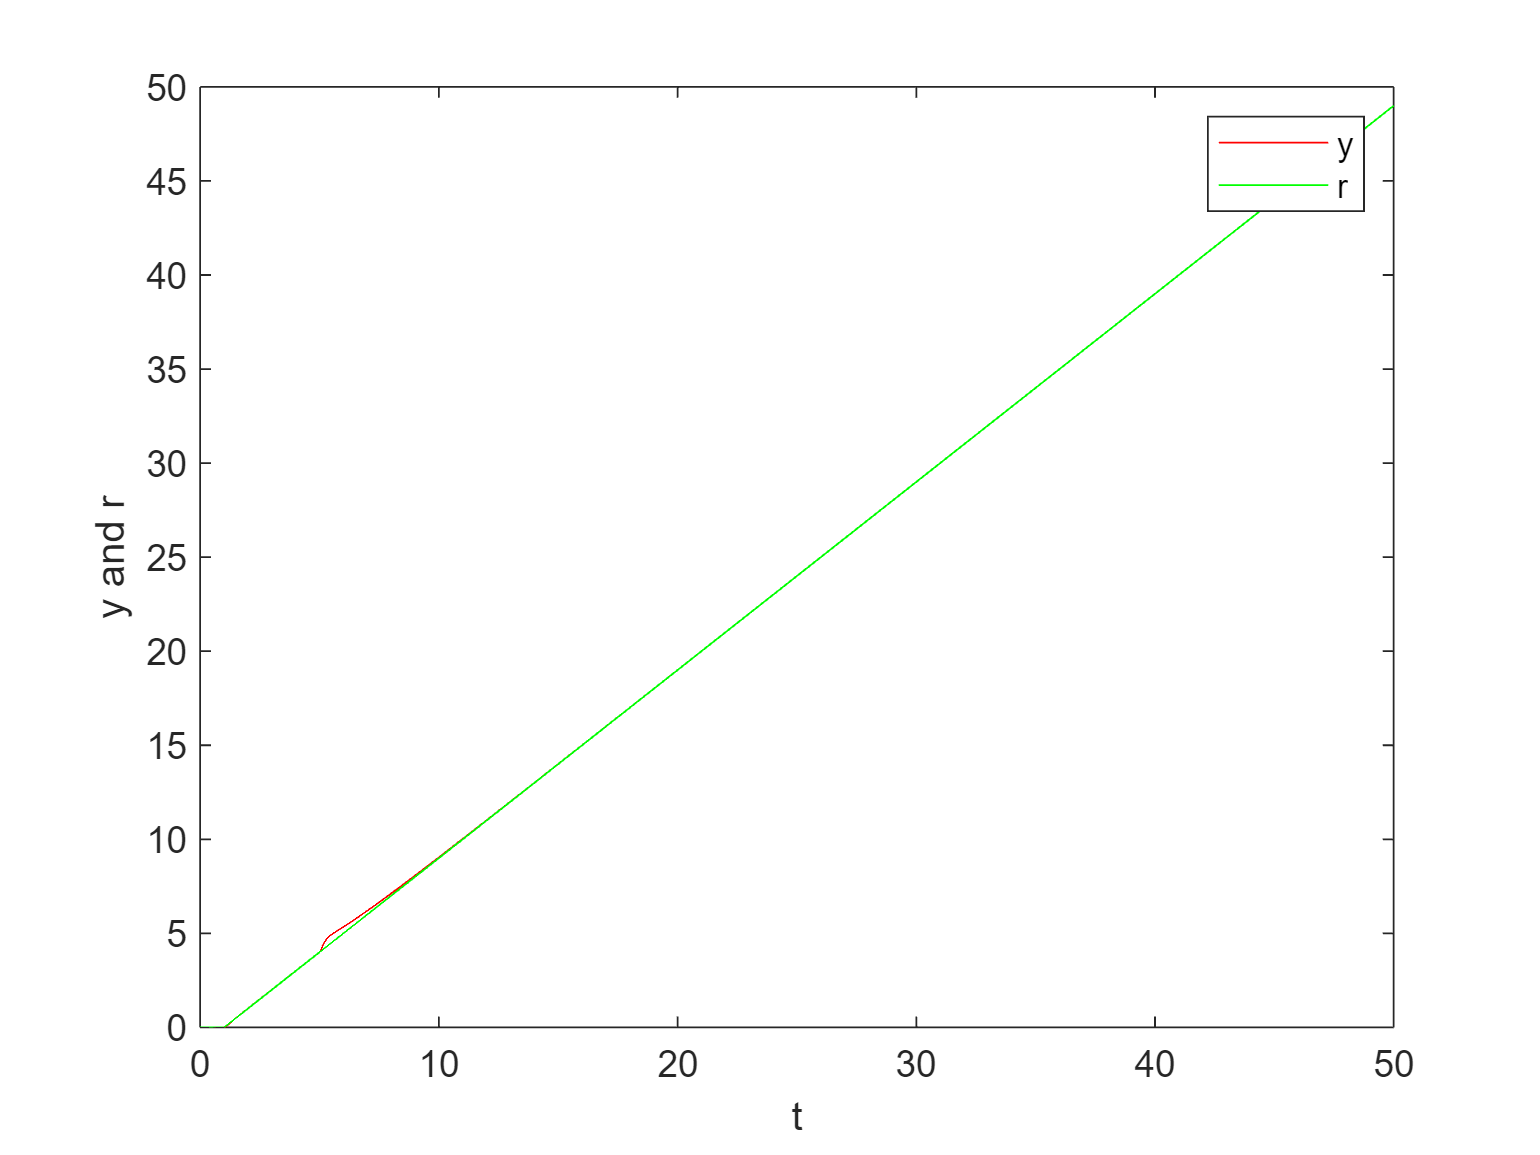

ki=50;
Disturbo=50;
simout=sim("FL_s_v_rampa_int.slx", 'SimulationMode', 'normal');
plotSimulationResults(simout,0)

 Facendo un parallelo con il miglior controllore trovato nel caso precedente, l'LQI, abbiamo prestazioni pressocchè simili, nel caso tempo invariante, con la differenza, però, che nel caso della feedback linearization riusciamo a garantire l'inseguimento di un segnale tempo variante. La tecnica, inoltre, dal punto di vista teorico è una delle più utilizzate per il controllo di sistemi meccanici di questo tipo, con dinamiche che variano molto velocemente come il pendolo, in cui i tempi di risposta devono essere rapidi e in cui la linearizzazione globale della feedback linearization esprime il suo maggior potenziale.